%data = load('SineWave{1}{6}.Values.Da');
t = SineWave{1}{6}.Values.Time;    % Time
omega = SineWave{1}{6}.Values.Data;
V = SineWave{1}{3}.Values.Data

V =          0
    0.0754
    0.1508
    0.2262
    0.3016
    0.3769
    0.4523
    0.5276
    0.6029
    0.6782


% 
% function omega_est = motor_model(params, t, V)
%     % Extract parameters
%     Rm = params(1);
%     Lm = params(2);
%     Ke = params(3);
%     Km = params(3)*params(6);
%     Jm = params(4);
%     Bm = params(5);
%     eta = params(6);
% 
%     s = tf('s'); 
% 
%     I_tf = 1 / (Lm * s + Rm);
% 
%     Omega_tf = (eta * Km * I_tf) / (Jm * s + Bm + Ke * Km / Rm);
% 
%     omega_est = lsim(Omega_tf, V, t);
% end


% function cost = cost_function(params, t, V, omega_measured)
%     omega_est = motor_model(params, t, V);
%     cost = double(sum((omega_measured - omega_est).^2)); % Ensure double type
% end
% 
% function cost = cost_function_nmse(params, t, V, omega_measured)
%     omega_est = motor_model(params, t, V);
%     cost = double(sum((omega_measured - omega_est).^2) / sum(omega_measured.^2));
% end
% 
% function cost = cost_function_absolute(params, t, V, omega_measured)
%     omega_est = motor_model(params, t, V);
%     cost = double(sum(abs(omega_measured - omega_est))); % Ensure double type
% end
% 


% Initial parameter guesses: [Rm, Lm, Ke, Km, Jm, Bm, eta]
params_init = [4.5, 0.004, 0.05, 0.001, 0.0001, 0.5];
% motor_Eff = 0.5;
% motor_Ke = 0.05;
% motor_J = 0.001;
% motor_B = 0.0001;

lb = [1e-09, 1e-09, 1e-09, 1e-09, 1e-09, 1e-09];  % Minimum bound for all
ub = [Inf, Inf, Inf, Inf, Inf, 1];  % Efficiency (eta) max is 1

% Optimize using `fmincon` for different cost functions
options = optimset('Display', 'iter', 'TolFun', 1e-9, 'TolX', 1e-9); % Tight convergence settings

% estimated_params = fmincon(@(p) cost_function(p, t, V, omega), params_init, [], [], [], [], lb, ub);
estimated_params_nmse = fmincon(@(p) cost_function_nmse(p, t, V, omega), params_init, [], [], [], [], lb, ub);

Not enough input arguments.

Error in estimate>cost_function_nmse (line 293)
    omega_est = motor_model(params, Rm, Lm, t, V);

Error in estimate>@(p)cost_function_nmse(p,t,V,omega) (line 55)
estimated_params_nmse = fmincon(@(p) cost_function_nmse(p, t, V, omega), params_init, [], [], [], [], lb, ub);

Er

% estimated_params_absolute = fmincon(@(p) cost_function_absolute(p, t, V, omega), params_init, [], [], [], [], lb, ub, [], options);

% Rm_hat = estimated_params(1);
% Lm_hat = estimated_params(2);
% Ke_hat = estimated_params(3);
% Km_hat = estimated_params(3)*estimated_params(6);
% Jm_hat = estimated_params(4);
% Bm_hat = estimated_params(5);
% eta_hat = estimated_params(6);
% 
% Rm_nmse = estimated_params_nmse(1);
% Lm_nmse = estimated_params_nmse(2);
% Ke_nmse = estimated_params_nmse(3);
% Km_nmse = estimated_params_nmse(3)*estimated_params_nmse(6);
% Jm_nmse = estimated_params_nmse(4);
% Bm_nmse = estimated_params_nmse(5);
% eta_nmse = estimated_params_nmse(6);
% Display results
% Extract parameters for Absolute Cost Function
Rm_abs = estimated_params_absolute(1);
Lm_abs = estimated_params_absolute(2);
Ke_abs = estimated_params_absolute(3);
Km_abs = estimated_params_absolute(3) * estimated_params_absolute(6);
Jm_abs = estimated_params_absolute(4);
Bm_abs = estimated_params_absolute(5);
eta_abs = estimated_params_absolute(6);

% Display results for Absolute Cost Function
fprintf('\nEstimated Parameters (Absolute Cost Function):\n');
fprintf('Rm = %.4f, Lm = %.6f, Ke = %.4f, Km = %.4f, Jm = %.6f, Bm = %.6f, Efficiency = %.2f%%\n', ...
    Rm_abs, Lm_abs, Ke_abs, Km_abs, Jm_abs, Bm_abs, eta_abs * 100);

fprintf('Estimated Parameters:\nRm = %.4f, Lm = %.6f, Ke = %.4f, Km = %.4f, Jm = %.6f, Bm = %.6f, Efficiency = %.2f%%\n', ...
    Rm_hat, Lm_hat, Ke_hat, Km_hat, Jm_hat, Bm_hat, eta_hat * 100);
fprintf('estimated_params_cost_function_nmse Parameters:\nRm = %.4f, Lm = %.6f, Ke = %.4f, Km = %.4f, Jm = %.6f, Bm = %.6f, Efficiency = %.2f%%\n', ...
    Rm_nmse, Lm_nmse, Ke_nmse, Km_nmse, Jm_nmse, Bm_nmse, eta_nmse * 100);


omega_sim = motor_model(estimated_params, t, V);

figure;
plot(t, omega, 'b', 'LineWidth', 1.5); hold on;
plot(t, omega_sim, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Motor Speed (rad/s)');
legend('Measured', 'Estimated');
title('Motor Parameter Estimation');
grid on;

x = omega;
y = omega_sim;



x = x(:);
y = y(:);

rmse = sqrt(mean((y - x).^2));
mae = mean(abs(y - x));

ss_total = sum((y - mean(y)).^2);
ss_residual = sum((y - x).^2);
r_squared = 1 - (ss_residual / ss_total);

correlation_coefficient = corr(x, y);

fprintf('RMSE: %.4f\n', rmse);
fprintf('MAE: %.4f\n', mae);
fprintf('R-squared: %.4f\n', r_squared);
fprintf('Correlation Coefficient (r): %.4f\n', correlation_coefficient);

t = double(SineWave{1}{6}.Values.Time);
omega = double(SineWave{1}{6}.Values.Data);
V = double(SineWave{1}{3}.Values.Data);

Rm_fixed = 2.51186;   % Fixed Motor Resistance
Lm_fixed = 0.0027645; % Fixed Motor Inductance

function omega_est = motor_model(params, Rm, Lm, t, V)
    Ke = params(1);    % Back-EMF Constant
    Jm = params(2);    % Moment of Inertia
    Bm = params(3);    % Friction Coefficient
    eta = params(4);   % Motor Efficiency

    Km = Ke * max(eta, 1e-6);  % Ensure eta is not zero

    t = t(:);
    V = V(:);

    % Check for time/input vector mismatch
    if length(t) ~= length(V)
        error('Time vector and input signal must have the same length!');
    end

    % Define the correct transfer function
    s = tf('s');
    Omega_tf = Km / ((Jm * s + Bm) * (Lm * s + Rm) + Ke * Km);

    Omega_ss = ss(Omega_tf);
    poles = pole(Omega_ss);
    disp('Poles of the system:');
    disp(poles);

    omega_est = lsim(Omega_ss, V, t);

    omega_est = double(omega_est);
end



%% Define Cost Functions (Optimizing 4 Parameters)
function cost = cost_function_SSE(params, Rm, Lm, t, V, omega_measured)
    omega_est = motor_model(params, Rm, Lm, t, V);
    
    % Compute Sum of Squared Errors (SSE)
    cost = sum((omega_measured - omega_est).^2);
end

params_init = [0.05, 0.001, 0.0001, 0.5];

lb = [1e-9, 1e-9, 1e-9, 0.01];  % Minimum bound for tunable parameters
ub = [Inf, Inf, Inf, 0.99];  % Efficiency max is 0.99 (avoid 1)

% Optimization Options
options = optimset('Display', 'iter', 'TolFun', 1e-9, 'TolX', 1e-9);

%% Run Optimization for SSE Cost Function
estimated_params_SSE = fmincon(@(p) cost_function_SSE(p, Rm_fixed, Lm_fixed, t, V, omega), ...
                               params_init, [], [], [], [], lb, ub, [], options);

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.759557e+08    0.000e+00    4.226e+09
Poles of the system:
   1.0e+02 *

  -4.6449 + 5.9218i
  -4.6449 - 5.9218i

Poles of the system:
   1.0e+02 *

  -4.6449 + 5.9218i
  -4.6449 - 5.9218i

Poles of the system:
   1.0e+02 *

  -4.6446 + 5.9078i
  -4.6446 - 5.9078i

Poles of the system:
   1.0e+02 *

  -4.6449 + 5.9218i
  -4.6449 - 5.9218i

Poles of the system:
   1.0e+02 *

  -4.6449 + 5.9218i
  -4.6449 - 5.9218i

    1      10    7.728084e+07    0.000e+00    2.374e+11    2.160e-01
Poles of the system:
 -850.8377
  -59.0498

Poles of the system:
 -850.8377
  -59.0498

Poles of the system:
 -850.8493
  -59.0380

Poles


% Debugging: Check size before assignment

% Assign parameters directly
Ke_hat  = estimated_params_SSE(1);
Jm_hat  = estimated_params_SSE(2);
Bm_hat  = estimated_params_SSE(3);
eta_hat = estimated_params_SSE(4);

% Compute Km while ensuring eta is not zero
Km_hat  = Ke_hat * max(eta_hat, 1e-6); % Avoid zero efficiency


%% Display Results
fprintf('Estimated Parameters (SSE Cost Function):\n');

Estimated Parameters (SSE Cost Function):


fprintf('Ke = %.10f, Km = %.10f, Jm = %.10f, Bm = %.10f, Efficiency = %.10f%%\n\n', ...
    Ke_hat, Km_hat, Jm_hat, Bm_hat, eta_hat * 100);

Ke = 0.0500313676, Km = 0.0495310195, Jm = 0.0001073164, Bm = 0.0000315843, Efficiency = 98.9999312357%




%% Simulate Model with Optimized Parameters
omega_sim = motor_model(estimated_params_SSE, Rm_fixed, Lm_fixed, t, V);

Poles of the system:
 -899.3217
   -9.5853



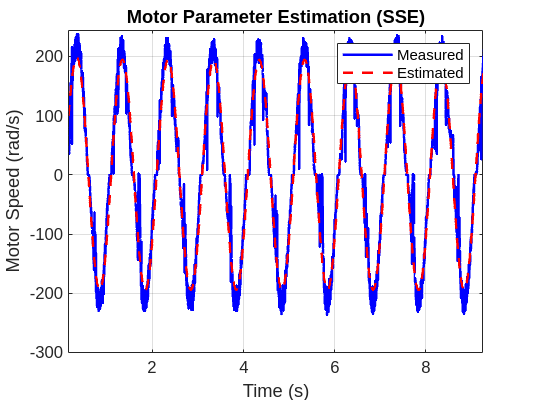


%% Plot Measured vs Estimated Response
figure;
plot(t, omega, 'b', 'LineWidth', 1.5); hold on;
plot(t, omega_sim, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Motor Speed (rad/s)');
legend('Measured', 'Estimated');
title('Motor Parameter Estimation (SSE)');
grid on;


%% Compute Performance Metrics
x = omega(:);
y = omega_sim(:);

rmse = sqrt(mean((y - x).^2));
mae = mean(abs(y - x));
r_squared = 1 - sum((y - x).^2) / sum((y - mean(y)).^2);
correlation_coefficient = corr(x, y);

% Display Performance Metrics
fprintf('Performance Metrics (SSE):\n');

Performance Metrics (SSE):


fprintf('RMSE: %.4f\n', rmse);

RMSE: 29.4059


fprintf('MAE: %.4f\n', mae);

MAE: 20.2409


fprintf('R-squared: %.4f\n', r_squared);

R-squared: 0.9544


fprintf('Correlation Coefficient (r): %.4f\n', correlation_coefficient);

Correlation Coefficient (r): 0.9783


## Load Data


t = double(SineWave{2}{6}.Values.Time);
omega = double(SineWave{2}{6}.Values.Data);
V = double(SineWave{1}{3}.Values.Data);

Rm_fixed = 2.51186;   % Fixed Motor Resistance
Lm_fixed = 0.0027645; % Fixed Motor Inductance



function cost = cost_function_absolute(params, Rm, Lm, t, V, omega_measured)
    omega_est = motor_model(params, Rm, Lm, t, V);
    cost = sum(abs(omega_measured - omega_est));
end

% Root Mean Square Error (RMSE) Cost Function
function cost = cost_function_rmse(params, Rm, Lm, t, V, omega_measured)
    omega_est = motor_model(params, Rm, Lm, t, V);
    N = length(omega_measured);
    cost = sqrt(sum((omega_measured - omega_est).^2) / N);
end

% Normalized Mean Squared Error (NMSE) Cost Function
function cost = cost_function_nmse(params, Rm, Lm, t, V, omega_measured)
    omega_est = motor_model(params, Rm, Lm, t, V);
    cost = sum((omega_measured - omega_est).^2) / sum(omega_measured.^2);
end

%% Optimization Setup (Only 4 Parameters)
params_init = [0.05, 0.001, 0.0001, 0.5];

% Define Lower & Upper Bounds (Only 4 Parameters)
lb = [1e-9, 1e-9, 1e-9, 0.01];  % Minimum bound for tunable parameters
ub = [Inf, Inf, Inf, 0.99];  % Efficiency max is 0.99 (avoid 1)

% Optimization Options
options = optimset('Display', 'iter', 'TolFun', 1e-9, 'TolX', 1e-9);

%% Run Optimization for Different Cost Functions
estimated_params_SSE = fmincon(@(p) cost_function_SSE(p, Rm_fixed, Lm_fixed, t, V, omega), ...
                               params_init, [], [], [], [], lb, ub, [], options);

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.759557e+08    0.000e+00    4.226e+09
Poles of the system:
   1.0e+02 *

  -4.6449 + 5.9218i
  -4.6449 - 5.9218i

Poles of the system:
   1.0e+02 *

  -4.6449 + 5.9218i
  -4.6449 - 5.9218i

Poles of the system:
   1.0e+02 *

  -4.6446 + 5.9078i
  -4.6446 - 5.9078i

Poles of the system:
   1.0e+02 *

  -4.6449 + 5.9218i
  -4.6449 - 5.9218i

Poles of the system:
   1.0e+02 *

  -4.6449 + 5.9218i
  -4.6449 - 5.9218i

    1      10    7.728084e+07    0.000e+00    2.374e+11    2.160e-01
Poles of the system:
 -850.8377
  -59.0498

Poles of the system:
 -850.8377
  -59.0498

Poles of the system:
 -850.8493
  -59.0380

Poles

estimated_params_abs = fmincon(@(p) cost_function_absolute(p, Rm_fixed, Lm_fixed, t, V, omega), ...
                               params_init, [], [], [], [], lb, ub, [], options);

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.133405e+06    0.000e+00    1.545e+07
Poles of the system:
   1.0e+02 *

  -4.6454 + 6.0069i
  -4.6454 - 6.0069i

Poles of the system:
   1.0e+02 *

  -4.6454 + 6.0069i
  -4.6454 - 6.0069i

Poles of the system:
   1.0e+02 *

  -4.6451 + 5.9929i
  -4.6451 - 5.9929i

Poles of the system:
   1.0e+02 *

  -4.6454 + 6.0069i
  -4.6454 - 6.0069i

Poles of the system:
   1.0e+02 *

  -4.6454 + 6.0069i
  -4.6454 - 6.0069i

    1      10    7.914622e+05    0.000e+00    1.298e+09    2.152e-01
Poles of the system:
 -746.9522
 -164.8166

Poles of the system:
 -746.9521
 -164.8166

Poles of the system:
 -747.0474
 -164.7199

Poles

estimated_params_rmse = fmincon(@(p) cost_function_rmse(p, Rm_fixed, Lm_fixed, t, V, omega), ...
                               params_init, [], [], [], [], lb, ub, [], options);

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.326417e+02    0.000e+00    1.593e+03
Poles of the system:
   1.0e+03 *

  -0.4545 + 1.8721i
  -0.4545 - 1.8721i

Poles of the system:
   1.0e+02 *

  -4.5442 + 5.3414i
  -4.5442 - 5.3414i

Poles of the system:
 -786.4696
 -122.2940

Poles of the system:
 -786.4696
 -122.2940

Poles of the system:
 -786.4720
 -122.2915

Poles of the system:
 -786.4696
 -122.2940

Poles of the system:
 -786.4696
 -122.2940

    1      12    1.292376e+02    0.000e+00    8.977e+03    5.750e-01
Poles of the system:
 -801.2902
 -107.6035

Poles of the system:
 -801.2902
 -107.6035

Poles of the system:
 -801.2924
 -107.6013

Poles of the 

estimated_params_nmse = fmincon(@(p) cost_function_nmse(p, Rm_fixed, Lm_fixed, t, V, omega), ...
                               params_init, [], [], [], [], lb, ub, [], options);

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    8.881430e-01    0.000e+00    2.133e+01
Poles of the system:
 -901.4423
   -7.4011

Poles of the system:
 -901.4423
   -7.4011

Poles of the system:
 -901.4425
   -7.4010

Poles of the system:
 -901.4423
   -7.4011

Poles of the system:
 -901.4423
   -7.4011

    1      10    5.328430e-01    0.000e+00    1.072e+02    1.635e-01
Poles of the system:
   1.0e+03 *

  -0.4930 + 1.7725i
  -0.4930 - 1.7725i

Poles of the system:
 -884.3981
  -24.8291

Poles of the system:
 -896.0841
  -12.8877

Poles of the system:
 -896.0841
  -12.8877

Poles of the system:
 -896.0844
  -12.8874

Poles of the system:
 -896.0841
  -12.8877

P

Poles of the system:
   1.0e+03 *

  -0.4557 + 2.7513i
  -0.4557 - 2.7513i



Poles of the system:
   1.0e+03 *

  -0.4557 + 2.7513i
  -0.4557 - 2.7513i



Poles of the system:
   1.0e+03 *

  -0.4557 + 2.7513i
  -0.4557 - 2.7513i



Poles of the system:
   1.0e+03 *

  -0.4557 + 2.7513i
  -0.4557 - 2.7513i



   19     102    9.997847e-01    0.000e+00    1.038e-01    2.464e+02
Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0559i
  -0.4557 - 3.0559i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0559i
  -0.4557 - 3.0559i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0559i
  -0.4557 - 3.0559i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0559i
  -0.4557 - 3.0559i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0559i
  -0.4557 - 3.0559i



   20     107    9.998218e-01    0.000e+00    2.574e-02    9.514e+01
Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0713i
  -0.4557 - 3.0713i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0713i
  -0.4557 - 3.0713i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0713i
  -0.4557 - 3.0713i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0713i
  -0.4557 - 3.0713i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0713i
  -0.4557 - 3.0713i



   21     112    9.998234e-01    0.000e+00    3.499e-04    5.223e+00
Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0349i
  -0.4557 - 3.0349i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0349i
  -0.4557 - 3.0349i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0349i
  -0.4557 - 3.0349i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0349i
  -0.4557 - 3.0349i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0349i
  -0.4557 - 3.0349i



   22     117    9.998130e-01    0.000e+00    3.981e-05    3.120e+01
Poles of the system:
   1.0e+03 *

  -0.4557 + 3.3448i
  -0.4557 - 3.3448i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.3448i
  -0.4557 - 3.3448i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.3448i
  -0.4557 - 3.3448i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.3448i
  -0.4557 - 3.3448i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.3448i
  -0.4557 - 3.3448i



   23     122    9.996729e-01    0.000e+00    3.984e-05    2.257e+02
Poles of the system:
   1.0e+03 *

  -0.4557 + 1.2835i
  -0.4557 - 1.2835i

Poles of the system:
   1.0e+03 *

  -0.4557 + 1.2835i
  -0.4557 - 1.2835i

Poles of the system:
   1.0e+03 *

  -0.4557 + 1.2835i
  -0.4557 - 1.2835i

Poles of the system:
   1.0e+03 *

  -0.4557 + 1.2835i
  -0.4557 - 1.2835i

Poles of the system:
   1.0e+03 *

  -0.4557 + 1.2835i
  -0.4557 - 1.2835i

   24     127    9.980219e-01    0.000e+00    4.115e-05    2.515e+02
Poles of the system:
 -897.1163
  -14.0911

Poles of the system:
 -897.1163
  -14.0911

Poles of the system:
 -897.1164
  -14.0910

Poles of the system:
 -897.1163
  -14.0911

Poles of the system:
 -897.1163
  -14.0911

   25     132    7.101757e-01    0.000e+00    9.766e+00    4.955e+01
Poles of the system:
 -907.4505
   -1.3130

Poles of the system:
 -907.4505
   -1.3130

Poles of the system:
 -907.4506
   -1.3129

Poles of the system:
 -907.4505
   -1.3131

Poles of the syst


%% Extract Estimated Parameters
% Standard Cost Function (SSE)
Ke_SSE  = estimated_params_SSE(1);
Jm_SSE  = estimated_params_SSE(2);
Bm_SSE  = estimated_params_SSE(3);
eta_SSE = estimated_params_SSE(4);
Km_SSE  = Ke_SSE * max(eta_SSE, 1e-6);

% Absolute Error Cost Function
Ke_abs  = estimated_params_abs(1);
Jm_abs  = estimated_params_abs(2);
Bm_abs  = estimated_params_abs(3);
eta_abs = estimated_params_abs(4);
Km_abs  = Ke_abs * max(eta_abs, 1e-6);

% RMSE Cost Function
Ke_rmse  = estimated_params_rmse(1);
Jm_rmse  = estimated_params_rmse(2);
Bm_rmse  = estimated_params_rmse(3);
eta_rmse = estimated_params_rmse(4);
Km_rmse  = Ke_rmse * max(eta_rmse, 1e-6);

% NMSE Cost Function
Ke_nmse  = estimated_params_nmse(1);
Jm_nmse  = estimated_params_nmse(2);
Bm_nmse  = estimated_params_nmse(3);
eta_nmse = estimated_params_nmse(4);
Km_nmse  = Ke_nmse * max(eta_nmse, 1e-6);

%% Display Results
fprintf('Estimated Parameters (SSE):\n');

Estimated Parameters (SSE):


fprintf('Ke = %.10f, Km = %10f, Jm = %.10f, Bm = %.10f, Efficiency = %.10f%%\n\n', ...
    Ke_SSE, Km_SSE, Jm_SSE, Bm_SSE, eta_SSE * 100);

Ke = 0.0500313676, Km =   0.049531, Jm = 0.0001073164, Bm = 0.0000315843, Efficiency = 98.9999312357%




fprintf('Estimated Parameters (Absolute Error):\n');

Estimated Parameters (Absolute Error):


fprintf('Ke = %.10f, Km = %10f, Jm = %.10f, Bm = %.10f, Efficiency = %.10f%%\n\n', ...
    Ke_abs, Km_abs, Jm_abs, Bm_abs, eta_abs * 100);

Ke = 0.0498783812, Km =   0.049379, Jm = 0.0000984768, Bm = 0.0000087924, Efficiency = 98.9992992914%




fprintf('Estimated Parameters (RMSE):\n');

Estimated Parameters (RMSE):


fprintf('Ke = %.10f, Km = %10f, Jm = %.10f, Bm = %.10f, Efficiency = %.10f%%\n\n', ...
    Ke_rmse, Km_rmse, Jm_rmse, Bm_rmse, eta_rmse * 100);

Ke = 0.0494768449, Km =   0.036854, Jm = 0.0000798404, Bm = 0.0000316491, Efficiency = 74.4877388399%




fprintf('Estimated Parameters (NMSE):\n');

Estimated Parameters (NMSE):


fprintf('Ke = %.10f, Km = %10f, Jm = %.10f, Bm = %.10f, Efficiency = %.2f%%\n\n', ...
    Ke_nmse, Km_nmse, Jm_nmse, Bm_nmse, eta_nmse * 100);

Ke = 0.0491296822, Km =   0.041531, Jm = 0.0000899672, Bm = 0.0000414104, Efficiency = 84.53%




resultsTable1 = table(Ke_SSE, Jm_SSE, Bm_SSE, eta_SSE,Ke_abs, Jm_abs, Bm_abs, eta_abs,Ke_rmse, Jm_rmse, Bm_rmse, eta_rmse,Ke_nmse, Jm_nmse, Bm_nmse, eta_nmse);
omega_sim = motor_model(estimated_params_SSE, Rm_fixed, Lm_fixed, t, V);

Poles of the system:
 -899.3217
   -9.5853



disp(resultsTable1)

     Ke_SSE       Jm_SSE        Bm_SSE      eta_SSE     Ke_abs       Jm_abs        Bm_abs      eta_abs    Ke_rmse      Jm_rmse      Bm_rmse      eta_rmse    Ke_nmse     Jm_nmse       Bm_nmse     eta_nmse
    ________    __________    __________    _______    ________    __________    __________    _______    ________    _________    __________    ________    _______    __________    _________    ________

    0.050031    0.00010732    3.1584e-05     0.

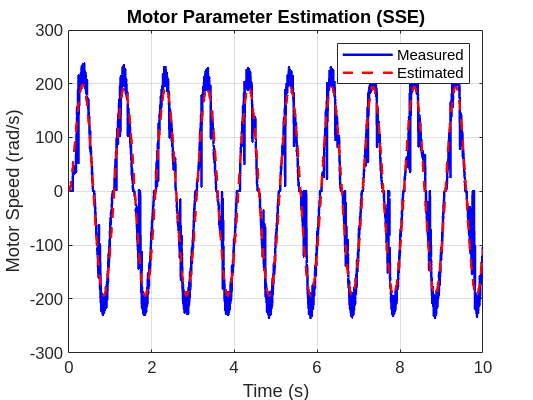

figure;
plot(t, omega, 'b', 'LineWidth', 1.5); hold on;
plot(t, omega_sim, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Motor Speed (rad/s)');
legend('Measured', 'Estimated');
title('Motor Parameter Estimation (SSE)');
grid on;

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    2.256891e+01    0.000e+00    2.790e+02
Poles of the system:
   1.0e+02 *

  -4.5469 + 5.8325i
  -4.5469 - 5.8325i

Poles of the system:
 -849.9516
  -58.9005

Poles of the system:
 -849.9516
  -58.9005

Poles of the system:
 -849.9531
  -58.8990

Poles of the system:
 -849.9516
  -58.9005

Poles of the system:
 -849.9516
  -58.9005

    1      11    2.219140e+01    0.000e+00    1.338e+03    3.804e-01
Poles of the system:
 -866.1182
  -42.8915

Poles of the system:
 -866.1182
  -42.8915

Poles of the system:
 -866.1192
  -42.8904

Poles of the system:
 -866.1182
  -42.8915

Poles of the system:
 -866.1182
  -42.8915

 

Poles of the system:
 -901.5200
   -9.5547



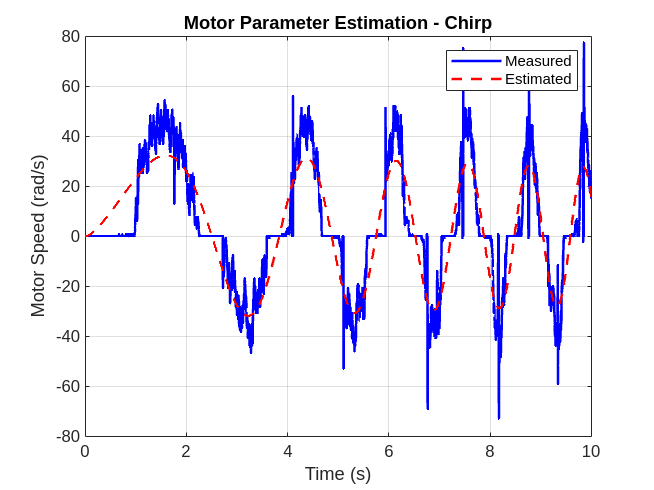

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    7.915789e+01    0.000e+00    2.723e+02
Poles of the system:
   1.0e+02 *

  -4.5462 + 5.7621i
  -4.5462 - 5.7621i

Poles of the system:
 -842.8019
  -66.0346

Poles of the system:
 -842.8019
  -66.0346

Poles of the system:
 -842.8036
  -66.0330

Poles of the system:
 -842.8019
  -66.0346

Poles of the system:
 -842.8019
  -66.0346

    1      11    7.885083e+01    0.000e+00    1.606e+03    4.004e-01
Poles of the system:
 -857.8905
  -51.1008

Poles of the system:
 -857.8905
  -51.1008

Poles of the system:
 -857.8917
  -51.0995

Poles of the system:
 -857.8905
  -51.1008

Poles of the system:
 -857.8905
  -51.1008

 

Poles of the system:
   1.0e+03 *

  -0.4931 + 7.0724i
  -0.4931 - 7.0724i



Poles of the system:
   1.0e+03 *

  -0.4795 + 5.6945i
  -0.4795 - 5.6945i



Poles of the system:
   1.0e+03 *

  -0.4934 + 7.0724i
  -0.4934 - 7.0724i



Poles of the system:
   1.0e+03 *

  -0.4931 + 7.0724i
  -0.4931 - 7.0724i



    9      60    7.051501e+01    0.000e+00    9.370e+03    1.752e-02
Poles of the system:
   1.0e+03 *

  -0.4545 + 6.4328i
  -0.4545 - 6.4328i



Poles of the system:
   1.0e+03 *

  -0.4545 + 6.4328i
  -0.4545 - 6.4328i



Poles of the system:
   1.0e+03 *

  -0.4544 + 5.1735i
  -0.4544 - 5.1735i



Poles of the system:
   1.0e+03 *

  -0.4548 + 6.4328i
  -0.4548 - 6.4328i



Poles of the system:
   1.0e+03 *

  -0.4545 + 6.4328i
  -0.4545 - 6.4328i



   10      65    6.949344e+01    0.000e+00    1.425e+04    5.743e-03
Poles of the system:
 -907.7112
   -1.1567

Poles of the system:
   1.0e+03 *

  -0.4545 + 3.0070i
  -0.4545 - 3.0070i



Poles of the system:
   1.0e+03 *

  -0.4545 + 3.0070i
  -0.4545 - 3.0070i



Poles of the system:
   1.0e+03 *

  -0.4544 + 2.4606i
  -0.4544 - 2.4606i



Poles of the system:
   1.0e+03 *

  -0.4547 + 3.0070i
  -0.4547 - 3.0070i



Poles of the system:
   1.0e+03 *

  -0.4545 + 3.0070i
  -0.4545 - 3.0070i



   11      71    5.897573e+01    0.000e+00    1.438e+05    2.813e-02
Poles of the system:
 -908.4969
   -0.2363

Poles of the system:
   1.0e+03 *

  -0.4544 + 1.1200i
  -0.4544 - 1.1200i

Poles of the system:
   1.0e+03 *

  -0.4544 + 1.1200i
  -0.4544 - 1.1200i

Poles of the system:
   1.0e+02 *

  -4.5438 + 9.5844i
  -4.5438 - 9.5844i

Poles of the system:
   1.0e+03 *

  -0.4545 + 1.1200i
  -0.4545 - 1.1200i

Poles of the system:
   1.0e+03 *

  -0.4544 + 1.1200i
  -0.4544 - 1.1200i

   12      77    4.096281e+01    0.000e+00    1.601e+06    1.413e-02
Poles of the system:
 -908.6087
   -0.0181

Poles of the system:
 -826.6665
  -81.9761

Poles of the system:
 -826.6661
  -81.9765

Poles of the system:
 -831.3640
  -77.2770

Poles of the system:
 -826.6605
  -82.0370

Poles of the system:
 -826.6665
  -81.9761

   13      83    3.719683e+01    0.000e+00    1.252e+07    7.102e-03
Poles of the system:
 -908.6127
   -0.0011

Poles of the system:
 -907.0836
   -1.5313

Poles of the syst

Poles of the system:
 -898.6129
  -10.2937



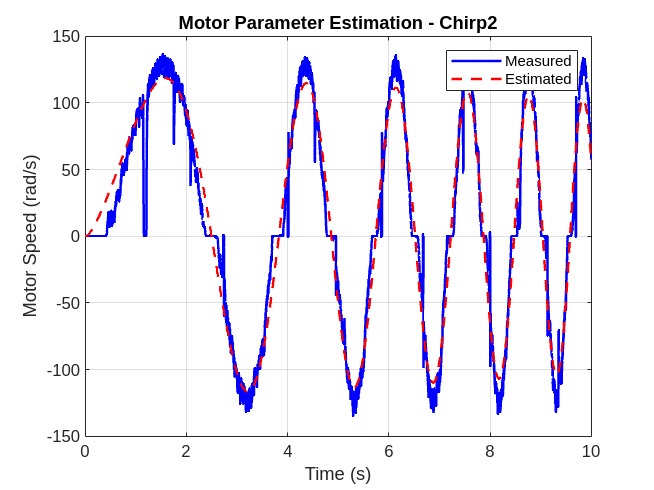

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.375148e+02    0.000e+00    2.474e+02
Poles of the system:
   1.0e+02 *

  -4.5460 + 5.7347i
  -4.5460 - 5.7347i

Poles of the system:
 -841.8464
  -66.9862

Poles of the system:
 -841.8464
  -66.9862

Poles of the system:
 -841.8481
  -66.9846

Poles of the system:
 -841.8464
  -66.9863

Poles of the system:
 -841.8464
  -66.9862

    1      11    1.372443e+02    0.000e+00    1.661e+03    4.033e-01
Poles of the system:
 -856.6198
  -52.3667

Poles of the system:
 -856.6198
  -52.3667

Poles of the system:
 -856.6210
  -52.3655

Poles of the system:
 -856.6198
  -52.3667

Poles of the system:
 -856.6198
  -52.3667

 

Poles of the system:
 -898.8715
  -10.3047



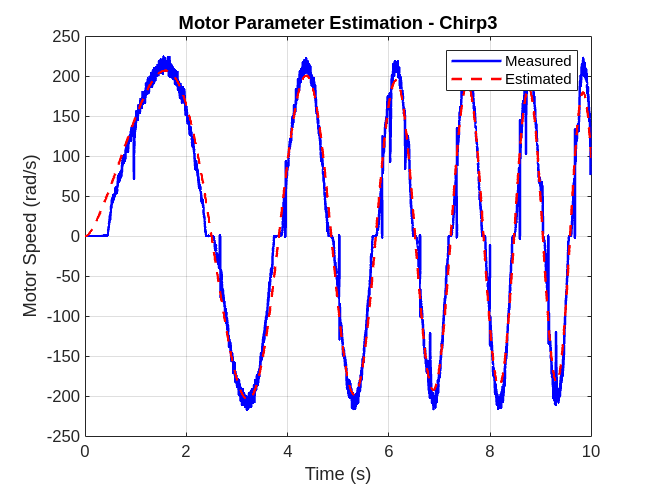

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    2.994193e+01    0.000e+00    1.456e+04
Poles of the system:
   1.0e+03 *

  -0.4552 + 2.9234i
  -0.4552 - 2.9234i



Poles of the system:
   1.0e+02 *

  -4.5464 + 9.5419i
  -4.5464 - 9.5419i

Poles of the system:
   1.0e+02 *

  -4.5448 + 0.6791i
  -4.5448 - 0.6791i

Poles of the system:
 -850.5789
  -58.2478

Poles of the system:
 -820.8204
  -89.7785

Poles of the system:
 -904.8953
   -3.9243

Poles of the system:
 -907.1910
   -1.5588

Poles of the system:
 -907.1910
   -1.5588

Poles of the system:
 -907.1910
   -1.5588

Poles of the system:
 -907.1910
   -1.5588

Poles of the system:
 -907.1910
   -1.5588

    1      16    2.714282e+01    0.000e+00    7.082e+00    4.639e-02
Poles of the system:
 -902.4600
   -6.4441

Poles of the system:
 -902.4600
   -6.4441

Poles of the system:
 -902.4603
   -6.4438

Poles of the system:
 -902.4600
   -6.4441

Poles of the system:
 -902.4600
   -6.4441

    2      21    2.015160e+01    0.000e+00    7.379e+03    4.464e-01
Poles of the system:
 -908.1954
   -1.3468

Poles of the system:
 -905.5707
   -3.4939

Poles of the system:
 -904.0418
   -4.9266

Poles 

Poles of the system:
 -853.5286
  -56.1569



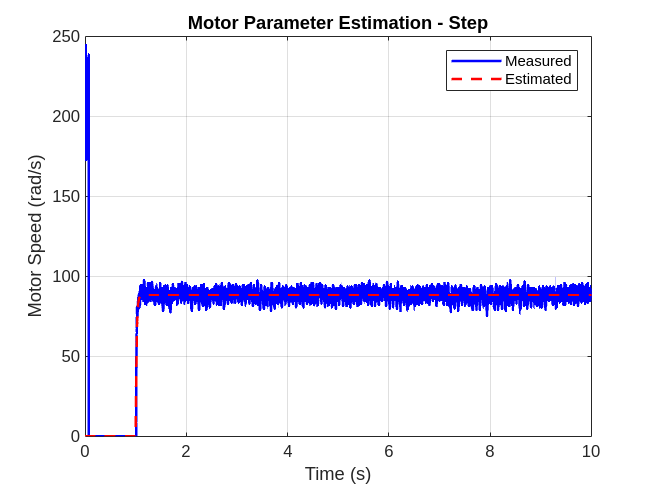

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    4.382463e+01    0.000e+00    1.375e+02
Poles of the system:
   1.0e+03 *

  -0.4544 + 1.2206i
  -0.4544 - 1.2206i

Poles of the system:
   1.0e+02 *

  -4.5436 + 1.7701i
  -4.5436 - 1.7701i

Poles of the system:
 -851.5347
  -57.1780

Poles of the system:
 -894.3261
  -14.3867

Poles of the system:
 -872.4731
  -36.1852

Poles of the system:
   1.0e+02 *

  -4.6247 + 2.2550i
  -4.6247 - 2.2550i

Poles of the system:
   1.0e+02 *

  -4.6247 + 2.2550i
  -4.6247 - 2.2550i

Poles of the system:
   1.0e+02 *

  -4.6245 + 2.2380i
  -4.6245 - 2.2380i

Poles of the system:
   1.0e+02 *

  -4.6247 + 2.2551i
  -4.6247 - 2.2551i

Poles of the system:
 -862.6293
  -46.1317



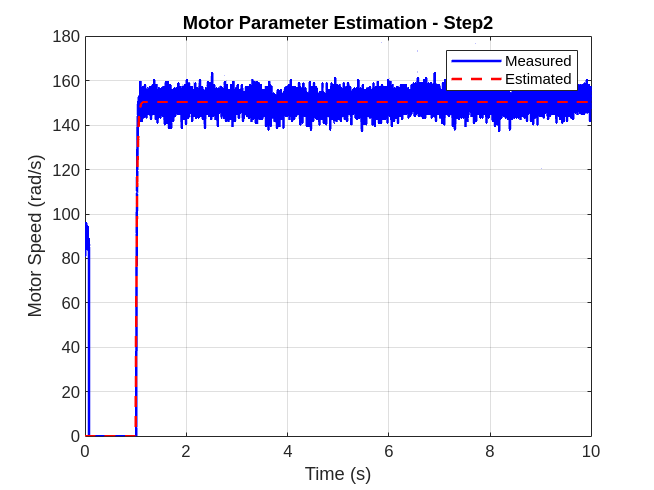

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    4.758299e+01    0.000e+00    1.405e+05
Poles of the system:
   1.0e+03 *

  -0.4605 + 1.1188i
  -0.4605 - 1.1188i

Poles of the system:
   1.0e+03 *

  -0.4565 + 2.2790i
  -0.4565 - 2.2790i



Poles of the system:
   1.0e+03 *

  -0.4553 + 1.2510i
  -0.4553 - 1.2510i

Poles of the system:
   1.0e+02 *

  -4.5481 + 5.4076i
  -4.5481 - 5.4076i

Poles of the system:
 -904.9972
   -3.7692

Poles of the system:
 -906.8394
   -1.8996

Poles of the system:
 -906.8394
   -1.8996

Poles of the system:
 -906.8394
   -1.8996

Poles of the system:
 -906.8394
   -1.8996

Poles of the system:
 -906.8394
   -1.8996

    1      15    4.439716e+01    0.000e+00    1.953e+01    6.652e-02
Poles of the system:
 -895.8933
  -13.3529

Poles of the system:
 -895.8933
  -13.3529

Poles of the system:
 -895.8940
  -13.3522

Poles of the system:
 -895.8933
  -13.3530

Poles of the system:
 -895.8933
  -13.3529

    2      20    3.111846e+01    0.000e+00    1.372e+04    5.334e-01
Poles of the system:
 -896.6073
  -12.2414

Poles of the system:
 -896.6073
  -12.2414

Poles of the system:
 -896.6082
  -12.2404

Poles of the system:
 -896.6073
  -12.2415

Poles of the system:
 -896.6073
  -12.2414

    3 

Poles of the system:
 -862.5356
  -46.1253



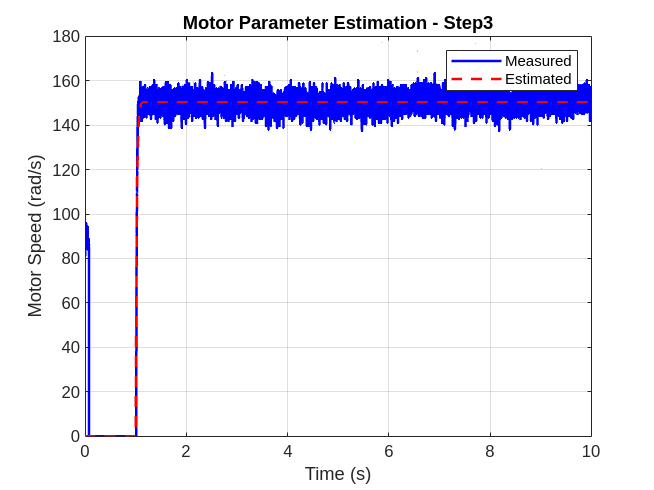

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    3.243812e+01    0.000e+00    3.176e+01
Poles of the system:
 -908.0835
   -0.6293

Poles of the system:
 -908.0430
   -0.6697

Poles of the system:
 -908.0430
   -0.6697

Poles of the system:
 -908.0431
   -0.6697

Poles of the system:
 -908.0430
   -0.6697

Poles of the system:
 -908.0430
   -0.6697

    1      11    1.891085e+01    0.000e+00    1.402e+05    2.440e-01
Poles of the system:
 -907.8296
   -0.8799

Poles of the system:
 -907.9384
   -0.7726

Poles of the system:
 -907.9384
   -0.7726

Poles of the system:
 -907.9384
   -0.7726

Poles of the system:
 -907.9384
   -0.7726

Poles of the system:
 -907.9384
 

Poles of the system:
 -908.1619
   -0.5700



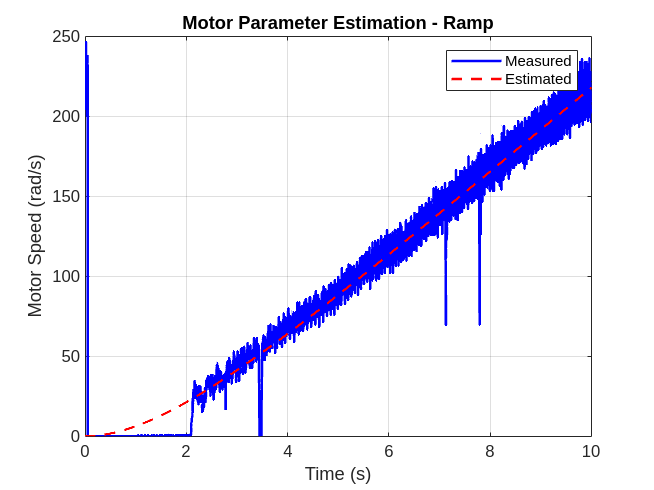

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    4.686910e+01    0.000e+00    4.775e+01
Poles of the system:
 -908.0783
   -0.6344

Poles of the system:
 -908.0411
   -0.6717

Poles of the system:
 -908.0411
   -0.6717

Poles of the system:
 -908.0411
   -0.6717

Poles of the system:
 -908.0411
   -0.6717

Poles of the system:
 -908.0411
   -0.6717

    1      11    3.269237e+01    0.000e+00    2.681e+05    2.440e-01
Poles of the system:
 -900.2680
   -8.5561

Poles of the system:
 -906.3528
   -2.3916

Poles of the system:
 -906.3528
   -2.3916

Poles of the system:
 -906.3528
   -2.3915

Poles of the system:
 -906.3528
   -2.3916

Poles of the system:
 -906.3528
 

Poles of the system:
 -906.1547
   -2.7315



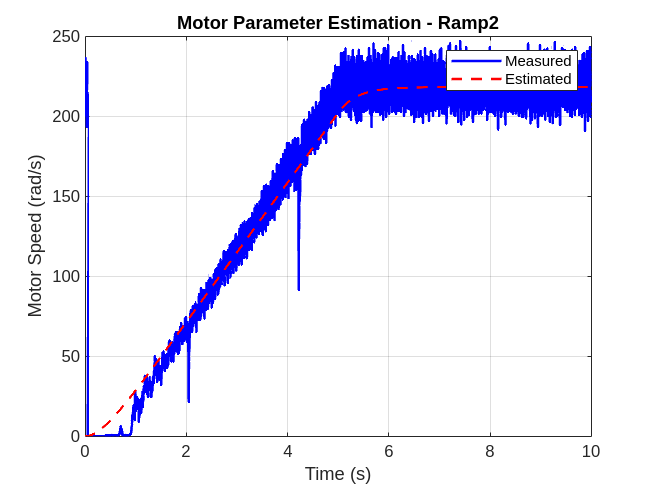

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    6.181049e+01    0.000e+00    4.813e+01
Poles of the system:
 -908.0779
   -0.6348

Poles of the system:
 -908.0410
   -0.6718

Poles of the system:
 -908.0410
   -0.6718

Poles of the system:
 -908.0410
   -0.6718

Poles of the system:
 -908.0410
   -0.6718

Poles of the system:
 -908.0410
   -0.6718

    1      11    5.388533e+01    0.000e+00    3.062e+05    2.440e-01
Poles of the system:
 -902.8764
   -5.8726

Poles of the system:
 -902.8764
   -5.8726

Poles of the system:
 -902.8767
   -5.8724

Poles of the system:
 -902.8764
   -5.8727

Poles of the system:
 -902.8764
   -5.8726

    2      16    5.067620e+01    

Poles of the system:
 -901.3213
   -7.2982



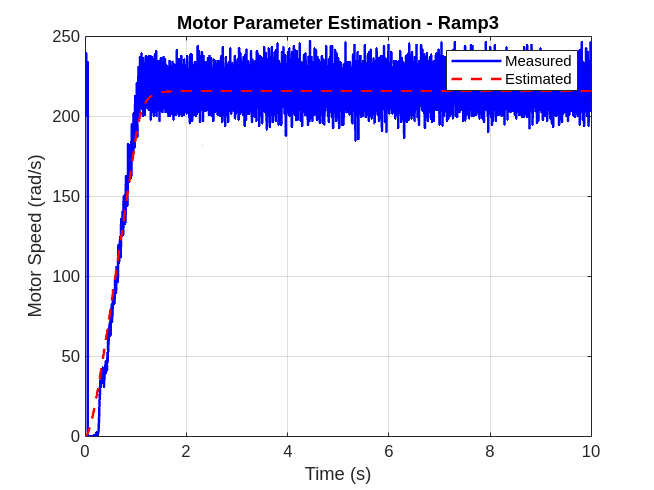

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.326417e+02    0.000e+00    1.593e+03
Poles of the system:
   1.0e+03 *

  -0.4545 + 1.8721i
  -0.4545 - 1.8721i

Poles of the system:
   1.0e+02 *

  -4.5442 + 5.3414i
  -4.5442 - 5.3414i

Poles of the system:
 -786.4696
 -122.2940

Poles of the system:
 -786.4696
 -122.2940

Poles of the system:
 -786.4720
 -122.2915

Poles of the system:
 -786.4696
 -122.2940

Poles of the system:
 -786.4696
 -122.2940

    1      12    1.292376e+02    0.000e+00    8.977e+03    5.750e-01
Poles of the system:
 -801.2902
 -107.6035

Poles of the system:
 -801.2902
 -107.6035

Poles of the system:
 -801.2924
 -107.6013

Poles of the 

Poles of the system:
 -899.4236
   -9.5856



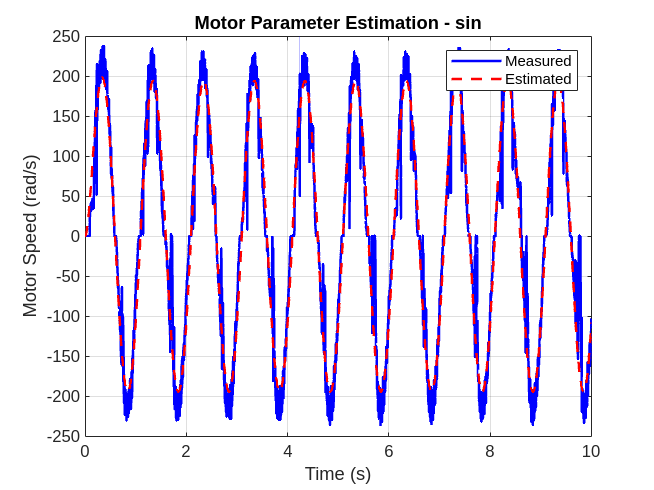

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.336412e+02    0.000e+00    2.881e+02
Poles of the system:
   1.0e+03 *

  -0.4544 + 1.2963i
  -0.4544 - 1.2963i

Poles of the system:
   1.0e+02 *

  -4.5438 + 1.9761i
  -4.5438 - 1.9761i

Poles of the system:
 -850.8854
  -57.8467

Poles of the system:
 -850.8854
  -57.8467

Poles of the system:
 -850.8865
  -57.8457

Poles of the system:
 -850.8854
  -57.8467

Poles of the system:
 -850.8854
  -57.8467

    1      12    1.280300e+02    0.000e+00    9.208e+03    4.047e-01
Poles of the system:
 -879.4199
  -29.2795

Poles of the system:
 -879.4199
  -29.2795

Poles of the system:
 -879.4203
  -29.2791

Poles of the 

Poles of the system:
 -902.2017
   -7.0546



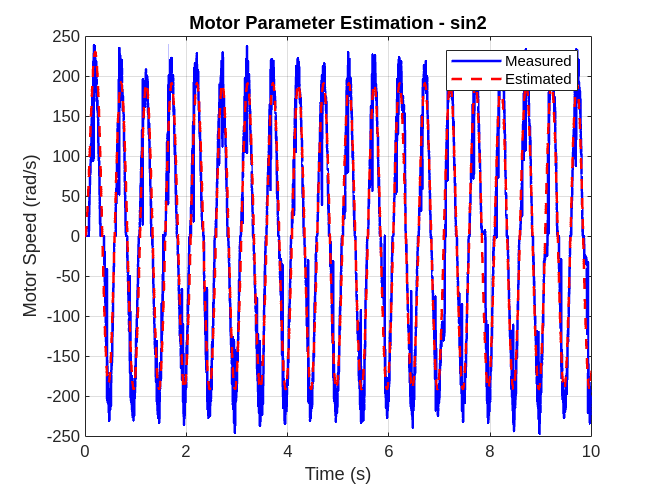

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.288081e+02    0.000e+00    8.440e+01
Poles of the system:
   1.0e+02 *

  -4.5442 + 9.5127i
  -4.5442 - 9.5127i

Poles of the system:
 -709.8702
 -198.8812

Poles of the system:
 -875.5240
  -33.2050

Poles of the system:
 -875.5240
  -33.2050

Poles of the system:
 -875.5246
  -33.2044

Poles of the system:
 -875.5240
  -33.2050

Poles of the system:
 -875.5240
  -33.2050

    1      12    1.252566e+02    0.000e+00    1.272e+04    3.084e-01
Poles of the system:
 -900.4440
   -8.2179

Poles of the system:
 -900.4440
   -8.2179

Poles of the system:
 -900.4441
   -8.2179

Poles of the system:
 -900.4440
   -8.2179

P

Poles of the system:
 -906.3133
   -2.3562



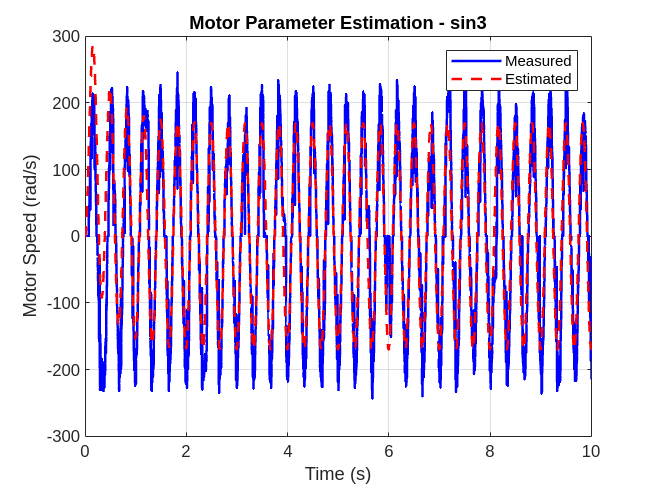

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    6.560774e+01    0.000e+00    9.611e+00
Poles of the system:
 -908.1161
   -0.5967

Poles of the system:
 -908.0553
   -0.6575

Poles of the system:
 -908.0553
   -0.6575

Poles of the system:
 -908.0553
   -0.6574

Poles of the system:
 -908.0553
   -0.6575

Poles of the system:
 -908.0553
   -0.6575

    1      11    6.102073e+01    0.000e+00    1.608e+04    2.441e-01
Poles of the system:
 -882.7654
  -26.0774

Poles of the system:
 -882.7654
  -26.0774

Poles of the system:
 -882.7677
  -26.0752

Poles of the system:
 -882.7654
  -26.0775

Poles of the system:
 -882.7654
  -26.0774

    2      16    4.850803e+01    

Poles of the system:
 -849.6483
  -60.2625



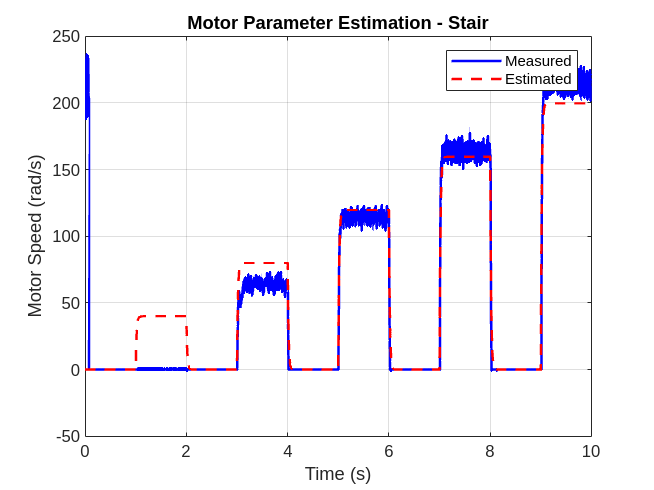

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    2.558531e+01    0.000e+00    3.430e+01
Poles of the system:
 -908.0824
   -0.6304

Poles of the system:
 -908.0426
   -0.6702

Poles of the system:
 -908.0426
   -0.6702

Poles of the system:
 -908.0426
   -0.6701

Poles of the system:
 -908.0426
   -0.6702

Poles of the system:
 -908.0426
   -0.6702

    1      11    9.268999e+00    0.000e+00    1.810e+05    2.440e-01
Poles of the system:
 -907.7081
   -1.0006

Poles of the system:
 -907.8805
   -0.8300

Poles of the system:
 -907.8805
   -0.8300

Poles of the system:
 -907.8805
   -0.8300

Poles of the system:
 -907.8805
   -0.8300

Poles of the system:
 -907.8805
 

Poles of the system:
 -908.1350
   -0.5682



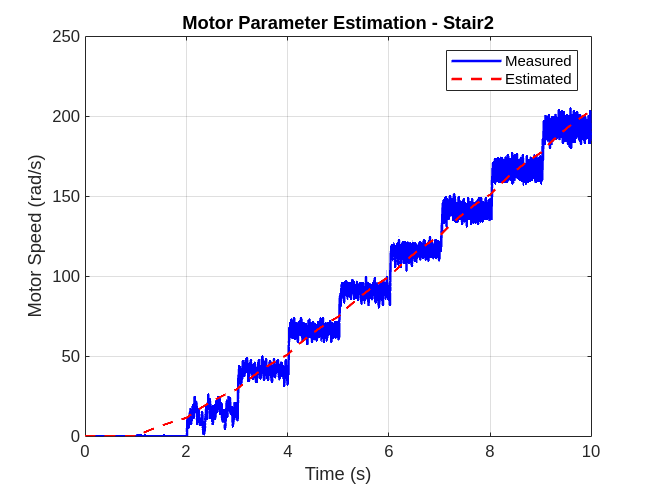

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    7.903148e+01    0.000e+00    1.413e+02
Poles of the system:
   1.0e+03 *

  -0.4544 + 1.3030i
  -0.4544 - 1.3030i

Poles of the system:
   1.0e+02 *

  -4.5436 + 2.3747i
  -4.5436 - 2.3747i

Poles of the system:
 -845.6492
  -63.0636

Poles of the system:
 -893.1030
  -15.6098

Poles of the system:
 -888.9425
  -19.7496

Poles of the system:
   1.0e+02 *

  -4.6305 + 3.1654i
  -4.6305 - 3.1654i

Poles of the system:
   1.0e+02 *

  -4.6305 + 3.1654i
  -4.6305 - 3.1654i

Poles of the system:
   1.0e+02 *

  -4.6302 + 3.1510i
  -4.6302 - 3.1510i

Poles of the system:
   1.0e+02 *

  -4.6305 + 3.1655i
  -4.6305 - 3.1655i

Poles of the system:
 -894.5164
  -15.2437



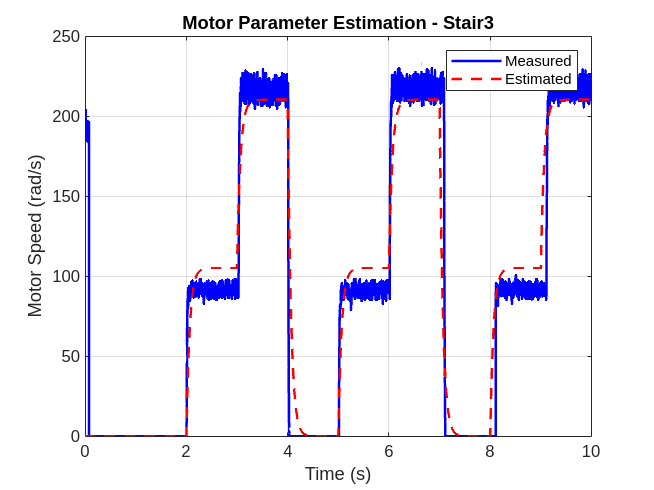


signals = {'Chirp', 'Chirp2', 'Chirp3', 'Step', 'Step2', 'Step3', 'Ramp', 'Ramp2', 'Ramp3', ...
           'sin', 'sin2', 'sin3', 'Stair', 'Stair2', 'Stair3'};

% Fixed motor parameters
Rm_fixed = 2.51186;   % Motor Resistance
Lm_fixed = 0.0027645; % Motor Inductance

% Optimization setup
params_init = [0.05, 0.001, 0.0001, 0.5]; % Initial values
lb = [1e-9, 1e-9, 1e-9, 0.01];  % Lower bound
ub = [Inf, Inf, Inf, 0.99];  % Upper bound
options = optimset('Display', 'iter', 'TolFun', 1e-9, 'TolX', 1e-9);

% Storage for estimated parameters
estimated_params = zeros(length(signals), 4);

% Loop over all signals
for i = 1:length(signals)
    signal_name = signals{i};

    % Load input voltage (V) and measured speed (omega)
    V = eval(['V_input_', signal_name]);
    omega = eval(['omega_', signal_name]);

    % Assign correct time vector
    t = eval(['Time_input_', signal_name]);

    % Ensure column vectors
    t = t(:); 
    V = V(:);
    omega = omega(:);

    % Perform optimization using RMSE cost function
    estimated_params(i, :) = fmincon(@(p) cost_function_rmse(p, Rm_fixed, Lm_fixed, t, V, omega), ...
                               params_init, [], [], [], [], lb, ub, [], options);

    % Simulate response
    omega_sim = motor_model(estimated_params(i, :), Rm_fixed, Lm_fixed, t, V);

    % Plot Measured vs Estimated Response
    figure;
    plot(t, omega, 'b', 'LineWidth', 1.5); hold on;
    plot(t, omega_sim, 'r--', 'LineWidth', 1.5);
    xlabel('Time (s)');
    ylabel('Motor Speed (rad/s)');
    legend('Measured', 'Estimated');
    title(['Motor Parameter Estimation - ', signal_name]);
    grid on;
end


% Store estimated parameters in a table
resultsTable = array2table(estimated_params, 'VariableNames', {'Ke', 'Jm', 'Bm', 'Efficiency'}, ...
                           'RowNames', signals);
disp(resultsTable);

                 Ke            Jm            Bm        Efficiency
              _________    __________    __________    __________

    Chirp      0.022601    2.1125e-05    5.2009e-05     0.72905  
    Chirp2    0.0081197    2.6281e-06    7.7233e-07     0.98996  
    Chirp3    0.0045179     3.896e-07    2.1953e-07     0.46174  
    Step       0.066576    3.2217e-05     3.456e-05     0.94354  
    Step2      0.059614    2.5223e-05    3.7398e-06     0.77814  
    Step3      0.079668    3.7491e-05    1.8057e-06     0.64895  
    Ramp       0.035925    0.00080409     9.584e-05     0.70509  
    Ramp2      0.049468      0.000348    9.5156e-05     0.87539  
    Ramp3       0.05557    9.3158e-05    6.2972e-0

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    5.094068e+06    0.000e+00    1.260e+08
Poles of the system:
   1.0e+02 *

  -4.6452 + 5.9707i
  -4.6452 - 5.9707i

Poles of the system:
   1.0e+02 *

  -4.6452 + 5.9707i
  -4.6452 - 5.9707i

Poles of the system:
   1.0e+02 *

  -4.6449 + 5.9567i
  -4.6449 - 5.9567i

Poles of the system:
   1.0e+02 *

  -4.6452 + 5.9707i
  -4.6452 - 5.9707i

Poles of the system:
   1.0e+02 *

  -4.6452 + 5.9707i
  -4.6452 - 5.9707i

    1      10    3.538098e+06    0.000e+00    1.195e+09    2.155e-01
Poles of the system:
 -893.4594
  -15.4964

Poles of the system:
 -893.4594
  -15.4964

Poles of the system:
 -893.4602
  -15.4956

Poles

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.645788e+05    0.000e+00    5.548e+06
Poles of the system:
   1.0e+06 *

  -0.0167 + 6.1606i
  -0.0167 - 6.1606i



Poles of the system:
   1.0e+05 *

  -0.0053 + 2.7569i
  -0.0053 - 2.7569i



Poles of the system:
   1.0e+05 *

  -0.0048 + 1.0569i
  -0.0048 - 1.0569i



Poles of the system:
   1.0e+04 *

  -0.0466 + 4.7240i
  -0.0466 - 4.7240i



Poles of the system:
   1.0e+02 *

  -4.6592 + 8.1013i
  -4.6592 - 8.1013i

Poles of the system:
   1.0e+02 *

  -4.6592 + 8.1013i
  -4.6592 - 8.1013i

Poles of the system:
   1.0e+02 *

  -4.6589 + 8.0854i
  -4.6589 - 8.0854i

Poles of the system:
   1.0e+02 *

  -4.6593 + 8.1013i
  -4.6593 - 8.1013i

Poles of the system:
   1.0e+02 *

  -4.6592 + 8.1013i
  -4.6592 - 8.1013i

    1      14    1.452477e+05    0.000e+00    2.235e+07    1.964e-01
Poles of the system:
 -869.8977
  -39.3621

Poles of the system:
 -869.8977
  -39.3621

Poles of the system:
 -869.9010
  -39.3589

Poles of the system:
 -869.8977
  -39.3622

Poles of the system:
 -869.8977
  -39.3621

    2      19    1.429355e+05    0.000e+00    1.069e+07    3.099e-01
Poles of the system:
 -908.6126
   -0.0849

Poles of the system:
 -905.2197
   -3.5799

Poles of the system:
 -905.2197
   -3.5799

Poles of the system:
 -905.2198
   -3.5798

Poles of the system:
 -905.2197
   -3.5799

Poles of the system:
 -905.2197
   -3.5799

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    2.256891e+01    0.000e+00    2.790e+02
Poles of the system:
   1.0e+02 *

  -4.5469 + 5.8325i
  -4.5469 - 5.8325i

Poles of the system:
 -849.9516
  -58.9005

Poles of the system:
 -849.9516
  -58.9005

Poles of the system:
 -849.9531
  -58.8990

Poles of the system:
 -849.9516
  -58.9005

Poles of the system:
 -849.9516
  -58.9005

    1      11    2.219140e+01    0.000e+00    1.338e+03    3.804e-01
Poles of the system:
 -866.1182
  -42.8915

Poles of the system:
 -866.1182
  -42.8915

Poles of the system:
 -866.1192
  -42.8904

Poles of the system:
 -866.1182
  -42.8915

Poles of the system:
 -866.1182
  -42.8915

 

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    8.917268e-01    0.000e+00    2.205e+01
Poles of the system:
 -902.8332
   -5.9851

Poles of the system:
 -902.8332
   -5.9851

Poles of the system:
 -902.8333
   -5.9850

Poles of the system:
 -902.8332
   -5.9851

Poles of the system:
 -902.8332
   -5.9851

    1      10    7.444726e-01    0.000e+00    2.801e+01    1.494e-01
Poles of the system:
 -903.6156
   -5.3022

Poles of the system:
 -903.6156
   -5.3022

Poles of the system:
 -903.6157
   -5.3022

Poles of the system:
 -903.6156
   -5.3023

Poles of the system:
 -903.6156
   -5.3022

    2      15    7.676008e-01    0.000e+00    1.049e+01    2.242e-02
Poles of

Poles of the system:
 -901.5200
   -9.5547



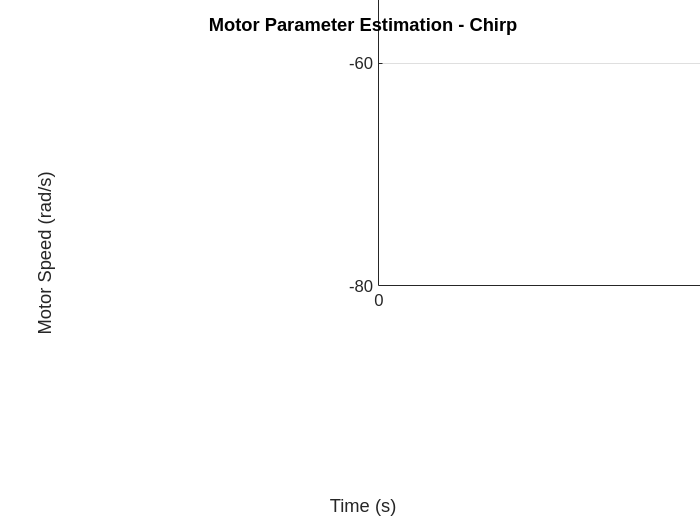

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    6.266598e+07    0.000e+00    4.311e+08
Poles of the system:
   1.0e+02 *

  -4.6448 + 5.9012i
  -4.6448 - 5.9012i

Poles of the system:
   1.0e+02 *

  -4.6448 + 5.9012i
  -4.6448 - 5.9012i

Poles of the system:
   1.0e+02 *

  -4.6445 + 5.8872i
  -4.6445 - 5.8872i

Poles of the system:
   1.0e+02 *

  -4.6448 + 5.9012i
  -4.6448 - 5.9012i

Poles of the system:
   1.0e+02 *

  -4.6448 + 5.9012i
  -4.6448 - 5.9012i

    1      10    5.573341e+07    0.000e+00    4.468e+09    2.162e-01
Poles of the system:
 -895.3597
  -13.5592

Poles of the system:
 -895.3597
  -13.5592

Poles of the system:
 -895.3603
  -13.5585

Poles

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    6.468939e+05    0.000e+00    3.825e+06
Poles of the system:
   1.0e+02 *

  -4.6467 + 6.2186i
  -4.6467 - 6.2186i

Poles of the system:
   1.0e+02 *

  -4.6467 + 6.2186i
  -4.6467 - 6.2186i

Poles of the system:
   1.0e+02 *

  -4.6464 + 6.2044i
  -4.6464 - 6.2044i

Poles of the system:
   1.0e+02 *

  -4.6467 + 6.2186i
  -4.6467 - 6.2186i

Poles of the system:
   1.0e+02 *

  -4.6467 + 6.2186i
  -4.6467 - 6.2186i

    1      10    6.100980e+05    0.000e+00    3.613e+07    2.132e-01
Poles of the system:
 -888.5740
  -20.4822

Poles of the system:
 -888.5740
  -20.4822

Poles of the system:
 -888.5753
  -20.4808

Poles

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    7.915789e+01    0.000e+00    2.723e+02
Poles of the system:
   1.0e+02 *

  -4.5462 + 5.7621i
  -4.5462 - 5.7621i

Poles of the system:
 -842.8019
  -66.0346

Poles of the system:
 -842.8019
  -66.0346

Poles of the system:
 -842.8036
  -66.0330

Poles of the system:
 -842.8019
  -66.0346

Poles of the system:
 -842.8019
  -66.0346

    1      11    7.885083e+01    0.000e+00    1.606e+03    4.004e-01
Poles of the system:
 -857.8905
  -51.1008

Poles of the system:
 -857.8905
  -51.1008

Poles of the system:
 -857.8917
  -51.0995

Poles of the system:
 -857.8905
  -51.1008

Poles of the system:
 -857.8905
  -51.1008

 

Poles of the system:
   1.0e+03 *

  -0.4931 + 7.0724i
  -0.4931 - 7.0724i



Poles of the system:
   1.0e+03 *

  -0.4795 + 5.6945i
  -0.4795 - 5.6945i



Poles of the system:
   1.0e+03 *

  -0.4934 + 7.0724i
  -0.4934 - 7.0724i



Poles of the system:
   1.0e+03 *

  -0.4931 + 7.0724i
  -0.4931 - 7.0724i



    9      60    7.051501e+01    0.000e+00    9.370e+03    1.752e-02
Poles of the system:
   1.0e+03 *

  -0.4545 + 6.4328i
  -0.4545 - 6.4328i



Poles of the system:
   1.0e+03 *

  -0.4545 + 6.4328i
  -0.4545 - 6.4328i



Poles of the system:
   1.0e+03 *

  -0.4544 + 5.1735i
  -0.4544 - 5.1735i



Poles of the system:
   1.0e+03 *

  -0.4548 + 6.4328i
  -0.4548 - 6.4328i



Poles of the system:
   1.0e+03 *

  -0.4545 + 6.4328i
  -0.4545 - 6.4328i



   10      65    6.949344e+01    0.000e+00    1.425e+04    5.743e-03
Poles of the system:
 -907.7112
   -1.1567

Poles of the system:
   1.0e+03 *

  -0.4545 + 3.0070i
  -0.4545 - 3.0070i



Poles of the system:
   1.0e+03 *

  -0.4545 + 3.0070i
  -0.4545 - 3.0070i



Poles of the system:
   1.0e+03 *

  -0.4544 + 2.4606i
  -0.4544 - 2.4606i



Poles of the system:
   1.0e+03 *

  -0.4547 + 3.0070i
  -0.4547 - 3.0070i



Poles of the system:
   1.0e+03 *

  -0.4545 + 3.0070i
  -0.4545 - 3.0070i



   11      71    5.897573e+01    0.000e+00    1.438e+05    2.813e-02
Poles of the system:
 -908.4969
   -0.2363

Poles of the system:
   1.0e+03 *

  -0.4544 + 1.1200i
  -0.4544 - 1.1200i

Poles of the system:
   1.0e+03 *

  -0.4544 + 1.1200i
  -0.4544 - 1.1200i

Poles of the system:
   1.0e+02 *

  -4.5438 + 9.5844i
  -4.5438 - 9.5844i

Poles of the system:
   1.0e+03 *

  -0.4545 + 1.1200i
  -0.4545 - 1.1200i

Poles of the system:
   1.0e+03 *

  -0.4544 + 1.1200i
  -0.4544 - 1.1200i

   12      77    4.096281e+01    0.000e+00    1.601e+06    1.413e-02
Poles of the system:
 -908.6087
   -0.0181

Poles of the system:
 -826.6665
  -81.9761

Poles of the system:
 -826.6661
  -81.9765

Poles of the system:
 -831.3640
  -77.2770

Poles of the system:
 -826.6605
  -82.0370

Poles of the system:
 -826.6665
  -81.9761

   13      83    3.719683e+01    0.000e+00    1.252e+07    7.102e-03
Poles of the system:
 -908.6127
   -0.0011

Poles of the system:
 -907.0836
   -1.5313

Poles of the syst

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    9.641829e-01    0.000e+00    6.633e+00
Poles of the system:
 -907.4578
   -1.2313

Poles of the system:
 -907.4578
   -1.2313

Poles of the system:
 -907.4578
   -1.2313

Poles of the system:
 -907.4578
   -1.2313

Poles of the system:
 -907.4578
   -1.2313

    1      10    9.629839e-01    0.000e+00    2.408e+01    7.987e-02
Poles of the system:
 -905.2359
   -3.4520

Poles of the system:
 -905.2359
   -3.4520

Poles of the system:
 -905.2359
   -3.4520

Poles of the system:
 -905.2359
   -3.4520

Poles of the system:
 -905.2359
   -3.4520

    2      15    9.677185e-01    0.000e+00    3.550e+01    2.175e-01
Poles of

Poles of the system:
   1.0e+03 *

  -0.4544 + 2.3778i
  -0.4544 - 2.3778i



Poles of the system:
   1.0e+03 *

  -0.4544 + 2.3778i
  -0.4544 - 2.3778i



Poles of the system:
   1.0e+03 *

  -0.4544 + 2.3778i
  -0.4544 - 2.3778i



Poles of the system:
   1.0e+03 *

  -0.4544 + 2.3778i
  -0.4544 - 2.3778i



   13      70    9.999797e-01    0.000e+00    2.545e-04    4.238e+02
Poles of the system:
   1.0e+03 *

  -0.4544 + 2.3012i
  -0.4544 - 2.3012i



Poles of the system:
   1.0e+03 *

  -0.4544 + 2.3012i
  -0.4544 - 2.3012i



Poles of the system:
   1.0e+03 *

  -0.4544 + 2.3012i
  -0.4544 - 2.3012i



Poles of the system:
   1.0e+03 *

  -0.4544 + 2.3012i
  -0.4544 - 2.3012i



Poles of the system:
   1.0e+03 *

  -0.4544 + 2.3012i
  -0.4544 - 2.3012i



   14      75    9.999784e-01    0.000e+00    2.002e-06    4.786e+01
Poles of the system:
   1.0e+02 *

  -4.5441 + 8.9968i
  -4.5441 - 8.9968i

Poles of the system:
   1.0e+02 *

  -4.5441 + 8.9968i
  -4.5441 - 8.9968i

Poles of the system:
   1.0e+02 *

  -4.5441 + 8.9968i
  -4.5441 - 8.9968i

Poles of the system:
   1.0e+02 *

  -4.5441 + 8.9968i
  -4.5441 - 8.9968i

Poles of the system:
   1.0e+02 *

  -4.5441 + 8.9968i
  -4.5441 - 8.9968i

   15      80    9.998832e-01    0.000e+00    2.000e-06    5.991e+02
Poles of the system:
 -896.7317
  -11.9905

Poles of the system:
 -896.7317
  -11.9905

Poles of the system:
 -896.7317
  -11.9905

Poles of the system:
 -896.7317
  -11.9905

Poles of the system:
 -896.7317
  -11.9905

   16      85    9.883470e-01    0.000e+00    2.867e-02    1.345e+02
Poles of the system:
 -902.3004
   -6.3135

Poles of the system:
 -902.3004
   -6.3135

Poles of the system:
 -902.3004
   -6.3135

Poles of the system:
 -902.3004
   -6.3135

Poles of the syst

Poles of the system:
   1.0e+04 *

  -0.0454 + 1.6873i
  -0.0454 - 1.6873i



Poles of the system:
   1.0e+04 *

  -0.0454 + 1.4557i
  -0.0454 - 1.4557i



Poles of the system:
   1.0e+04 *

  -0.0455 + 1.6873i
  -0.0455 - 1.6873i



Poles of the system:
   1.0e+04 *

  -0.0454 + 1.6873i
  -0.0454 - 1.6873i



   36     187    9.168726e-01    0.000e+00    1.228e+01    6.183e-04
Poles of the system:
   1.0e+04 *

  -0.0457 + 9.6681i
  -0.0457 - 9.6681i



Poles of the system:
   1.0e+04 *

  -0.0457 + 9.6681i
  -0.0457 - 9.6681i



Poles of the system:
   1.0e+04 *

  -0.0455 + 2.6513i
  -0.0455 - 2.6513i



Poles of the system:
   1.0e+04 *

  -0.0464 + 9.6681i
  -0.0464 - 9.6681i



Poles of the system:
   1.0e+04 *

  -0.0457 + 9.6681i
  -0.0457 - 9.6681i



   37     192    9.132415e-01    0.000e+00    1.199e+01    7.990e-03
Poles of the system:
   1.0e+03 *

  -0.8398 + 5.9415i
  -0.8398 - 5.9415i



Poles of the system:
   1.0e+03 *

  -0.8398 + 5.9415i
  -0.8398 - 5.9415i



Poles of the system:
   1.0e+03 *

  -0.4786 + 1.4275i
  -0.4786 - 1.4275i

Poles of the system:
   1.0e+03 *

  -0.8472 + 5.9416i
  -0.8472 - 5.9416i



Poles of the system:
   1.0e+03 *

  -0.8398 + 5.9415i
  -0.8398 - 5.9415i



   38     197    1.691942e-01    0.000e+00    5.773e+04    1.679e-01
Poles of the system:
 -902.5987
 -761.8401

Poles of the system:
   1.0e+03 *

  -0.8360 + 2.9849i
  -0.8360 - 2.9849i

Poles of the system:
   1.0e+03 *

  -0.8379 + 4.4633i
  -0.8379 - 4.4633i



Poles of the system:
   1.0e+03 *

  -0.8388 + 5.2024i
  -0.8388 - 5.2024i



Poles of the system:
   1.0e+03 *

  -0.8393 + 5.5720i
  -0.8393 - 5.5720i



Poles of the system:
   1.0e+03 *

  -0.8393 + 5.5720i
  -0.8393 - 5.5720i



Poles of the system:
   1.0e+03 *

  -0.4785 + 1.3303i
  -0.4785 - 1.3303i

Poles of the system:
   1.0e+03 *

  -0.8467 + 5.5721i
  -0.8467 - 5.5721i



Poles of the system:
   1.0e+03 *

  -0.8393 + 5.5720i
  -0.8393 - 5.5720i



   39     206    1.660098e-01    0.000e+00    6.956e+04    6.178e-04
Poles of the system:
   1.0e+03 *

  -1.4550 + 5.3218i
  -1.4550 - 5.3218i

Poles of the system:
   1.0e+03 *

  -1.4550 + 5.3219i
  -1.4550 - 5.3219i

Poles of the system:
   1.0e+03 *

  -0.5176 + 1.2873i
  -0.5176 - 1.2873i

Poles of the system:
   1.0e+03 *

  -1.4624 + 5.3211i
  -1.4624 - 5.3211i

Poles of the system:
   1.0e+03 *

  -1.4550 + 5.3218i
  -1.4550 - 5.3218i

   40     211    1.659102e-01    0.000e+00    7.209e+04    3.499e-04
Poles of the system:
   1.0e+03 *

  -1.3085 + 1.6469i
  -1.3085 - 1.6469i

Poles of the system:
   1.0e+03 *

  -1.3315 + 2.5622i
  -1.3315 - 2.5622i

Poles of the system:
   1.0e+03 *

  -1.3315 + 2.5622i
  -1.3315 - 2.5622i

Poles of the system:
   1.0e+03 *

  -0.6100 + 1.0525i
  -0.6100 - 1.0525i

Poles of the system:
   1.0e+03 *

  -1.3338 + 2.5619i
  -1.3338 - 2.5619i

Poles of the system:
   1.0e+03 *

  -1.3315 + 2.5622i
  -1.3315 - 2.5622i

   41     217    1.654805e

Poles of the system:
 -898.6129
  -10.2937



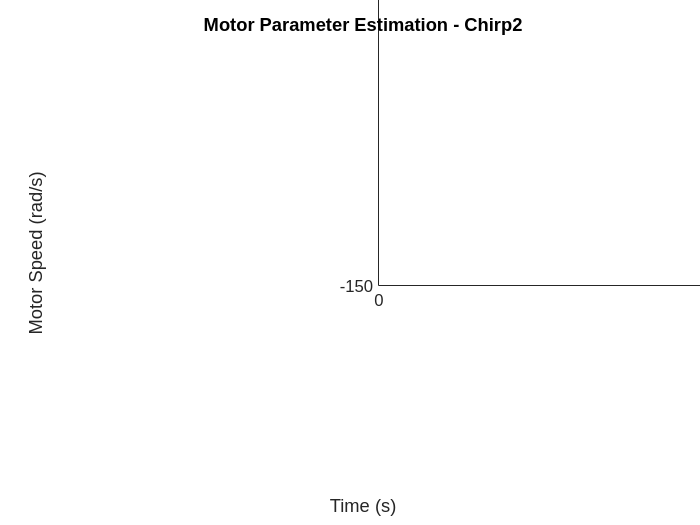

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.891221e+08    0.000e+00    6.806e+08
Poles of the system:
   1.0e+02 *

  -4.6446 + 5.8659i
  -4.6446 - 5.8659i

Poles of the system:
   1.0e+02 *

  -4.6446 + 5.8659i
  -4.6446 - 5.8659i

Poles of the system:
   1.0e+02 *

  -4.6443 + 5.8519i
  -4.6443 - 5.8519i

Poles of the system:
   1.0e+02 *

  -4.6446 + 5.8659i
  -4.6446 - 5.8659i

Poles of the system:
   1.0e+02 *

  -4.6446 + 5.8659i
  -4.6446 - 5.8659i

    1      10    1.766774e+08    0.000e+00    7.722e+09    2.165e-01
Poles of the system:
 -895.7275
  -13.1852

Poles of the system:
 -895.7275
  -13.1852

Poles of the system:
 -895.7281
  -13.1846

Poles

Poles of the system:
   1.0e+03 *

  -0.4947 + 4.0627i
  -0.4947 - 4.0627i



Poles of the system:
   1.0e+03 *

  -0.4618 + 1.7058i
  -0.4618 - 1.7058i

Poles of the system:
   1.0e+03 *

  -0.4969 + 4.0629i
  -0.4969 - 4.0629i



Poles of the system:
   1.0e+03 *

  -0.4947 + 4.0627i
  -0.4947 - 4.0627i



    8      46    8.133281e+07    0.000e+00    3.254e+12    4.007e-03
Poles of the system:
 -522.6555
 -386.9190

Poles of the system:
 -522.6520
 -386.9225

Poles of the system:
 -575.6021
 -333.9248

Poles of the system:
 -522.5071
 -387.1196

Poles of the system:
 -522.6555
 -386.9190

    9      51    8.089056e+07    0.000e+00    2.972e+12    6.778e-05
Poles of the system:
 -862.1436
  -46.5371

Poles of the system:
 -862.1435
  -46.5372

Poles of the system:
 -862.6257
  -46.0543

Poles of the system:
 -862.1430
  -46.5476

Poles of the system:
 -862.1436
  -46.5371

   10      56    7.966399e+07    0.000e+00    1.862e+12    2.846e-04
Poles of the system:
 -864.8745
  -43.7892

Poles of the system:
 -864.8744
  -43.7893

Poles of the system:
 -865.3007
  -43.3625

Poles of the system:
 -864.8740
  -43.7990

Poles of the system:
 -864.8745
  -43.7892

   11      61    7.958048e+07    0.000e+00    1.785e+12    1.631e-05
Poles of the system:
 -879.5271
  -29.0862

Poles of the system:

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.161588e+06    0.000e+00    3.229e+06
Poles of the system:
   1.0e+02 *

  -4.6458 + 6.0608i
  -4.6458 - 6.0608i

Poles of the system:
   1.0e+02 *

  -4.6458 + 6.0608i
  -4.6458 - 6.0608i

Poles of the system:
   1.0e+02 *

  -4.6454 + 6.0467i
  -4.6454 - 6.0467i

Poles of the system:
   1.0e+02 *

  -4.6458 + 6.0608i
  -4.6458 - 6.0608i

Poles of the system:
   1.0e+02 *

  -4.6458 + 6.0608i
  -4.6458 - 6.0608i

    1      10    1.120993e+06    0.000e+00    3.119e+07    2.147e-01
Poles of the system:
 -890.9994
  -18.0184

Poles of the system:
 -890.9994
  -18.0184

Poles of the system:
 -891.0005
  -18.0172

Poles

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.375148e+02    0.000e+00    2.474e+02
Poles of the system:
   1.0e+02 *

  -4.5460 + 5.7347i
  -4.5460 - 5.7347i

Poles of the system:
 -841.8464
  -66.9862

Poles of the system:
 -841.8464
  -66.9862

Poles of the system:
 -841.8481
  -66.9846

Poles of the system:
 -841.8464
  -66.9863

Poles of the system:
 -841.8464
  -66.9862

    1      11    1.372443e+02    0.000e+00    1.661e+03    4.033e-01
Poles of the system:
 -856.6198
  -52.3667

Poles of the system:
 -856.6198
  -52.3667

Poles of the system:
 -856.6210
  -52.3655

Poles of the system:
 -856.6198
  -52.3667

Poles of the system:
 -856.6198
  -52.3667

 

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    9.784846e-01    0.000e+00    3.521e+00
Poles of the system:
 -908.0222
   -0.6367

Poles of the system:
 -908.0222
   -0.6367

Poles of the system:
 -908.0222
   -0.6367

Poles of the system:
 -908.0222
   -0.6367

Poles of the system:
 -908.0222
   -0.6367

    1      10    9.882665e-01    0.000e+00    2.015e+01    6.565e-02
Poles of the system:
 -906.4952
   -2.1858

Poles of the system:
 -906.4952
   -2.1858

Poles of the system:
 -906.4952
   -2.1857

Poles of the system:
 -906.4952
   -2.1858

Poles of the system:
 -906.4952
   -2.1858

    2      15    9.877638e-01    0.000e+00    2.216e+01    2.854e-01
Poles of

Poles of the system:
   1.0e+03 *

  -0.4605 + 2.4538i
  -0.4605 - 2.4538i



Poles of the system:
   1.0e+03 *

  -0.4574 + 1.7083i
  -0.4574 - 1.7083i

Poles of the system:
   1.0e+03 *

  -0.4610 + 2.4539i
  -0.4610 - 2.4539i



Poles of the system:
   1.0e+03 *

  -0.4605 + 2.4538i
  -0.4605 - 2.4538i



   20     107    6.325869e-01    0.000e+00    5.844e+03    2.638e-02
Poles of the system:
 -903.0166
   -5.5967

Poles of the system:
 -903.0166
   -5.5967

Poles of the system:
 -903.0409
   -5.5724

Poles of the system:
 -903.0166
   -5.6011

Poles of the system:
 -903.0166
   -5.5967

   21     112    3.350996e-01    0.000e+00    5.817e+04    1.915e-02
Poles of the system:
 -908.5602
   -0.0530

Poles of the system:
 -906.6746
   -1.9387

Poles of the system:
 -905.0100
   -3.6033

Poles of the system:
 -904.0493
   -4.5640

Poles of the system:
 -904.0493
   -4.5640

Poles of the system:
 -904.0699
   -4.5434

Poles of the system:
 -904.0493
   -4.5685

Poles of the system:
 -904.0493
   -4.5640

   22     120    3.270392e-01    0.000e+00    8.058e+04    1.685e-03
Poles of the system:
 -559.4215
 -349.2678

Poles of the system:
 -559.4148
 -349.2745

Poles of the system:
 -771.8586
 -136.7955

Poles of the system:
 -557.9928
 -351.5470

Poles of the system:
 -559.4214
 -349.2679

 

Poles of the system:
 -898.8715
  -10.3047



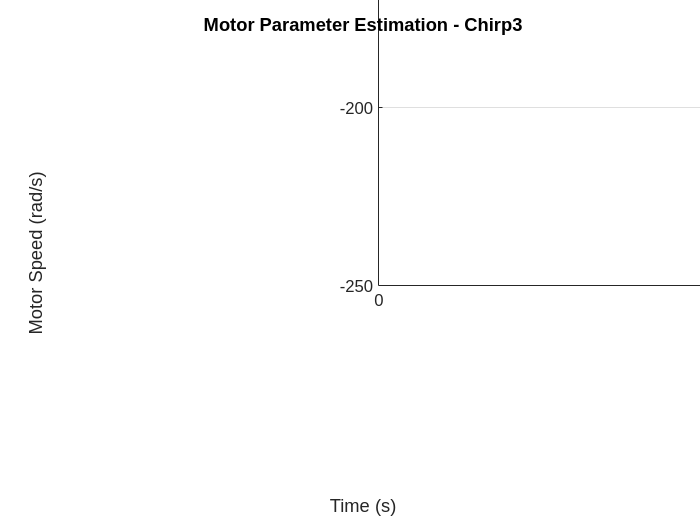

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    8.966088e+06    0.000e+00    8.718e+09
Poles of the system:
 -786.7710
 -124.4682

Poles of the system:
 -904.8556
   -3.9659

Poles of the system:
 -907.1874
   -1.5626

Poles of the system:
 -907.1874
   -1.5626

Poles of the system:
 -907.1875
   -1.5626

Poles of the system:
 -907.1874
   -1.5626

Poles of the system:
 -907.1874
   -1.5626

    1      12    7.335714e+06    0.000e+00    3.833e+06    4.645e-02
Poles of the system:
 -903.1266
   -5.7525

Poles of the system:
 -903.1266
   -5.7525

Poles of the system:
 -903.1269
   -5.7522

Poles of the system:
 -903.1266
   -5.7526

Poles of the system:
 -903.1266
 

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.668989e+05    0.000e+00    5.726e+08
Poles of the system:
 -901.9663
   -6.8654

Poles of the system:
 -906.2805
   -2.4786

Poles of the system:
 -907.4143
   -1.3193

Poles of the system:
 -907.8110
   -0.9117

Poles of the system:
 -907.8110
   -0.9117

Poles of the system:
 -907.8110
   -0.9117

Poles of the system:
 -907.8110
   -0.9117

Poles of the system:
 -907.8110
   -0.9117

    1      13    1.390767e+05    0.000e+00    1.638e+05    1.206e-02
Poles of the system:
 -900.4345
   -8.6039

Poles of the system:
 -900.4345
   -8.6039

Poles of the system:
 -900.4350
   -8.6034

Poles of the system:
 -900.4345
 

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    2.994193e+01    0.000e+00    1.456e+04
Poles of the system:
   1.0e+03 *

  -0.4552 + 2.9234i
  -0.4552 - 2.9234i



Poles of the system:
   1.0e+02 *

  -4.5464 + 9.5419i
  -4.5464 - 9.5419i

Poles of the system:
   1.0e+02 *

  -4.5448 + 0.6791i
  -4.5448 - 0.6791i

Poles of the system:
 -850.5789
  -58.2478

Poles of the system:
 -820.8204
  -89.7785

Poles of the system:
 -904.8953
   -3.9243

Poles of the system:
 -907.1910
   -1.5588

Poles of the system:
 -907.1910
   -1.5588

Poles of the system:
 -907.1910
   -1.5588

Poles of the system:
 -907.1910
   -1.5588

Poles of the system:
 -907.1910
   -1.5588

    1      16    2.714282e+01    0.000e+00    7.082e+00    4.639e-02
Poles of the system:
 -902.4600
   -6.4441

Poles of the system:
 -902.4600
   -6.4441

Poles of the system:
 -902.4603
   -6.4438

Poles of the system:
 -902.4600
   -6.4441

Poles of the system:
 -902.4600
   -6.4441

    2      21    2.015160e+01    0.000e+00    7.379e+03    4.464e-01
Poles of the system:
 -908.1954
   -1.3468

Poles of the system:
 -905.5707
   -3.4939

Poles of the system:
 -904.0418
   -4.9266

Poles 

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.222941e-01    0.000e+00    1.189e+02
Poles of the system:
 -905.3709
   -3.3749

Poles of the system:
 -906.9478
   -1.7853

Poles of the system:
 -906.9478
   -1.7853

Poles of the system:
 -906.9478
   -1.7852

Poles of the system:
 -906.9478
   -1.7853

Poles of the system:
 -906.9478
   -1.7853

    1      11    2.172172e-01    0.000e+00    1.746e+02    5.829e-02
Poles of the system:
 -907.8652
   -0.8848

Poles of the system:
 -907.8652
   -0.8848

Poles of the system:
 -907.8652
   -0.8848

Poles of the system:
 -907.8652
   -0.8848

Poles of the system:
 -907.8652
   -0.8848

    2      16    2.041010e-01    

Poles of the system:
 -853.5286
  -56.1569



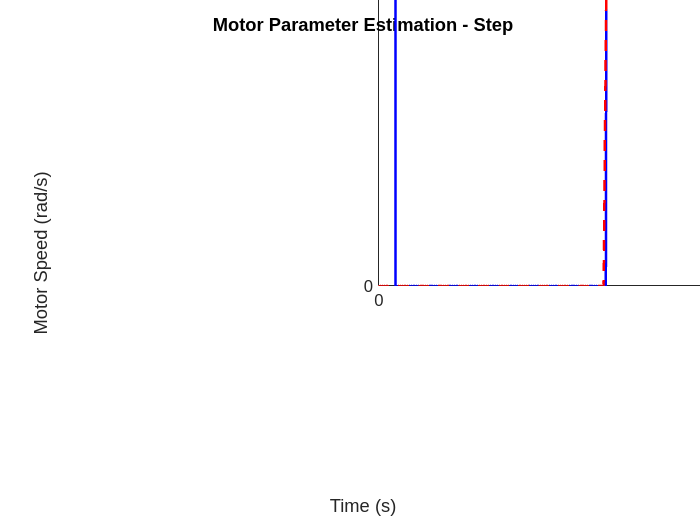

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.920790e+07    0.000e+00    1.205e+08
Poles of the system:
   1.0e+02 *

  -4.6260 + 1.8892i
  -4.6260 - 1.8892i

Poles of the system:
   1.0e+02 *

  -4.6260 + 1.8892i
  -4.6260 - 1.8892i

Poles of the system:
   1.0e+02 *

  -4.6257 + 1.8700i
  -4.6257 - 1.8700i

Poles of the system:
   1.0e+02 *

  -4.6260 + 1.8892i
  -4.6260 - 1.8892i

Poles of the system:
   1.0e+02 *

  -4.6260 + 1.8892i
  -4.6260 - 1.8892i

    1      10    5.201059e+06    0.000e+00    1.757e+10    2.504e-01
Poles of the system:
 -903.4402
   -5.4185

Poles of the system:
 -903.4402
   -5.4185

Poles of the system:
 -903.4405
   -5.4182

Poles

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    2.617680e+05    0.000e+00    3.703e+05
Poles of the system:
 -907.9779
   -0.6355

Poles of the system:
 -908.0548
   -0.6144

Poles of the system:
 -908.0548
   -0.6144

Poles of the system:
 -908.0548
   -0.6144

Poles of the system:
 -908.0548
   -0.6144

Poles of the system:
 -908.0548
   -0.6144

    1      11    2.392599e+05    0.000e+00    1.028e+09    5.443e-04
Poles of the system:
 -464.7336
 -451.8153

Poles of the system:
 -464.7262
 -451.8227

Poles of the system:
 -485.2796
 -431.2428

Poles of the system:
 -464.6175
 -451.9347

Poles of the system:
 -464.7332
 -451.8157

    2      16    1.305309e+05    

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    4.382463e+01    0.000e+00    1.375e+02
Poles of the system:
   1.0e+03 *

  -0.4544 + 1.2206i
  -0.4544 - 1.2206i

Poles of the system:
   1.0e+02 *

  -4.5436 + 1.7701i
  -4.5436 - 1.7701i

Poles of the system:
 -851.5347
  -57.1780

Poles of the system:
 -894.3261
  -14.3867

Poles of the system:
 -872.4731
  -36.1852

Poles of the system:
   1.0e+02 *

  -4.6247 + 2.2550i
  -4.6247 - 2.2550i

Poles of the system:
   1.0e+02 *

  -4.6247 + 2.2550i
  -4.6247 - 2.2550i

Poles of the system:
   1.0e+02 *

  -4.6245 + 2.2380i
  -4.6245 - 2.2380i

Poles of the system:
   1.0e+02 *

  -4.6247 + 2.2551i
  -4.6247 - 2.2551i

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    9.425783e-02    0.000e+00    5.913e-01
Poles of the system:
 -798.7511
 -110.4434

Poles of the system:
 -798.7511
 -110.4434

Poles of the system:
 -798.9274
 -110.2663

Poles of the system:
 -798.7509
 -110.4450

Poles of the system:
 -798.7511
 -110.4434

    1      10    1.109085e-02    0.000e+00    1.477e+02    1.199e-01
Poles of the system:
 -908.6100
   -0.4547

Poles of the system:
 -881.4116
  -27.7094

Poles of the system:
 -847.6155
  -61.5395

Poles of the system:
 -825.2232
  -83.9508

Poles of the system:
 -825.2232
  -83.9509

Poles of the system:
 -825.3468
  -83.8265

Poles of the system:
 -825.2231
 

Poles of the system:
 -862.6293
  -46.1317



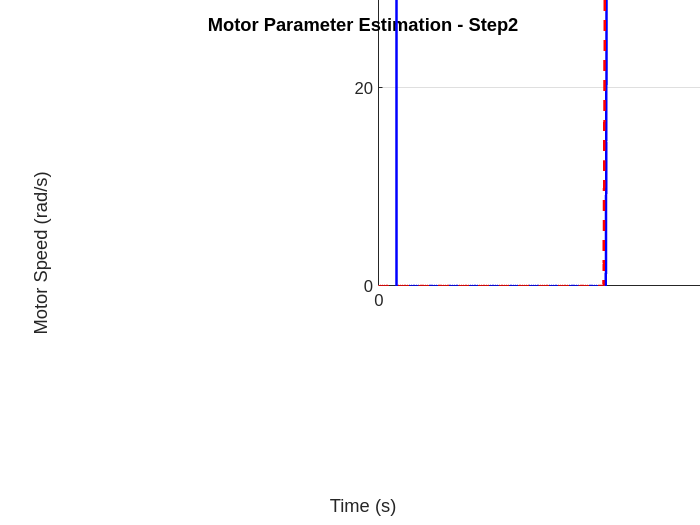

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    2.264367e+07    0.000e+00    1.337e+11
Poles of the system:
 -904.9846
   -3.7820

Poles of the system:
 -906.8362
   -1.9029

Poles of the system:
 -906.8362
   -1.9029

Poles of the system:
 -906.8363
   -1.9028

Poles of the system:
 -906.8362
   -1.9029

Poles of the system:
 -906.8362
   -1.9029

    1      11    1.970324e+07    0.000e+00    1.733e+07    6.659e-02
Poles of the system:
 -896.9821
  -12.1939

Poles of the system:
 -896.9821
  -12.1939

Poles of the system:
 -896.9826
  -12.1933

Poles of the system:
 -896.9821
  -12.1939

Poles of the system:
 -896.9821
  -12.1939

    2      16    1.051443e+07    

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    3.889880e+05    0.000e+00    1.640e+09
Poles of the system:
 -906.0767
   -2.6666

Poles of the system:
 -907.1287
   -1.6005

Poles of the system:
 -907.6536
   -1.0677

Poles of the system:
 -907.6536
   -1.0677

Poles of the system:
 -907.6536
   -1.0677

Poles of the system:
 -907.6536
   -1.0677

Poles of the system:
 -907.6536
   -1.0677

    1      12    1.767833e+05    0.000e+00    2.878e+05    4.289e-02
Poles of the system:
 -905.1507
   -3.7141

Poles of the system:
 -905.1507
   -3.7141

Poles of the system:
 -905.1508
   -3.7140

Poles of the system:
 -905.1507
   -3.7141

Poles of the system:
 -905.1507
 

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    4.758299e+01    0.000e+00    1.405e+05
Poles of the system:
   1.0e+03 *

  -0.4605 + 1.1188i
  -0.4605 - 1.1188i

Poles of the system:
   1.0e+03 *

  -0.4565 + 2.2790i
  -0.4565 - 2.2790i



Poles of the system:
   1.0e+03 *

  -0.4553 + 1.2510i
  -0.4553 - 1.2510i

Poles of the system:
   1.0e+02 *

  -4.5481 + 5.4076i
  -4.5481 - 5.4076i

Poles of the system:
 -904.9972
   -3.7692

Poles of the system:
 -906.8394
   -1.8996

Poles of the system:
 -906.8394
   -1.8996

Poles of the system:
 -906.8394
   -1.8996

Poles of the system:
 -906.8394
   -1.8996

Poles of the system:
 -906.8394
   -1.8996

    1      15    4.439716e+01    0.000e+00    1.953e+01    6.652e-02
Poles of the system:
 -895.8933
  -13.3529

Poles of the system:
 -895.8933
  -13.3529

Poles of the system:
 -895.8940
  -13.3522

Poles of the system:
 -895.8933
  -13.3530

Poles of the system:
 -895.8933
  -13.3529

    2      20    3.111846e+01    0.000e+00    1.372e+04    5.334e-01
Poles of the system:
 -896.6073
  -12.2414

Poles of the system:
 -896.6073
  -12.2414

Poles of the system:
 -896.6082
  -12.2404

Poles of the system:
 -896.6073
  -12.2415

Poles of the system:
 -896.6073
  -12.2414

    3 

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.111180e-01    0.000e+00    6.561e+02
Poles of the system:
 -908.0765
   -0.5519

Poles of the system:
 -908.0765
   -0.5519

Poles of the system:
 -908.0765
   -0.5519

Poles of the system:
 -908.0765
   -0.5519

Poles of the system:
 -908.0765
   -0.5519

    1      10    5.389112e-01    0.000e+00    3.031e+01    1.911e-01
Poles of the system:
 -908.0313
   -0.6079

Poles of the system:
 -908.0313
   -0.6079

Poles of the system:
 -908.0313
   -0.6079

Poles of the system:
 -908.0313
   -0.6079

Poles of the system:
 -908.0313
   -0.6079

    2      15    4.932858e-01    0.000e+00    2.697e+01    1.632e-01
Poles of

Poles of the system:
 -862.5356
  -46.1253



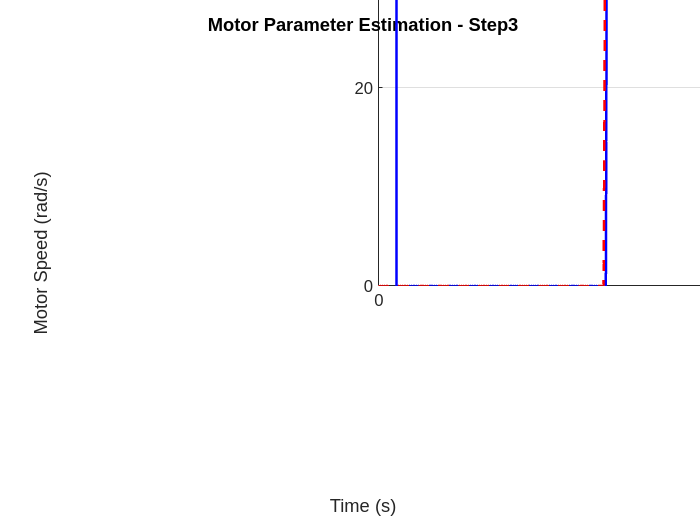

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.052337e+07    0.000e+00    2.061e+07
Poles of the system:
 -907.9809
   -0.6325

Poles of the system:
 -907.9809
   -0.6325

Poles of the system:
 -907.9810
   -0.6325

Poles of the system:
 -907.9809
   -0.6325

Poles of the system:
 -907.9809
   -0.6325

    1      10    3.799562e+06    0.000e+00    2.265e+10    4.302e-04
Poles of the system:
 -908.6128
   -0.0006

Poles of the system:
 -908.4612
   -0.1522

Poles of the system:
 -908.2649
   -0.3485

Poles of the system:
 -908.2649
   -0.3485

Poles of the system:
 -908.2649
   -0.3485

Poles of the system:
 -908.2649
   -0.3485

Poles of the system:
 -908.2649
 

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    2.499029e+05    0.000e+00    3.091e+05
Poles of the system:
 -907.9570
   -0.6565

Poles of the system:
 -907.9570
   -0.6565

Poles of the system:
 -907.9570
   -0.6564

Poles of the system:
 -907.9570
   -0.6565

Poles of the system:
 -907.9570
   -0.6565

    1      10    9.438632e+04    0.000e+00    2.230e+08    1.381e-03
Poles of the system:
 -908.6127
   -0.0005

Poles of the system:
 -908.3107
   -0.3027

Poles of the system:
 -908.1277
   -0.4857

Poles of the system:
 -908.0404
   -0.5730

Poles of the system:
 -908.0404
   -0.5730

Poles of the system:
 -908.0404
   -0.5730

Poles of the system:
 -908.0404
 

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    3.243812e+01    0.000e+00    3.176e+01
Poles of the system:
 -908.0835
   -0.6293

Poles of the system:
 -908.0430
   -0.6697

Poles of the system:
 -908.0430
   -0.6697

Poles of the system:
 -908.0431
   -0.6697

Poles of the system:
 -908.0430
   -0.6697

Poles of the system:
 -908.0430
   -0.6697

    1      11    1.891085e+01    0.000e+00    1.402e+05    2.440e-01
Poles of the system:
 -907.8296
   -0.8799

Poles of the system:
 -907.9384
   -0.7726

Poles of the system:
 -907.9384
   -0.7726

Poles of the system:
 -907.9384
   -0.7726

Poles of the system:
 -907.9384
   -0.7726

Poles of the system:
 -907.9384
 

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    7.702989e-02    0.000e+00    1.508e-01
Poles of the system:
 -908.4365
   -0.2788

Poles of the system:
 -908.3077
   -0.4050

Poles of the system:
 -908.3077
   -0.4050

Poles of the system:
 -908.3077
   -0.4050

Poles of the system:
 -908.3077
   -0.4051

Poles of the system:
 -908.3077
   -0.4050

    1      11    5.622256e-02    0.000e+00    1.723e+03    7.644e-02
Poles of the system:
 -908.6032
   -0.1049

Poles of the system:
 -908.5292
   -0.1806

Poles of the system:
 -908.4460
   -0.2650

Poles of the system:
 -908.4460
   -0.2650

Poles of the system:
 -908.4460
   -0.2650

Poles of the system:
 -908.4460
 

Poles of the system:
 -908.1619
   -0.5700



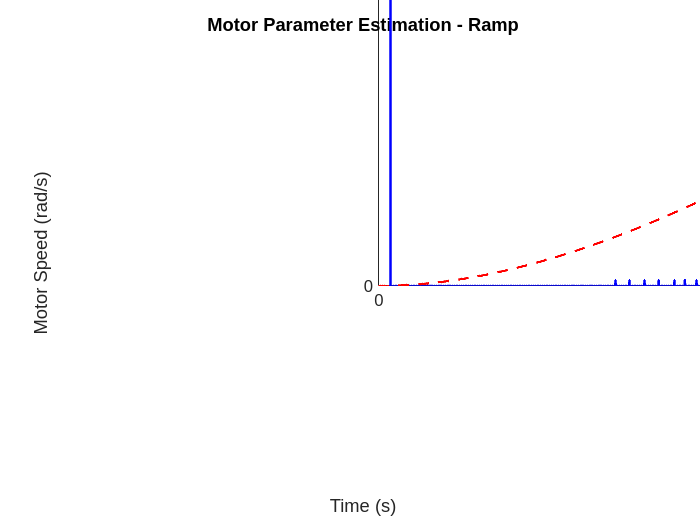

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    2.196932e+07    0.000e+00    4.477e+07
Poles of the system:
 -855.9999
  -65.3691

Poles of the system:
 -907.8372
   -0.9385

Poles of the system:
 -907.8372
   -0.9385

Poles of the system:
 -907.8372
   -0.9385

Poles of the system:
 -907.8372
   -0.9386

Poles of the system:
 -907.8372
   -0.9385

    1      11    8.448677e+06    0.000e+00    1.227e+11    1.459e-01
Poles of the system:
 -898.6683
  -10.3145

Poles of the system:
 -906.0994
   -2.7186

Poles of the system:
 -907.2332
   -1.5573

Poles of the system:
 -907.2332
   -1.5573

Poles of the system:
 -907.2333
   -1.5573

Poles of the system:
 -907.2332
 

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    3.901905e+05    0.000e+00    4.947e+05
Poles of the system:
 -907.9862
   -0.6272

Poles of the system:
 -907.9862
   -0.6272

Poles of the system:
 -907.9862
   -0.6272

Poles of the system:
 -907.9862
   -0.6272

Poles of the system:
 -907.9862
   -0.6272

    1      10    2.358441e+05    0.000e+00    7.548e+08    8.161e-04
Poles of the system:
   1.0e+02 *

  -4.5435 + 2.4440i
  -4.5435 - 2.4440i

Poles of the system:
 -906.6445
   -1.9693

Poles of the system:
 -906.6445
   -1.9693

Poles of the system:
 -906.6446
   -1.9692

Poles of the system:
 -906.6445
   -1.9694

Poles of the system:
 -906.6445
   -1.9693

 

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    4.686910e+01    0.000e+00    4.775e+01
Poles of the system:
 -908.0783
   -0.6344

Poles of the system:
 -908.0411
   -0.6717

Poles of the system:
 -908.0411
   -0.6717

Poles of the system:
 -908.0411
   -0.6717

Poles of the system:
 -908.0411
   -0.6717

Poles of the system:
 -908.0411
   -0.6717

    1      11    3.269237e+01    0.000e+00    2.681e+05    2.440e-01
Poles of the system:
 -900.2680
   -8.5561

Poles of the system:
 -906.3528
   -2.3916

Poles of the system:
 -906.3528
   -2.3916

Poles of the system:
 -906.3528
   -2.3915

Poles of the system:
 -906.3528
   -2.3916

Poles of the system:
 -906.3528
 

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    7.265327e-02    0.000e+00    1.480e-01
Poles of the system:
 -908.1251
   -0.5912

Poles of the system:
 -908.2937
   -0.4191

Poles of the system:
 -908.1967
   -0.5160

Poles of the system:
 -908.1967
   -0.5160

Poles of the system:
 -908.1967
   -0.5160

Poles of the system:
 -908.1967
   -0.5161

Poles of the system:
 -908.1967
   -0.5160

    1      12    3.977158e-02    0.000e+00    3.858e+02    3.757e-02
Poles of the system:
 -899.6976
   -9.2890

Poles of the system:
 -907.0668
   -1.6903

Poles of the system:
 -907.0668
   -1.6903

Poles of the system:
 -907.0669
   -1.6903

Poles of the system:
 -907.0668
 

Poles of the system:
 -906.1547
   -2.7315



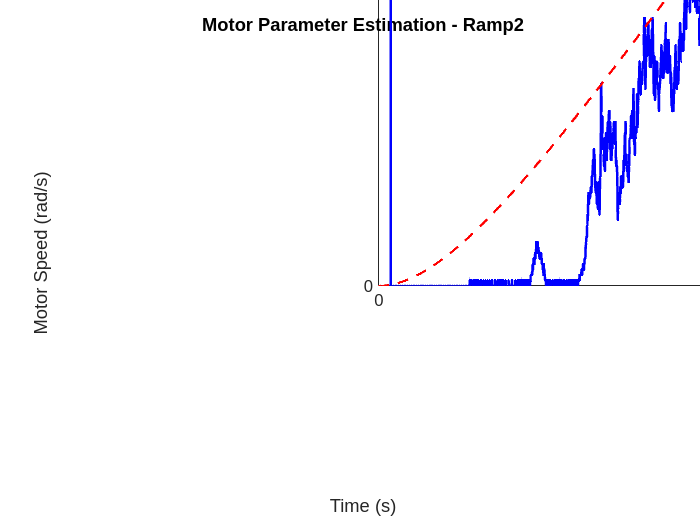

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    3.820919e+07    0.000e+00    5.951e+07
Poles of the system:
 -776.9611
 -145.8666

Poles of the system:
 -776.9610
 -145.8667

Poles of the system:
 -777.4422
 -145.3432

Poles of the system:
 -776.9605
 -145.8702

Poles of the system:
 -776.9611
 -145.8666

    1      10    1.742223e+07    0.000e+00    2.807e+11    2.754e-01
Poles of the system:
   1.0e+02 *

  -4.5993 + 6.6731i
  -4.5993 - 6.6731i

Poles of the system:
   1.0e+02 *

  -4.6226 + 3.5615i
  -4.6226 - 3.5615i

Poles of the system:
 -509.2547
 -414.4185

Poles of the system:
 -509.2537
 -414.4195

Poles of the system:
 -515.2417
 -408.3867

Poles of the 

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    4.619034e+05    0.000e+00    5.854e+05
Poles of the system:
 -908.0260
   -0.5874

Poles of the system:
 -908.0260
   -0.5874

Poles of the system:
 -908.0260
   -0.5874

Poles of the system:
 -908.0260
   -0.5874

Poles of the system:
 -908.0260
   -0.5874

    1      10    3.591158e+05    0.000e+00    2.238e+09    6.149e-04
Poles of the system:
   1.0e+02 *

  -4.5435 + 1.8800i
  -4.5435 - 1.8800i

Poles of the system:
   1.0e+02 *

  -4.5435 + 1.8800i
  -4.5435 - 1.8800i

Poles of the system:
   1.0e+02 *

  -4.5435 + 1.8572i
  -4.5435 - 1.8572i

Poles of the system:
   1.0e+02 *

  -4.5435 + 1.8801i
  -4.5435 - 1.

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    6.181049e+01    0.000e+00    4.813e+01
Poles of the system:
 -908.0779
   -0.6348

Poles of the system:
 -908.0410
   -0.6718

Poles of the system:
 -908.0410
   -0.6718

Poles of the system:
 -908.0410
   -0.6718

Poles of the system:
 -908.0410
   -0.6718

Poles of the system:
 -908.0410
   -0.6718

    1      11    5.388533e+01    0.000e+00    3.062e+05    2.440e-01
Poles of the system:
 -902.8764
   -5.8726

Poles of the system:
 -902.8764
   -5.8726

Poles of the system:
 -902.8767
   -5.8724

Poles of the system:
 -902.8764
   -5.8727

Poles of the system:
 -902.8764
   -5.8726

    2      16    5.067620e+01    

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    8.866781e-02    0.000e+00    1.381e-01
Poles of the system:
 -905.4442
   -3.2735

Poles of the system:
 -908.2359
   -0.4769

Poles of the system:
 -908.1718
   -0.5409

Poles of the system:
 -908.1718
   -0.5409

Poles of the system:
 -908.1719
   -0.5409

Poles of the system:
 -908.1718
   -0.5410

Poles of the system:
 -908.1718
   -0.5409

    1      12    6.816134e-02    0.000e+00    4.954e+02    3.520e-02
Poles of the system:
 -831.9399
  -77.7479

Poles of the system:
 -906.3402
   -2.4052

Poles of the system:
 -906.3402
   -2.4052

Poles of the system:
 -906.3403
   -2.4051

Poles of the system:
 -906.3402
 

Poles of the system:
 -901.3213
   -7.2982



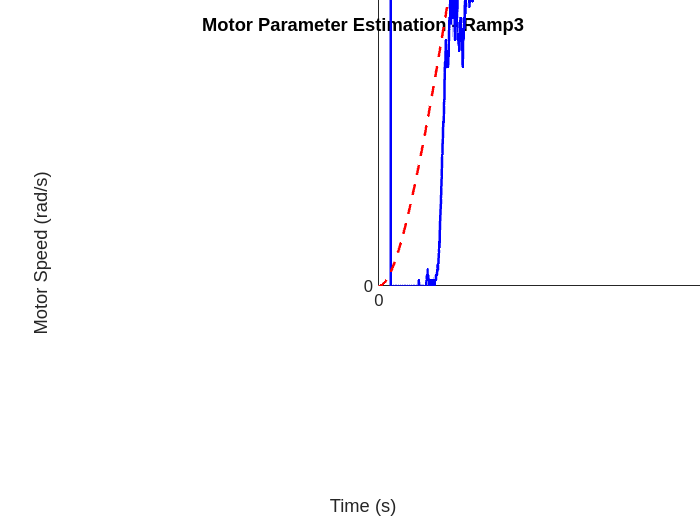

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.759557e+08    0.000e+00    4.226e+09
Poles of the system:
   1.0e+02 *

  -4.6449 + 5.9218i
  -4.6449 - 5.9218i

Poles of the system:
   1.0e+02 *

  -4.6449 + 5.9218i
  -4.6449 - 5.9218i

Poles of the system:
   1.0e+02 *

  -4.6446 + 5.9078i
  -4.6446 - 5.9078i

Poles of the system:
   1.0e+02 *

  -4.6449 + 5.9218i
  -4.6449 - 5.9218i

Poles of the system:
   1.0e+02 *

  -4.6449 + 5.9218i
  -4.6449 - 5.9218i

    1      10    7.728084e+07    0.000e+00    2.374e+11    2.160e-01
Poles of the system:
 -850.8377
  -59.0498

Poles of the system:
 -850.8377
  -59.0498

Poles of the system:
 -850.8493
  -59.0380

Poles

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.133405e+06    0.000e+00    1.545e+07
Poles of the system:
   1.0e+02 *

  -4.6454 + 6.0069i
  -4.6454 - 6.0069i

Poles of the system:
   1.0e+02 *

  -4.6454 + 6.0069i
  -4.6454 - 6.0069i

Poles of the system:
   1.0e+02 *

  -4.6451 + 5.9929i
  -4.6451 - 5.9929i

Poles of the system:
   1.0e+02 *

  -4.6454 + 6.0069i
  -4.6454 - 6.0069i

Poles of the system:
   1.0e+02 *

  -4.6454 + 6.0069i
  -4.6454 - 6.0069i

    1      10    7.914622e+05    0.000e+00    1.298e+09    2.152e-01
Poles of the system:
 -746.9522
 -164.8166

Poles of the system:
 -746.9521
 -164.8166

Poles of the system:
 -747.0474
 -164.7199

Poles

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.326417e+02    0.000e+00    1.593e+03
Poles of the system:
   1.0e+03 *

  -0.4545 + 1.8721i
  -0.4545 - 1.8721i

Poles of the system:
   1.0e+02 *

  -4.5442 + 5.3414i
  -4.5442 - 5.3414i

Poles of the system:
 -786.4696
 -122.2940

Poles of the system:
 -786.4696
 -122.2940

Poles of the system:
 -786.4720
 -122.2915

Poles of the system:
 -786.4696
 -122.2940

Poles of the system:
 -786.4696
 -122.2940

    1      12    1.292376e+02    0.000e+00    8.977e+03    5.750e-01
Poles of the system:
 -801.2902
 -107.6035

Poles of the system:
 -801.2902
 -107.6035

Poles of the system:
 -801.2924
 -107.6013

Poles of the 

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    8.881430e-01    0.000e+00    2.133e+01
Poles of the system:
 -901.4423
   -7.4011

Poles of the system:
 -901.4423
   -7.4011

Poles of the system:
 -901.4425
   -7.4010

Poles of the system:
 -901.4423
   -7.4011

Poles of the system:
 -901.4423
   -7.4011

    1      10    5.328430e-01    0.000e+00    1.072e+02    1.635e-01
Poles of the system:
   1.0e+03 *

  -0.4930 + 1.7725i
  -0.4930 - 1.7725i

Poles of the system:
 -884.3981
  -24.8291

Poles of the system:
 -896.0841
  -12.8877

Poles of the system:
 -896.0841
  -12.8877

Poles of the system:
 -896.0844
  -12.8874

Poles of the system:
 -896.0841
  -12.8877

P

Poles of the system:
   1.0e+03 *

  -0.4557 + 2.7513i
  -0.4557 - 2.7513i



Poles of the system:
   1.0e+03 *

  -0.4557 + 2.7513i
  -0.4557 - 2.7513i



Poles of the system:
   1.0e+03 *

  -0.4557 + 2.7513i
  -0.4557 - 2.7513i



Poles of the system:
   1.0e+03 *

  -0.4557 + 2.7513i
  -0.4557 - 2.7513i



   19     102    9.997847e-01    0.000e+00    1.038e-01    2.464e+02
Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0559i
  -0.4557 - 3.0559i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0559i
  -0.4557 - 3.0559i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0559i
  -0.4557 - 3.0559i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0559i
  -0.4557 - 3.0559i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0559i
  -0.4557 - 3.0559i



   20     107    9.998218e-01    0.000e+00    2.574e-02    9.514e+01
Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0713i
  -0.4557 - 3.0713i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0713i
  -0.4557 - 3.0713i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0713i
  -0.4557 - 3.0713i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0713i
  -0.4557 - 3.0713i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0713i
  -0.4557 - 3.0713i



   21     112    9.998234e-01    0.000e+00    3.499e-04    5.223e+00
Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0349i
  -0.4557 - 3.0349i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0349i
  -0.4557 - 3.0349i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0349i
  -0.4557 - 3.0349i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0349i
  -0.4557 - 3.0349i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.0349i
  -0.4557 - 3.0349i



   22     117    9.998130e-01    0.000e+00    3.981e-05    3.120e+01
Poles of the system:
   1.0e+03 *

  -0.4557 + 3.3448i
  -0.4557 - 3.3448i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.3448i
  -0.4557 - 3.3448i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.3448i
  -0.4557 - 3.3448i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.3448i
  -0.4557 - 3.3448i



Poles of the system:
   1.0e+03 *

  -0.4557 + 3.3448i
  -0.4557 - 3.3448i



   23     122    9.996729e-01    0.000e+00    3.984e-05    2.257e+02
Poles of the system:
   1.0e+03 *

  -0.4557 + 1.2835i
  -0.4557 - 1.2835i

Poles of the system:
   1.0e+03 *

  -0.4557 + 1.2835i
  -0.4557 - 1.2835i

Poles of the system:
   1.0e+03 *

  -0.4557 + 1.2835i
  -0.4557 - 1.2835i

Poles of the system:
   1.0e+03 *

  -0.4557 + 1.2835i
  -0.4557 - 1.2835i

Poles of the system:
   1.0e+03 *

  -0.4557 + 1.2835i
  -0.4557 - 1.2835i

   24     127    9.980219e-01    0.000e+00    4.115e-05    2.515e+02
Poles of the system:
 -897.1163
  -14.0911

Poles of the system:
 -897.1163
  -14.0911

Poles of the system:
 -897.1164
  -14.0910

Poles of the system:
 -897.1163
  -14.0911

Poles of the system:
 -897.1163
  -14.0911

   25     132    7.101757e-01    0.000e+00    9.766e+00    4.955e+01
Poles of the system:
 -907.4505
   -1.3130

Poles of the system:
 -907.4505
   -1.3130

Poles of the system:
 -907.4506
   -1.3129

Poles of the system:
 -907.4505
   -1.3131

Poles of the syst

Poles of the system:
 -899.4236
   -9.5856



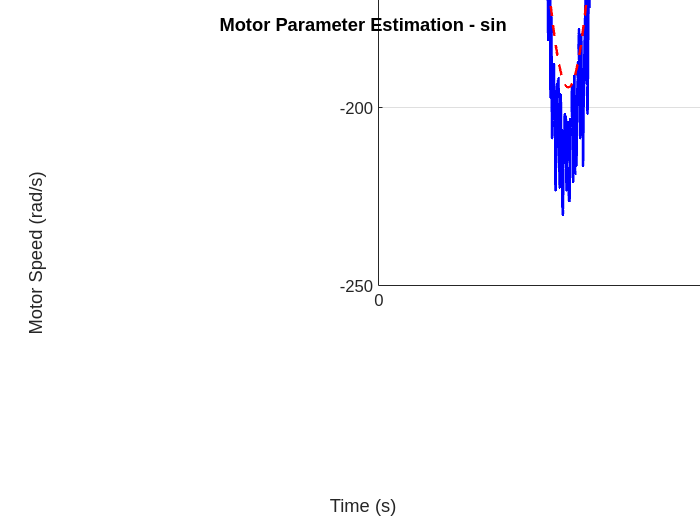

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.786174e+08    0.000e+00    7.701e+08
Poles of the system:
   1.0e+02 *

  -4.6435 + 5.6928i
  -4.6435 - 5.6928i

Poles of the system:
   1.0e+02 *

  -4.6435 + 5.6928i
  -4.6435 - 5.6928i

Poles of the system:
   1.0e+02 *

  -4.6432 + 5.6790i
  -4.6432 - 5.6790i

Poles of the system:
   1.0e+02 *

  -4.6435 + 5.6929i
  -4.6435 - 5.6929i

Poles of the system:
   1.0e+02 *

  -4.6435 + 5.6928i
  -4.6435 - 5.6928i

    1      10    1.508202e+08    0.000e+00    8.126e+11    2.182e-01
Poles of the system:
   1.0e+03 *

  -0.4582 + 2.8168i
  -0.4582 - 2.8168i



Poles of the system:
   1.0e+03 *

  -0.4594 + 2.2737i
  -0.4594 - 2.2737i



Poles of the system:
   1.0e+03 *

  -0.4608 + 1.6749i
  -0.4608 - 1.6749i

Poles of the system:
   1.0e+03 *

  -0.4621 + 1.2273i
  -0.4621 - 1.2273i

Poles of the system:
   1.0e+02 *

  -4.6306 + 9.3885i
  -4.6306 - 9.3885i

Poles of the system:
   1.0e+02 *

  -4.6365 + 7.6846i
  -4.6365 - 7.6846i

Poles of the system:
   1.0e+02 *

  -4.6365 + 7.6846i
  -4.6365 - 7.6846i

Poles of the system:
   1.0e+02 *

  -4.6363 + 7.6705i
  -4.6363 - 7.6705i

Poles of the system:
   1.0e+02 *

  -4.6365 + 7.6846i
  -4.6365 - 7.6846i

Poles of the system:
   1.0e+02 *

  -4.6365 + 7.6846i
  -4.6365 - 7.6846i

    2      20    1.501237e+08    0.000e+00    3.914e+11    3.109e-02
Poles of the system:
 -842.0047
  -66.6238

Poles of the system:
 -842.0047
  -66.6238

Poles of the system:
 -842.0378
  -66.5907

Poles of the system:
 -842.0047
  -66.6243

Poles of the system:
 -842.0047
  -66.6238

    3      25    1.209964e+08    0.000e+00    1.358e+12    1.119e-01
Poles of the system:
 -907.8892
  

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.144953e+06    0.000e+00    2.595e+06
Poles of the system:
   1.0e+02 *

  -4.6436 + 5.7001i
  -4.6436 - 5.7001i

Poles of the system:
   1.0e+02 *

  -4.6436 + 5.7001i
  -4.6436 - 5.7001i

Poles of the system:
   1.0e+02 *

  -4.6433 + 5.6862i
  -4.6433 - 5.6862i

Poles of the system:
   1.0e+02 *

  -4.6436 + 5.7001i
  -4.6436 - 5.7001i

Poles of the system:
   1.0e+02 *

  -4.6436 + 5.7001i
  -4.6436 - 5.7001i

    1      10    1.096961e+06    0.000e+00    2.975e+09    2.181e-01
Poles of the system:
   1.0e+03 *

  -0.4601 + 4.2463i
  -0.4601 - 4.2463i



Poles of the system:
   1.0e+03 *

  -0.4613 + 2.9754i
  -0.4613 - 2.9754i



Poles of the system:
   1.0e+03 *

  -0.4624 + 2.0063i
  -0.4624 - 2.0063i

Poles of the system:
   1.0e+03 *

  -0.4632 + 1.3808i
  -0.4632 - 1.3808i

Poles of the system:
   1.0e+03 *

  -0.4632 + 1.3808i
  -0.4632 - 1.3808i

Poles of the system:
   1.0e+03 *

  -0.4632 + 1.3788i
  -0.4632 - 1.3788i

Poles of the system:
   1.0e+03 *

  -0.4632 + 1.3808i
  -0.4632 - 1.3808i

Poles of the system:
   1.0e+03 *

  -0.4632 + 1.3808i
  -0.4632 - 1.3808i

    2      18    1.096427e+06    0.000e+00    2.947e+08    1.252e-01
Poles of the system:
   1.0e+02 *

  -4.5623 + 6.4744i
  -4.5623 - 6.4744i

Poles of the system:
   1.0e+02 *

  -4.5623 + 6.4744i
  -4.5623 - 6.4744i

Poles of the system:
   1.0e+02 *

  -4.5623 + 6.4711i
  -4.5623 - 6.4711i

Poles of the system:
   1.0e+02 *

  -4.5624 + 6.4744i
  -4.5624 - 6.4744i

Poles of the system:
   1.0e+02 *

  -4.5623 + 6.4744i
  -4.5623 - 6.4744i

    3      23    1.085608e+06    0.000e+00    3.099e+08    2.994e-01
Poles of the system:
 -906

Poles of the system:
   1.0e+02 *

  -4.5432 + 3.0284i
  -4.5432 - 3.0284i

Poles of the system:
 -866.9929
  -41.6287

Poles of the system:
 -890.8981
  -17.7202

Poles of the system:
 -890.8981
  -17.7202

Poles of the system:
 -890.9050
  -17.7133

Poles of the system:
 -890.8981
  -17.7206

Poles of the system:
 -890.8981
  -17.7202

   10      70    8.160279e+05    0.000e+00    1.352e+09    2.261e-02
Poles of the system:
 -900.3292
   -8.2844

Poles of the system:
 -900.3292
   -8.2844

Poles of the system:
 -900.3307
   -8.2829

Poles of the system:
 -900.3292
   -8.2846

Poles of the system:
 -900.3292
   -8.2844

   11      75    7.544139e+05    0.000e+00    3.349e+09    1.140e-01
Poles of the system:
 -904.1069
   -4.5060

Poles of the system:
 -902.0655
   -6.5476

Poles of the system:
 -901.0341
   -7.5791

Poles of the system:
 -901.0340
   -7.5791

Poles of the system:
 -901.0348
   -7.5784

Poles of the system:
 -901.0341
   -7.5792

Poles of the system:
 -901.0341
   -7.

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.336412e+02    0.000e+00    2.881e+02
Poles of the system:
   1.0e+03 *

  -0.4544 + 1.2963i
  -0.4544 - 1.2963i

Poles of the system:
   1.0e+02 *

  -4.5438 + 1.9761i
  -4.5438 - 1.9761i

Poles of the system:
 -850.8854
  -57.8467

Poles of the system:
 -850.8854
  -57.8467

Poles of the system:
 -850.8865
  -57.8457

Poles of the system:
 -850.8854
  -57.8467

Poles of the system:
 -850.8854
  -57.8467

    1      12    1.280300e+02    0.000e+00    9.208e+03    4.047e-01
Poles of the system:
 -879.4199
  -29.2795

Poles of the system:
 -879.4199
  -29.2795

Poles of the system:
 -879.4203
  -29.2791

Poles of the 

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    9.176662e-01    0.000e+00    3.957e+00
Poles of the system:
 -697.3901
 -219.5320

Poles of the system:
 -697.3900
 -219.5321

Poles of the system:
 -697.7657
 -219.1462

Poles of the system:
 -697.3895
 -219.5338

Poles of the system:
 -697.3901
 -219.5320

    1      10    7.304651e-01    0.000e+00    6.419e+03    9.819e-02
Poles of the system:
   1.0e+02 *

  -4.5440 + 2.4479i
  -4.5440 - 2.4479i

Poles of the system:
 -717.0123
 -191.9424

Poles of the system:
 -796.2581
 -113.0012

Poles of the system:
 -818.1542
  -91.6495

Poles of the system:
 -818.1542
  -91.6495

Poles of the system:
 -818.1719
  -91.6316

P

Poles of the system:
 -902.2017
   -7.0546



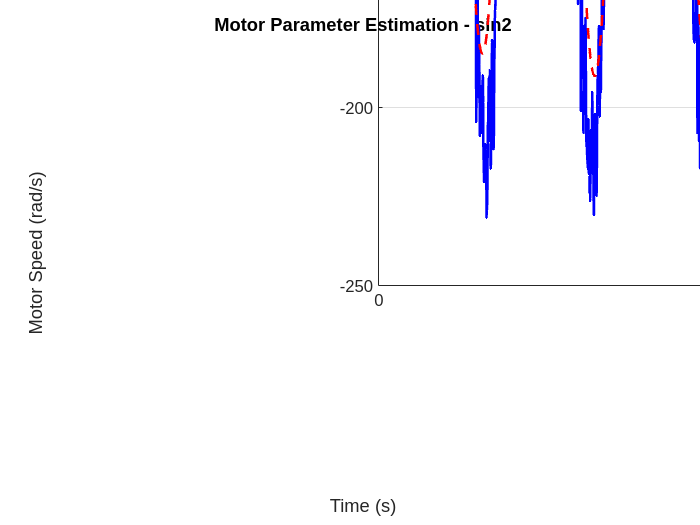

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.659319e+08    0.000e+00    2.175e+08
Poles of the system:
   1.0e+02 *

  -4.6431 + 5.6159i
  -4.6431 - 5.6159i

Poles of the system:
 -905.9116
   -2.9002

Poles of the system:
 -905.9116
   -2.9002

Poles of the system:
 -905.9117
   -2.9001

Poles of the system:
 -905.9116
   -2.9002

Poles of the system:
 -905.9116
   -2.9002

    1      11    1.397621e+08    0.000e+00    4.179e+08    1.095e-01
Poles of the system:
   1.0e+03 *

  -0.4740 + 2.9710i
  -0.4740 - 2.9710i



Poles of the system:
   1.0e+02 *

  -4.5801 + 4.6907i
  -4.5801 - 4.6907i

Poles of the system:
 -895.8227
  -13.1770

Poles of the system:
 -895.8227
  -13.1770

Poles of the system:
 -895.8235
  -13.1762

Poles of the system:
 -895.8227
  -13.1770

Poles of the system:
 -895.8227
  -13.1770

    2      18    1.094988e+08    0.000e+00    4.749e+06    8.338e-02
Poles of the system:
 -864.8957
  -44.9663

Poles of the system:
 -890.1709
  -18.9733

Poles of the system:
 -893.5578
  -15.4961

Poles of the system:
 -893.5578
  -15.4961

Poles of the system:
 -893.5589
  -15.4950

Poles of the system:
 -893.5578
  -15.4962

Poles of the system:
 -893.5578
  -15.4961

    3      25    1.068672e+08    0.000e+00    9.365e+10    7.700e-02
Poles of the system:
   1.0e+02 *

  -4.6621 + 1.9041i
  -4.6621 - 1.9041i

Poles of the system:
 -895.1588
  -14.0115

Poles of the system:
 -895.1588
  -14.0115

Poles of the system:
 -895.1607
  -14.0095

Poles of the system:
 -895.1588
  -14.0117

Poles 

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.097569e+06    0.000e+00    7.398e+05
Poles of the system:
   1.0e+02 *

  -4.6432 + 5.6323i
  -4.6432 - 5.6323i

Poles of the system:
 -905.9051
   -2.9068

Poles of the system:
 -905.9051
   -2.9068

Poles of the system:
 -905.9052
   -2.9067

Poles of the system:
 -905.9051
   -2.9068

Poles of the system:
 -905.9051
   -2.9068

    1      11    1.005787e+06    0.000e+00    1.495e+06    1.094e-01
Poles of the system:
   1.0e+03 *

  -0.4740 + 3.0226i
  -0.4740 - 3.0226i



Poles of the system:
   1.0e+03 *

  -0.4686 + 1.2108i
  -0.4686 - 1.2108i

Poles of the system:
 -895.4383
  -13.5690

Poles of the system:
 -895.4383
  -13.5690

Poles of the system:
 -895.4391
  -13.5682

Poles of the system:
 -895.4383
  -13.5691

Poles of the system:
 -895.4383
  -13.5690

    2      18    8.978773e+05    0.000e+00    7.537e+07    8.501e-02
Poles of the system:
 -898.2245
  -10.6077

Poles of the system:
 -898.2245
  -10.6077

Poles of the system:
 -898.2248
  -10.6074

Poles of the system:
 -898.2245
  -10.6078

Poles of the system:
 -898.2245
  -10.6077

    3      23    8.973581e+05    0.000e+00    1.468e+08    3.044e-01
Poles of the system:
 -898.2232
  -10.6087

Poles of the system:
 -898.2232
  -10.6087

Poles of the system:
 -898.2235
  -10.6084

Poles of the system:
 -898.2232
  -10.6088

Poles of the system:
 -898.2232
  -10.6087

    4      28    8.973171e+05    0.000e+00    1.466e+08    1.522e-03
Poles of the system:
   1.0e+02 *

  -4.6793 + 1.4468i
  

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.288081e+02    0.000e+00    8.440e+01
Poles of the system:
   1.0e+02 *

  -4.5442 + 9.5127i
  -4.5442 - 9.5127i

Poles of the system:
 -709.8702
 -198.8812

Poles of the system:
 -875.5240
  -33.2050

Poles of the system:
 -875.5240
  -33.2050

Poles of the system:
 -875.5246
  -33.2044

Poles of the system:
 -875.5240
  -33.2050

Poles of the system:
 -875.5240
  -33.2050

    1      12    1.252566e+02    0.000e+00    1.272e+04    3.084e-01
Poles of the system:
 -900.4440
   -8.2179

Poles of the system:
 -900.4440
   -8.2179

Poles of the system:
 -900.4441
   -8.2179

Poles of the system:
 -900.4440
   -8.2179

P

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    9.374511e-01    0.000e+00    1.229e+00
Poles of the system:
 -807.0581
 -107.7441

Poles of the system:
 -906.8308
   -1.9798

Poles of the system:
 -906.8308
   -1.9798

Poles of the system:
 -906.8309
   -1.9797

Poles of the system:
 -906.8308
   -1.9798

Poles of the system:
 -906.8308
   -1.9798

    1      11    8.357453e-01    0.000e+00    2.375e+02    3.676e-02
Poles of the system:
   1.0e+02 *

  -4.7411 + 7.1879i
  -4.7411 - 7.1879i

Poles of the system:
 -903.1747
   -5.8320

Poles of the system:
 -903.1747
   -5.8320

Poles of the system:
 -903.1750
   -5.8316

Poles of the system:
 -903.1747
   -5.8320

P

Poles of the system:
 -906.3133
   -2.3562



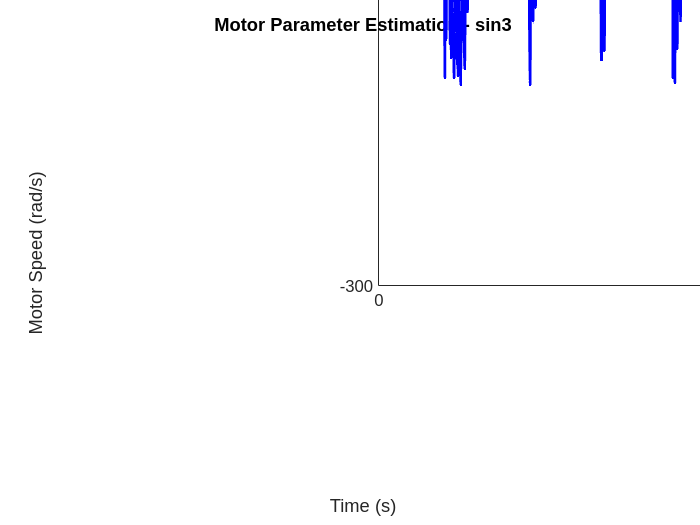

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    4.304805e+07    0.000e+00    1.261e+07
Poles of the system:
 -907.8467
   -0.7669

Poles of the system:
 -907.8467
   -0.7669

Poles of the system:
 -907.8467
   -0.7668

Poles of the system:
 -907.8467
   -0.7669

Poles of the system:
 -907.8467
   -0.7669

    1      10    3.753552e+07    0.000e+00    1.157e+10    5.738e-04
Poles of the system:
   1.0e+02 *

  -4.5435 + 1.2322i
  -4.5435 - 1.2322i

Poles of the system:
   1.0e+02 *

  -4.5435 + 1.2322i
  -4.5435 - 1.2322i

Poles of the system:
   1.0e+02 *

  -4.5434 + 1.1905i
  -4.5434 - 1.1905i

Poles of the system:
   1.0e+02 *

  -4.5435 + 1.2323i
  -4.5435 - 1.

Poles of the system:
   1.0e+03 *

  -0.4544 + 1.3393i
  -0.4544 - 1.3393i

Poles of the system:
   1.0e+02 *

  -4.5435 + 7.0625i
  -4.5435 - 7.0625i

Poles of the system:
   1.0e+02 *

  -4.5435 + 4.4797i
  -4.5435 - 4.4797i

Poles of the system:
   1.0e+03 *

  -0.4543 + 1.4186i
  -0.4543 - 1.4186i

Poles of the system:
   1.0e+02 *

  -4.5434 + 8.8797i
  -4.5434 - 8.8797i

Poles of the system:
   1.0e+02 *

  -4.5434 + 5.8242i
  -4.5434 - 5.8242i

Poles of the system:
   1.0e+02 *

  -4.5434 + 4.0085i
  -4.5434 - 4.0085i

Poles of the system:
   1.0e+02 *

  -4.5434 + 2.8929i
  -4.5434 - 2.8929i

Poles of the system:
   1.0e+02 *

  -4.5434 + 2.8929i
  -4.5434 - 2.8929i

Poles of the system:
   1.0e+02 *

  -4.5434 + 2.8700i
  -4.5434 - 2.8700i

Poles of the system:
   1.0e+02 *

  -4.5435 + 2.8929i
  -4.5435 - 2.8929i

Poles of the system:
   1.0e+02 *

  -4.5434 + 2.8929i
  -4.5434 - 2.8929i

    3      28    7.050592e+06    0.000e+00    1.600e+11    8.384e-03
Poles of the system

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    5.081065e+05    0.000e+00    4.913e+05
Poles of the system:
   1.0e+02 *

  -4.6346 + 4.0583i
  -4.6346 - 4.0583i

Poles of the system:
   1.0e+02 *

  -4.6346 + 4.0583i
  -4.6346 - 4.0583i

Poles of the system:
   1.0e+02 *

  -4.6343 + 4.0447i
  -4.6343 - 4.0447i

Poles of the system:
   1.0e+02 *

  -4.6346 + 4.0583i
  -4.6346 - 4.0583i

Poles of the system:
   1.0e+02 *

  -4.6346 + 4.0583i
  -4.6346 - 4.0583i

    1      10    2.155932e+05    0.000e+00    3.107e+08    2.338e-01
Poles of the system:
 -899.8649
   -9.0235

Poles of the system:
 -868.3391
  -41.9221

Poles of the system:
 -833.6802
  -77.9689

Poles

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    6.560774e+01    0.000e+00    9.611e+00
Poles of the system:
 -908.1161
   -0.5967

Poles of the system:
 -908.0553
   -0.6575

Poles of the system:
 -908.0553
   -0.6575

Poles of the system:
 -908.0553
   -0.6574

Poles of the system:
 -908.0553
   -0.6575

Poles of the system:
 -908.0553
   -0.6575

    1      11    6.102073e+01    0.000e+00    1.608e+04    2.441e-01
Poles of the system:
 -882.7654
  -26.0774

Poles of the system:
 -882.7654
  -26.0774

Poles of the system:
 -882.7677
  -26.0752

Poles of the system:
 -882.7654
  -26.0775

Poles of the system:
 -882.7654
  -26.0774

    2      16    4.850803e+01    

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    4.691420e-01    0.000e+00    1.375e-01
Poles of the system:
 -904.3081
   -4.4099

Poles of the system:
 -908.2189
   -0.4939

Poles of the system:
 -908.2189
   -0.4939

Poles of the system:
 -908.2189
   -0.4939

Poles of the system:
 -908.2189
   -0.4940

Poles of the system:
 -908.2189
   -0.4939

    1      11    4.110924e-01    0.000e+00    4.484e+02    6.994e-02
Poles of the system:
 -900.0184
   -8.7837

Poles of the system:
 -900.0184
   -8.7837

Poles of the system:
 -900.0189
   -8.7832

Poles of the system:
 -900.0184
   -8.7838

Poles of the system:
 -900.0184
   -8.7837

    2      16    2.524574e-01    

Poles of the system:
 -849.6483
  -60.2625



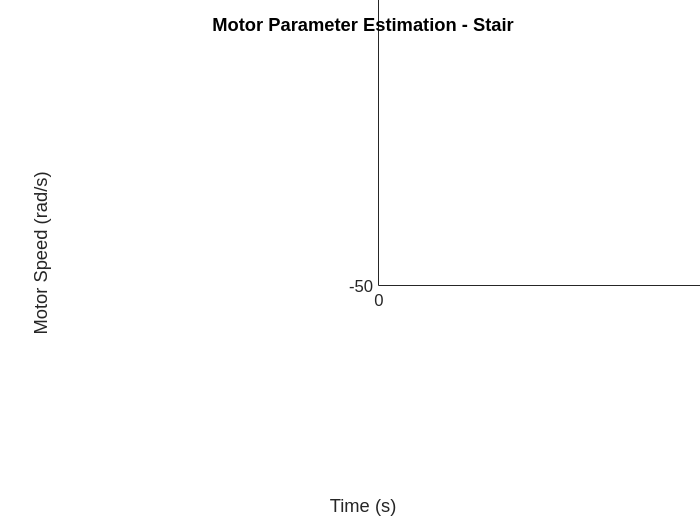

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    6.546736e+06    0.000e+00    1.755e+07
Poles of the system:
 -907.9682
   -0.6452

Poles of the system:
 -907.9682
   -0.6452

Poles of the system:
 -907.9682
   -0.6452

Poles of the system:
 -907.9682
   -0.6453

Poles of the system:
 -907.9682
   -0.6452

    1      10    9.302552e+05    0.000e+00    1.652e+10    4.427e-04
Poles of the system:
 -908.6128
   -0.0006

Poles of the system:
 -908.4576
   -0.1558

Poles of the system:
 -908.2573
   -0.3561

Poles of the system:
 -908.2573
   -0.3561

Poles of the system:
 -908.2573
   -0.3561

Poles of the system:
 -908.2573
   -0.3561

Poles of the system:
 -908.2573
 

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    2.011807e+05    0.000e+00    2.765e+05
Poles of the system:
 -907.9459
   -0.6675

Poles of the system:
 -907.9459
   -0.6675

Poles of the system:
 -907.9459
   -0.6675

Poles of the system:
 -907.9459
   -0.6675

Poles of the system:
 -907.9459
   -0.6675

    1      10    7.035152e+04    0.000e+00    5.012e+07    1.589e-03
Poles of the system:
 -907.9458
   -0.6670

Poles of the system:
 -908.0319
   -0.5815

Poles of the system:
 -907.9836
   -0.6298

Poles of the system:
 -907.9631
   -0.6503

Poles of the system:
 -907.9631
   -0.6503

Poles of the system:
 -907.9631
   -0.6503

Poles of the system:
 -907.9631
 

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    2.558531e+01    0.000e+00    3.430e+01
Poles of the system:
 -908.0824
   -0.6304

Poles of the system:
 -908.0426
   -0.6702

Poles of the system:
 -908.0426
   -0.6702

Poles of the system:
 -908.0426
   -0.6701

Poles of the system:
 -908.0426
   -0.6702

Poles of the system:
 -908.0426
   -0.6702

    1      11    9.268999e+00    0.000e+00    1.810e+05    2.440e-01
Poles of the system:
 -907.7081
   -1.0006

Poles of the system:
 -907.8805
   -0.8300

Poles of the system:
 -907.8805
   -0.8300

Poles of the system:
 -907.8805
   -0.8300

Poles of the system:
 -907.8805
   -0.8300

Poles of the system:
 -907.8805
 

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    5.878081e-02    0.000e+00    1.576e-01
Poles of the system:
 -908.4033
   -0.3121

Poles of the system:
 -908.3044
   -0.4084

Poles of the system:
 -908.3044
   -0.4084

Poles of the system:
 -908.3044
   -0.4084

Poles of the system:
 -908.3044
   -0.4084

Poles of the system:
 -908.3044
   -0.4084

    1      11    3.740962e-02    0.000e+00    1.693e+03    7.907e-02
Poles of the system:
 -908.6099
   -0.0982

Poles of the system:
 -908.5413
   -0.1685

Poles of the system:
 -908.4539
   -0.2572

Poles of the system:
 -908.4539
   -0.2572

Poles of the system:
 -908.4539
   -0.2572

Poles of the system:
 -908.4539
 

Poles of the system:
 -908.1350
   -0.5682



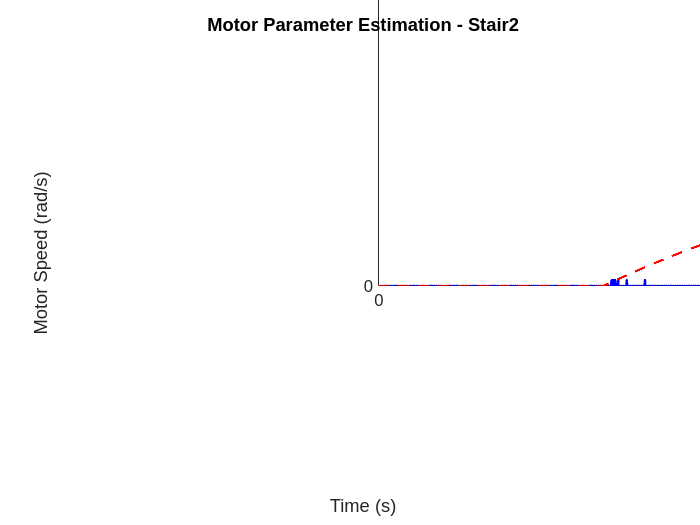

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    6.246600e+07    0.000e+00    2.234e+08
Poles of the system:
   1.0e+02 *

  -4.6305 + 3.1647i
  -4.6305 - 3.1647i

Poles of the system:
   1.0e+02 *

  -4.6305 + 3.1647i
  -4.6305 - 3.1647i

Poles of the system:
   1.0e+02 *

  -4.6302 + 3.1502i
  -4.6302 - 3.1502i

Poles of the system:
   1.0e+02 *

  -4.6305 + 3.1647i
  -4.6305 - 3.1647i

Poles of the system:
   1.0e+02 *

  -4.6305 + 3.1647i
  -4.6305 - 3.1647i

    1      10    2.114951e+07    0.000e+00    8.901e+10    2.415e-01
Poles of the system:
 -896.3355
  -12.7268

Poles of the system:
 -896.3355
  -12.7268

Poles of the system:
 -896.3365
  -12.7257

Poles

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    6.186280e+05    0.000e+00    1.547e+05
Poles of the system:
 -907.8629
   -0.7506

Poles of the system:
 -907.8629
   -0.7506

Poles of the system:
 -907.8629
   -0.7506

Poles of the system:
 -907.8629
   -0.7506

Poles of the system:
 -907.8629
   -0.7506

    1      10    5.398050e+05    0.000e+00    2.011e+08    3.438e-03
Poles of the system:
   1.0e+02 *

  -4.5438 + 6.9800i
  -4.5438 - 6.9800i

Poles of the system:
   1.0e+02 *

  -4.5438 + 6.9800i
  -4.5438 - 6.9800i

Poles of the system:
   1.0e+02 *

  -4.5438 + 6.9578i
  -4.5438 - 6.9578i

Poles of the system:
   1.0e+02 *

  -4.5438 + 6.9801i
  -4.5438 - 6.

Poles of the system:
   1.0e+02 *

  -4.5439 + 7.9196i
  -4.5439 - 7.9196i

Poles of the system:
   1.0e+02 *

  -4.5439 + 7.9196i
  -4.5439 - 7.9196i

Poles of the system:
   1.0e+02 *

  -4.5439 + 7.8729i
  -4.5439 - 7.8729i

Poles of the system:
   1.0e+02 *

  -4.5439 + 7.9196i
  -4.5439 - 7.9196i

Poles of the system:
   1.0e+02 *

  -4.5439 + 7.9196i
  -4.5439 - 7.9196i

    3      21    2.104418e+05    0.000e+00    5.897e+08    1.527e-01
Poles of the system:
 -794.5958
 -114.0180

Poles of the system:
   1.0e+02 *

  -4.5434 + 3.7349i
  -4.5434 - 3.7349i

Poles of the system:
   1.0e+02 *

  -4.5436 + 5.8996i
  -4.5436 - 5.8996i

Poles of the system:
   1.0e+02 *

  -4.5436 + 5.8996i
  -4.5436 - 5.8996i

Poles of the system:
   1.0e+02 *

  -4.5436 + 5.8621i
  -4.5436 - 5.8621i

Poles of the system:
   1.0e+02 *

  -4.5437 + 5.8996i
  -4.5437 - 5.8996i

Poles of the system:
   1.0e+02 *

  -4.5436 + 5.8996i
  -4.5436 - 5.8996i

    4      28    1.406616e+05    0.000e+00    9.274

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    7.903148e+01    0.000e+00    1.413e+02
Poles of the system:
   1.0e+03 *

  -0.4544 + 1.3030i
  -0.4544 - 1.3030i

Poles of the system:
   1.0e+02 *

  -4.5436 + 2.3747i
  -4.5436 - 2.3747i

Poles of the system:
 -845.6492
  -63.0636

Poles of the system:
 -893.1030
  -15.6098

Poles of the system:
 -888.9425
  -19.7496

Poles of the system:
   1.0e+02 *

  -4.6305 + 3.1654i
  -4.6305 - 3.1654i

Poles of the system:
   1.0e+02 *

  -4.6305 + 3.1654i
  -4.6305 - 3.1654i

Poles of the system:
   1.0e+02 *

  -4.6302 + 3.1510i
  -4.6302 - 3.1510i

Poles of the system:
   1.0e+02 *

  -4.6305 + 3.1655i
  -4.6305 - 3.1655i

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

Poles of the system:
 -908.1148
   -0.5980

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    3.783299e-01    0.000e+00    1.353e+00
Poles of the system:
   1.0e+02 *

  -4.5470 + 1.4309i
  -4.5470 - 1.4309i

Poles of the system:
   1.0e+02 *

  -4.5470 + 1.4309i
  -4.5470 - 1.4309i

Poles of the system:
   1.0e+02 *

  -4.5470 + 1.4148i
  -4.5470 - 1.4148i

Poles of the system:
   1.0e+02 *

  -4.5470 + 1.4309i
  -4.5470 - 1.4309i

Poles of the system:
   1.0e+02 *

  -4.5470 + 1.4309i
  -4.5470 - 1.4309i

    1      10    1.500948e-01    0.000e+00    5.832e+02    1.647e-01
Poles of the system:
 -908.6082
   -0.4280

Poles of the system:
 -852.9630
  -56.2045

Poles of the system:
 -756.2337
 -153.0319

Poles

Poles of the system:
 -894.5164
  -15.2437



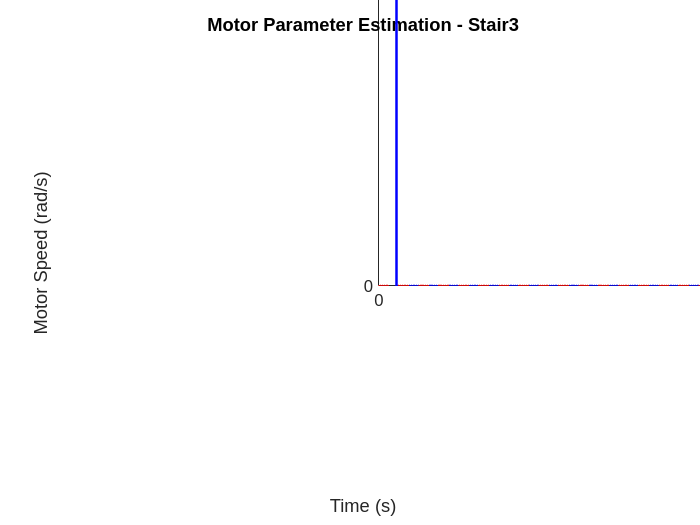


signals = {'Chirp', 'Chirp2', 'Chirp3', 'Step', 'Step2', 'Step3', 'Ramp', 'Ramp2', 'Ramp3', ...
           'sin', 'sin2', 'sin3', 'Stair', 'Stair2', 'Stair3'};

% Fixed motor parameters
Rm_fixed = 2.51186;   % Motor Resistance
Lm_fixed = 0.0027645; % Motor Inductance

% Optimization setup
params_init = [0.05, 0.001, 0.0001, 0.5]; % Initial values
lb = [1e-9, 1e-9, 1e-9, 0.01];  % Lower bound
ub = [Inf, Inf, Inf, 0.99];  % Upper bound
options = optimset('Display', 'iter', 'TolFun', 1e-9, 'TolX', 1e-9);

% Storage for estimated parameters
estimated_params_SSE = zeros(length(signals), 4);
estimated_params_Abs = zeros(length(signals), 4);
estimated_params_RMSE = zeros(length(signals), 4);
estimated_params_NMSE = zeros(length(signals), 4);

% Loop over all signals
for i = 1:length(signals)
    signal_name = signals{i};

    % Load input voltage (V) and measured speed (omega)
    V = eval(['V_input_', signal_name]);
    omega = eval(['omega_', signal_name]);

    t = eval(['Time_input_', signal_name]);

    % Ensure column vectors
    t = t(:); 
    V = V(:);
    omega = omega(:);

    estimated_params_SSE(i, :) = fmincon(@(p) cost_function_SSE(p, Rm_fixed, Lm_fixed, t, V, omega), ...
                               params_init, [], [], [], [], lb, ub, [], options);
    estimated_params_Abs(i, :) = fmincon(@(p) cost_function_absolute(p, Rm_fixed, Lm_fixed, t, V, omega), ...
                               params_init, [], [], [], [], lb, ub, [], options);
    estimated_params_RMSE(i, :) = fmincon(@(p) cost_function_rmse(p, Rm_fixed, Lm_fixed, t, V, omega), ...
                               params_init, [], [], [], [], lb, ub, [], options);
    estimated_params_NMSE(i, :) = fmincon(@(p) cost_function_nmse(p, Rm_fixed, Lm_fixed, t, V, omega), ...
                               params_init, [], [], [], [], lb, ub, [], options);

    omega_sim = motor_model(estimated_params_RMSE(i, :), Rm_fixed, Lm_fixed, t, V);

    figure;
    plot(t, omega, 'b', 'LineWidth', 1.5); hold on;
    plot(t, omega_sim, 'r--', 'LineWidth', 1.5);
    xlabel('Time (s)');
    ylabel('Motor Speed (rad/s)');
    legend('Measured', 'Estimated');
    title(['Motor Parameter Estimation - ', signal_name]);
    grid on;
end


resultsTable = array2table([estimated_params_SSE, estimated_params_Abs, estimated_params_RMSE, estimated_params_NMSE], ...
                           'VariableNames', {'Ke_SSE', 'Jm_SSE', 'Bm_SSE', 'Eff_SSE', ...
                                             'Ke_Abs', 'Jm_Abs', 'Bm_Abs', 'Eff_Abs', ...
                                             'Ke_RMSE', 'Jm_RMSE', 'Bm_RMSE', 'Eff_RMSE', ...
                                             'Ke_NMSE', 'Jm_NMSE', 'Bm_NMSE', 'Eff_NMSE'}, ...
                           'RowNames', signals);
disp(resultsTable);

               Ke_SSE        Jm_SSE        Bm_SSE      Eff_SSE     Ke_Abs        Jm_Abs        Bm_Abs      Eff_Abs     Ke_RMSE      Jm_RMSE       Bm_RMSE      Eff_RMSE     Ke_NMSE      Jm_NMSE       Bm_NMSE      Eff_NMSE
              _________    __________    __________    _______    _________    __________    __________    _______    _________    __________    __________    ________    _________    __________    __________    ________

    C

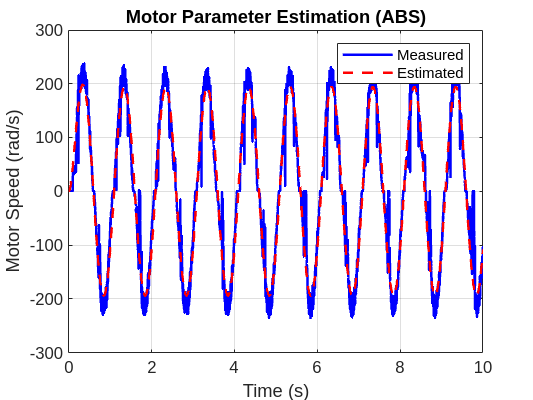

figure;
plot(t, omega, 'b', 'LineWidth', 1.5); hold on;
plot(t, omega_sim, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Motor Speed (rad/s)');
legend('Measured', 'Estimated');
title('Motor Parameter Estimation (ABS)');
grid on;

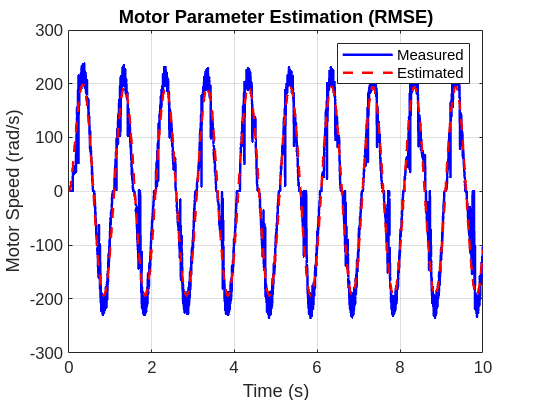

figure;
plot(t, omega, 'b', 'LineWidth', 1.5); hold on;
plot(t, omega_sim, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Motor Speed (rad/s)');
legend('Measured', 'Estimated');
title('Motor Parameter Estimation (RMSE)');
grid on;

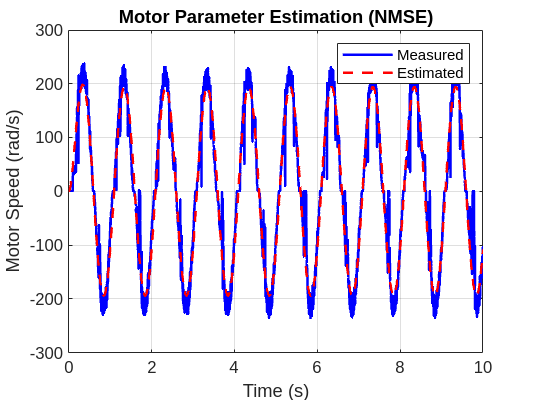

figure;
plot(t, omega, 'b', 'LineWidth', 1.5); hold on;
plot(t, omega_sim, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Motor Speed (rad/s)');
legend('Measured', 'Estimated');
title('Motor Parameter Estimation (NMSE)');
grid on;

x = omega(:);
y = omega_sim(:);

rmse = sqrt(mean((y - x).^2));
mae = mean(abs(y - x));
r_squared = 1 - sum((y - x).^2) / sum((y - mean(y)).^2);
correlation_coefficient = corr(x, y);

% Display Performance Metrics
fprintf('Performance Metrics (SSE):\n');

Performance Metrics (SSE):


fprintf('RMSE: %.4f\n', rmse);

RMSE: 29.4059


fprintf('MAE: %.4f\n', mae);

MAE: 20.2409


fprintf('R-squared: %.4f\n', r_squared);

R-squared: 0.9544


fprintf('Correlation Coefficient (r): %.4f\n', correlation_coefficient);

Correlation Coefficient (r): 0.9783


%%%

% V_input_Chirp = double(Chirp{1}{1}.Values.Data);
% V_input_Chirp2 = double(Chirp{2}{1}.Values.Data);
% V_input_Chirp3 = double(Chirp{3}{1}.Values.Data);
% V_input_Step = double(Step{1}{6}.Values.Data);
% V_input_Step2 = double(Step{2}{6}.Values.Data);
% 
% V_input_Step3 = double(Step{3}{6}.Values.Data);
% V_input_Ramp = double(Ramp{1}{3}.Values.Data);
% V_input_Ramp2 = double(Ramp{2}{3}.Values.Data);
% V_input_Ramp3 = double(Ramp{3}{3}.Values.Data);
% V_input_sin = double(SineWave{1}{3}.Values.Data);
% V_input_sin2 = double(SineWave{2}{3}.Values.Data);
% V_input_sin3 = double(SineWave{3}{3}.Values.Data);
% V_input_Stair = double(Stair{1}{5}.Values.Data);
% V_input_Stair2 = double(Stair{2}{5}.Values.Data);
% V_input_Stair3 = double(Stair{3}{5}.Values.Data);
% 
% using this function 
% 
% loop every input with each motor_Eff	motor_Ke	motor_J	motor_B 
% 
% to calculate RMSE R^2 MAE Correlation Coefficient

paramsTable = readtable('Lab1.csv');

disp(head(paramsTable));

    InputSignal    RMSE_Eff     RMSE_Ke      RMSE_Jm       RMSE_Bm      SSE_Eff     SSE_Ke        SSE_Jm        SSE_Bm      AbsError_Eff    AbsError_Ke    AbsError_Jm    AbsError_Bm    NMSE_Eff     NMSE_Ke      NMSE_Jm       NMSE_Bm  
    ___________    ________    _________    __________    __________    _______    _________    __________    __________    ____________    ___________    ___________    ___________    ________    _________    ___

Time_input_Chirp   = double(Chirp{1}{1}.Values.Time);
Time_input_Chirp2  = double(Chirp{2}{1}.Values.Time);
Time_input_Chirp3  = double(Chirp{3}{1}.Values.Time);
Time_input_Step    = double(Step{1}{6}.Values.Time);
Time_input_Step2   = double(Step{2}{6}.Values.Time);
Time_input_Step3   = double(Step{3}{6}.Values.Time);
Time_input_Ramp    = double(Ramp{1}{3}.Values.Time);
Time_input_Ramp2   = double(Ramp{2}{3}.Values.Time);
Time_input_Ramp3   = double(Ramp{3}{3}.Values.Time);
Time_input_sin     = double(SineWave{1}{3}.Values.Time);
Time_input_sin2    = double(SineWave{2}{3}.Values.Time);
Time_input_sin3    = double(SineWave{3}{3}.Values.Time);
Time_input_Stair   = double(Stair{1}{5}.Values.Time);
Time_input_Stair2  = double(Stair{2}{5}.Values.Time);
Time_input_Stair3  = double(Stair{3}{5}.Values.Time);

% Input voltage signals (from your Simulink or CSV file)
V_input_Chirp   = double(Chirp{1}{1}.Values.Data);
V_input_Chirp2  = double(Chirp{2}{1}.Values.Data);
V_input_Chirp3  = double(Chirp{3}{1}.Values.Data);
V_input_Step    = double(Step{1}{6}.Values.Data);
V_input_Step2   = double(Step{2}{6}.Values.Data);
V_input_Step3   = double(Step{3}{6}.Values.Data);
V_input_Ramp    = double(Ramp{1}{3}.Values.Data);
V_input_Ramp2   = double(Ramp{2}{3}.Values.Data);
V_input_Ramp3   = double(Ramp{3}{3}.Values.Data);
V_input_sin     = double(SineWave{1}{3}.Values.Data);
V_input_sin2    = double(SineWave{2}{3}.Values.Data);
V_input_sin3    = double(SineWave{3}{3}.Values.Data);
V_input_Stair   = double(Stair{1}{5}.Values.Data);
V_input_Stair2  = double(Stair{2}{5}.Values.Data);
V_input_Stair3  = double(Stair{3}{5}.Values.Data);

omega_Chirp = double(Chirp{1}{6}.Values.Data);
omega_Chirp2 = double(Chirp{2}{6}.Values.Data);
omega_Chirp3 = double(Chirp{3}{6}.Values.Data);
omega_Step   = double(Step{1}{8}.Values.Data);
omega_Step2    = double(Step{2}{8}.Values.Data);
omega_Step3    = double(Step{2}{8}.Values.Data);
omega_Ramp   = double(Ramp{1}{7}.Values.Data);
omega_Ramp2    = double(Ramp{2}{7}.Values.Data);
omega_Ramp3    = double(Ramp{3}{7}.Values.Data);
omega_sin    = double(SineWave{1}{6}.Values.Data);
omega_sin2    = double(SineWave{2}{6}.Values.Data);
omega_sin3    = double(SineWave{3}{6}.Values.Data);
omega_Stair    = double(Stair{1}{8}.Values.Data);
omega_Stair2    = double(Stair{2}{8}.Values.Data);
omega_Stair3    = double(Stair{3}{8}.Values.Data);

% Pack input signals into a cell array
inputSignals = {V_input_Chirp, V_input_Chirp2, V_input_Chirp3, ...
                V_input_Step, V_input_Step2, V_input_Step3, ...
                V_input_Ramp, V_input_Ramp2, V_input_Ramp3, ...
                V_input_sin, V_input_sin2, V_input_sin3, ...
                V_input_Stair, V_input_Stair2, V_input_Stair3};

% Pack corresponding measured velocities (adjust variable names as needed)
measuredOmega = {omega_Chirp, omega_Chirp2, omega_Chirp3, ...
                 omega_Step, omega_Step2, omega_Step3, ...
                 omega_Ramp, omega_Ramp2, omega_Ramp3, ...
                 omega_sin, omega_sin2, omega_sin3, ...
                 omega_Stair, omega_Stair2, omega_Stair3};

% Number of validation tests
numTests = numel(inputSignals);

Unrecognized function or variable 'actual_output'.

Rm_fixed = 2.51186;   % Motor Resistance
Lm_fixed = 0.0027645; % Motor Inductance   
k = 1;
params = [SSE_Ke(k), SSE_Jm(k), SSE_Bm(k),SSE_Eff(k)];
rmse_all = zeros(numTests,1);
mae_all  = zeros(numTests,1);
r2_all   = zeros(numTests,1);
corr_all = zeros(numTests,1);

for k = 1:numTests
    V = inputSignals{k};      
    omega_measured = measuredOmega{k};  
    t = double(SineWave{3}{6}.Values.Time);
    
    omega_est = motor_model(params, Rm, Lm, t, V);
    
    % Compute error between measured and estimated velocities
    error = omega_measured - omega_est;
    
    % Calculate metrics for test k:
    rmse_all(k) = sqrt(mean(error.^2));
    mae_all(k)  = mean(abs(error));
    SStot       = sum((omega_measured - mean(omega_measured)).^2);
    SSres       = sum(error.^2);
    r2_all(k)   = 1 - (SSres / SStot);
    corr_all(k) = corr(omega_measured, omega_est);
    
    % Display the metrics for each test
    fprintf('Test %d: RMSE = %.4f, MAE = %.4f, R^2 = %.4f, Corr = %.4f\n', ...
             k, rmse_all(k), mae_all(k), r2_all(k), corr_all(k));
end

Size of V: 10001      1
Size of t: 10001      1


Test 1: RMSE = 13.9962, MAE = 11.6594, R^2 = 0.6443, Corr = 0.8302


Size of V: 10001      1
Size of t: 10001      1


Test 2: RMSE = 66.9993, MAE = 54.9828, R^2 = 0.2917, Corr = 0.9137


Size of V: 10001      1
Size of t: 10001      1


Test 3: RMSE = 125.0363, MAE = 105.4215, R^2 = 0.1702, Corr = 0.9282


Size of V: 10001      1
Size of t: 10001      1


Test 4: RMSE = 43.8863, MAE = 39.2989, R^2 = -1.4260, Corr = 0.7723


Size of V: 10001      1
Size of t: 10001      1


Test 5: RMSE = 43.8942, MAE = 41.1821, R^2 = 0.0110, Corr = 0.9733


Size of V: 10001      1
Size of t: 10001      1


Test 6: RMSE = 104.8384, MAE = 99.6847, R^2 = -4.6416, Corr = 0.9733


Size of V: 10001      1
Size of t: 10001      1


Test 7: RMSE = 42.1763, MAE = 38.4894, R^2 = 0.6343, Corr = 0.9580


Size of V: 10001      1
Size of t: 10001      1


Test 8: RMSE = 45.0504, MAE = 41.8135, R^2 = 0.6649, Corr = 0.9670


Size of V: 10001      1
Size of t: 10001      1


Test 9: RMSE = 49.4326, MAE = 46.6590, R^2 = -0.2006, Corr = 0.8859


Size of V: 10001      1
Size of t: 10001      1


Test 10: RMSE = 104.7591, MAE = 90.1850, R^2 = 0.4454, Corr = 0.8244


Size of V: 10001      1
Size of t: 10001      1


Test 11: RMSE = 167.9812, MAE = 152.6087, R^2 = -0.4499, Corr = 0.4883


Size of V: 10001      1
Size of t: 10001      1


Test 12: RMSE = 230.5052, MAE = 207.8394, R^2 = -2.0021, Corr = -0.0336


Size of V: 10001      1
Size of t: 10001      1


Test 13: RMSE = 39.8892, MAE = 25.3490, R^2 = 0.7333, Corr = 0.9401


Size of V: 10001      1
Size of t: 10001      1


Test 14: RMSE = 37.2763, MAE = 34.7944, R^2 = 0.6826, Corr = 0.9893


Size of V: 10001      1
Size of t: 10001      1


Test 15: RMSE = 49.6285, MAE = 32.1212, R^2 = 0.6889, Corr = 0.9212



% Optionally, summarize the results in a table:
resultsTable = table(rmse_all, mae_all, r2_all, corr_all, ...
    'VariableNames', {'RMSE', 'MAE', 'R_squared', 'Correlation'});
disp(resultsTable);

     RMSE      MAE      R_squared    Correlation
    ______    ______    _________    ___________

    13.996    11.659     0.64425         0.8302 
    66.999    54.983     0.29173        0.91372 
    125.04    105.42     0.17023        0.92816 
    43.886    39.299      -1.426        0.77229 
    43.894    41.182    0.011043        0.97329 
    104.84    99.685     -4.6416        0.97329 
    42.176    38.489     0.63428          0.958 
     45.05    41.813     0.66491        0.96705 
    49.433    46.659    -0.20058         0.8859 
    104.76    90.185     0.44537        0.82442 
    167.98    152.61    -0.44989        0.48831 
    230.51    207.84     -2.0021      -0.033611 
    39.889    25.349     0.73329        0.94009 
    37.276    34.794     0.68265        0.98928 
    49.628    32.121     0.68888        0.92119 



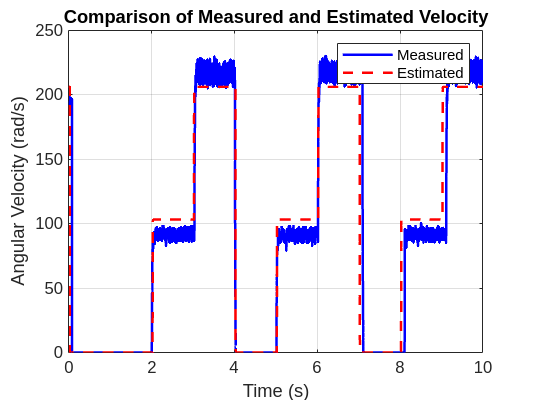

[lag, shift] = max(xcorr(omega_measured, omega_est));
omega_est = circshift(omega_est, shift);
scale_factor = mean(omega_measured) / mean(omega_est);
omega_est = omega_est * scale_factor;
figure;
plot(t, omega_measured, 'b', 'LineWidth', 1.5);
hold on;
plot(t, omega_est, 'r--', 'LineWidth', 1.5);
legend('Measured', 'Estimated');
xlabel('Time (s)');
ylabel('Angular Velocity (rad/s)');
title('Comparison of Measured and Estimated Velocity');
grid on;

RMSE_Eff = [68.4; 82.7; 96.19; 71.47; 87.08; 71.03; 67.39; 79.75; 68.4; 92.04; 97.5; 96.69; 71.06; 80.33; 58.45];
RMSE_Ke  = [0.0353880121; 0.0273202987; 0.0065646289; 0.0633349803; 0.0579858794; 0.0546723956; 0.0567922398; 0.0444613429; 0.0532289309; 0.0435533653; 0.0547892003; 0.0554254621; 0.0224546416; 0.0071644222; 0.0042294812];
RMSE_Jm  = [2.8911e-05; 2.1808e-05; 5.2126e-06; 1.2049e-05; 1.4433e-05; 7.9939e-06; 8.403e-06; 0.00062978; 3.01626e-05; 0.0007097904; 0.0002388322; 0.0000906267; 1.13058e-05; 1.0375e-06; 2.499e-07];
RMSE_Bm  = [8.7616e-05; 1.7624e-05; 3.2519e-06; 4.6507e-05; 2.0547e-05; 9.2517e-06; 2.8147e-05; 7.5642e-06; 3.07375e-05; 0.000016722; 0.0000023562; 0.000002345; 2.86568e-05; 1.5354e-06; 2.953e-07];
    
SSE_Eff  = [99; 99; 93.04; 95.58; 98.98; 97.96; 98.89; 42.02; 90.8; 94.72; 99; 84.69; 98.91; 99; 99];
SSE_Ke   = [0.0460833289; 0.025067546; 0.0075978717; 0.0668036465; 0.0555820584; 0.0533618809; 0.054925464; 0.0382992373; 0.0426608427; 0.0447649551; 0.0506346276; 0.0489119604; 0.0258034149; 0.0055759793; 0.0047408229];
SSE_Jm   = [5.449e-05; 2.3959e-05; 5.8348e-06; 1.7005e-05; 1.572e-05; 1.0766e-05; 1.192e-05; 0.00028583; 0.000032092; 0.0007508149; 0.0002241214; 0.0000700426; 1.13058e-05; 1.0375e-06; 4.76e-07];
SSE_Bm   = [5.6693e-05; 3.1956e-05; 1.9606e-06; 1.6381e-05; 5.1771e-05; 2.7678e-05; 6.2477e-05; 2.5474e-05; 0.0001236751; 0.0000062697; 0.0000484911; 0.0000617688; 2.86568e-05; 3.4098e-06; 3.8e-08];

AbsError_Eff = [98.27; 30.5; 90.8; 81.2; 99; 98.61; 98.49; 93.82; 86.46; 98.99; 98.11; 99; 98.97; 97.47; 89.69];
AbsError_Ke  = [0.0503198156; 0.0308298998; 0.0060829854; 0.0632742008; 0.0564081616; 0.0558769486; 0.0531067814; 0.0575716074; 0.0514702555; 0.0448745085; 0.050246204; 0.051825418; 0.0262734247; 0.0080788707; 0.0047371895];
AbsError_Jm  = [5.4312e-05; 8.5996e-06; 4.2047e-06; 5.002e-06; 1.3811e-05; 1.1017e-05; 9.4135e-06; 1.6e-09; 2.12815e-05; 0.0007051455; 0.0002116732; 0.0000846336; 1.71311e-05; 1.3559e-06; 4.307e-07];
AbsError_Bm  = [5.305e-07; 3.79e-08; 3.57e-08; 5.4234e-05; 4.2939e-05; 1e-09; 7.2215e-05; 3.5912e-05; 4.75506e-05; 0.0000224372; 0.0000580198; 0.0000507779; 1.75166e-05; 1e-09; 1e-09];

NMSE_Eff = [95.56; 67.92; 73.11; 72.74; 72.13; 74.4; 71.37; 72.12; 71.71; 74.27; 69.92; 71.5; 70.69; 51.29; 28.04];
NMSE_Ke  = [0.0384307746; 0.0205009051; 0.003957887; 0.0524003826; 0.0467449905; 0.042286228; 0.0451824567; 0.0348209991; 0.0433489222; 0.0344621643; 0.0420658725; 0.043159797; 0.0268573161; 0.0000630292; 0.0047413137];
NMSE_Jm  = [4.3864e-05; 1.3441e-05; 2.3894e-06; 1.0223e-05; 9.6388e-06; 6.4907e-06; 7.0771e-06; 0.00044604; 2.57577e-05; 0.0004451668; 0.0001315146; 0.0000522032; 1.34512e-05; 5.1e-09; 1.353e-07];
NMSE_Bm  = [0.00010808; 3.1949e-05; 3.2295e-06; 0.00013179; 9.7948e-05; 9.4096e-05; 0.00010692; 5.9151e-05; 9.44926e-05; 0.0000650916; 8.44638e-05; 8.54687e-05; 1.55314e-05; 5.87e-08; 1.05e-08];


Rm = 2.3;    
Lm = 0.004;   
numParamSets = length(SSE_Eff);
numTests = length(inputSignals); 
avg_rmse = zeros(numParamSets,1);
avg_mae  = zeros(numParamSets,1);
avg_r2   = zeros(numParamSets,1);
avg_corr = zeros(numParamSets,1);

for i = 1:numParamSets
    % Construct the parameter set dynamically
    params = [SSE_Eff(i), SSE_Ke(i), SSE_Jm(i), SSE_Bm(i)];
    
    % Preallocate performance metric arrays for this parameter set
    rmse_all = zeros(numTests,1);
    mae_all  = zeros(numTests,1);
    r2_all   = zeros(numTests,1);
    corr_all = zeros(numTests,1);

    for k = 1:numTests
        V = inputSignals{k};
        omega_measured = measuredOmega{k};
        
        t = double(SineWave{3}{6}.Values.Time); % Ensure this exists in your workspace
        
            % Simulate the motor response using the current parameter set
        omega_est = motor_model(params, Rm, Lm, t, V);
        
        % Compute error between measured and estimated motor velocity
        error = omega_measured - omega_est;
        
        % Compute performance metrics
        rmse_all(k) = sqrt(mean(error.^2));
        mae_all(k)  = mean(abs(error));
        SStot       = sum((omega_measured - mean(omega_measured)).^2);
        SSres       = sum(error.^2);
        r2_all(k)   = 1 - (SSres / SStot);
        corr_all(k) = corr(omega_measured, omega_est);
        
        % Display metrics for each test
        fprintf('Param Set %d, Test %d: RMSE = %.4f, MAE = %.4f, R^2 = %.4f, Corr = %.4f\n', ...
                i, k, rmse_all(k), mae_all(k), r2_all(k), corr_all(k));
    end

    avg_rmse(i) = mean(rmse_all);
    avg_mae(i)  = mean(mae_all);
    avg_r2(i)   = mean(r2_all);
    avg_corr(i) = mean(corr_all);
    
    fprintf('==> Parameter Set %d: Avg RMSE = %.4f, Avg MAE = %.4f, Avg R^2 = %.4f, Avg Corr = %.4f\n\n', ...
            i, avg_rmse(i), avg_mae(i), avg_r2(i), avg_corr(i));
end

Poles of the system:
 -569.7089
   -5.2923



Param Set 1, Test 1: RMSE = 23.8947, MAE = 16.5889, R^2 = -0.0369, Corr = 0.8670


Poles of the system:
 -569.7089
   -5.2923



Param Set 1, Test 2: RMSE = 80.6092, MAE = 65.5366, R^2 = -0.0252, Corr = 0.9428


Poles of the system:
 -569.7089
   -5.2923



Param Set 1, Test 3: RMSE = 139.0128, MAE = 117.1616, R^2 = -0.0256, Corr = 0.9565


Poles of the system:
 -569.7089
   -5.2923



Param Set 1, Test 4: RMSE = 85.5653, MAE = 80.7980, R^2 = -8.2220, Corr = 0.7491


Poles of the system:
 -569.7089
   -5.2923



Param Set 1, Test 5: RMSE = 142.6602, MAE = 135.6690, R^2 = -9.4465, Corr = 0.9458


Poles of the system:
 -569.7089
   -5.2923



Param Set 1, Test 6: RMSE = 142.6321, MAE = 135.6423, R^2 = -9.4423, Corr = 0.9458


Poles of the system:
 -569.7089
   -5.2923



Param Set 1, Test 7: RMSE = 116.8094, MAE = 93.7340, R^2 = -1.8052, Corr = 0.9593


Poles of the system:
 -569.7089
   -5.2923



Param Set 1, Test 8: RMSE = 173.7869, MAE = 155.4077, R^2 = -3.9865, Corr = 0.9696


Poles of the system:
 -569.7089
   -5.2923



Param Set 1, Test 9: RMSE = 207.4618, MAE = 202.5025, R^2 = -20.1466, Corr = 0.9090


Poles of the system:
 -569.7089
   -5.2923



Param Set 1, Test 10: RMSE = 140.6948, MAE = 119.2453, R^2 = -0.0004, Corr = 0.9373


Poles of the system:
 -569.7089
   -5.2923



Param Set 1, Test 11: RMSE = 139.4752, MAE = 119.2995, R^2 = 0.0004, Corr = 0.9675


Poles of the system:
 -569.7089
   -5.2923



Param Set 1, Test 12: RMSE = 133.0149, MAE = 113.4088, R^2 = 0.0003, Corr = 0.9011


Poles of the system:
 -569.7089
   -5.2923



Param Set 1, Test 13: RMSE = 95.7408, MAE = 56.6281, R^2 = -0.5365, Corr = 0.8611


Poles of the system:
 -569.7089
   -5.2923



Param Set 1, Test 14: RMSE = 105.4669, MAE = 82.1561, R^2 = -1.5404, Corr = 0.9904


Poles of the system:
 -569.7089
   -5.2923



Param Set 1, Test 15: RMSE = 128.4223, MAE = 92.6514, R^2 = -1.0833, Corr = 0.9234


==> Parameter Set 1: Avg RMSE = 123.6831, Avg MAE = 105.7620, Avg R^2 = -3.7531, Avg Corr = 0.9217



Poles of the system:
 -569.5154
   -5.4856



Param Set 2, Test 1: RMSE = 23.8946, MAE = 16.5888, R^2 = -0.0369, Corr = 0.8701


Poles of the system:
 -569.5154
   -5.4856



Param Set 2, Test 2: RMSE = 80.6091, MAE = 65.5365, R^2 = -0.0252, Corr = 0.9467


Poles of the system:
 -569.5154
   -5.4856



Param Set 2, Test 3: RMSE = 139.0127, MAE = 117.1616, R^2 = -0.0256, Corr = 0.9603


Poles of the system:
 -569.5154
   -5.4856



Param Set 2, Test 4: RMSE = 85.5653, MAE = 80.7979, R^2 = -8.2220, Corr = 0.7503


Poles of the system:
 -569.5154
   -5.4856



Param Set 2, Test 5: RMSE = 142.6601, MAE = 135.6689, R^2 = -9.4465, Corr = 0.9474


Poles of the system:
 -569.5154
   -5.4856



Param Set 2, Test 6: RMSE = 142.6320, MAE = 135.6422, R^2 = -9.4423, Corr = 0.9474


Poles of the system:
 -569.5154
   -5.4856



Param Set 2, Test 7: RMSE = 116.8093, MAE = 93.7339, R^2 = -1.8052, Corr = 0.9592


Poles of the system:
 -569.5154
   -5.4856



Param Set 2, Test 8: RMSE = 173.7868, MAE = 155.4076, R^2 = -3.9865, Corr = 0.9695


Poles of the system:
 -569.5154
   -5.4856



Param Set 2, Test 9: RMSE = 207.4618, MAE = 202.5024, R^2 = -20.1465, Corr = 0.9090


Poles of the system:
 -569.5154
   -5.4856



Param Set 2, Test 10: RMSE = 140.6935, MAE = 119.2440, R^2 = -0.0004, Corr = 0.9421


Poles of the system:
 -569.5154
   -5.4856



Param Set 2, Test 11: RMSE = 139.4741, MAE = 119.2985, R^2 = 0.0005, Corr = 0.9690


Poles of the system:
 -569.5154
   -5.4856



Param Set 2, Test 12: RMSE = 133.0142, MAE = 113.4083, R^2 = 0.0003, Corr = 0.8986


Poles of the system:
 -569.5154
   -5.4856



Param Set 2, Test 13: RMSE = 95.7404, MAE = 56.6278, R^2 = -0.5365, Corr = 0.8650


Poles of the system:
 -569.5154
   -5.4856



Param Set 2, Test 14: RMSE = 105.4669, MAE = 82.1560, R^2 = -1.5404, Corr = 0.9904


Poles of the system:
 -569.5154
   -5.4856



Param Set 2, Test 15: RMSE = 128.4220, MAE = 92.6510, R^2 = -1.0832, Corr = 0.9259


==> Parameter Set 2: Avg RMSE = 123.6829, Avg MAE = 105.7617, Avg R^2 = -3.7531, Avg Corr = 0.9234



Poles of the system:
 -574.0272
   -0.9736



Param Set 3, Test 1: RMSE = 23.8982, MAE = 16.5916, R^2 = -0.0372, Corr = 0.5220


Poles of the system:
 -574.0272
   -0.9736



Param Set 3, Test 2: RMSE = 80.6131, MAE = 65.5400, R^2 = -0.0253, Corr = 0.5461


Poles of the system:
 -574.0272
   -0.9736



Param Set 3, Test 3: RMSE = 139.0168, MAE = 117.1652, R^2 = -0.0257, Corr = 0.5557


Poles of the system:
 -574.0272
   -0.9736



Param Set 3, Test 4: RMSE = 85.5674, MAE = 80.8000, R^2 = -8.2225, Corr = 0.6285


Poles of the system:
 -574.0272
   -0.9736



Param Set 3, Test 5: RMSE = 142.6634, MAE = 135.6720, R^2 = -9.4469, Corr = 0.7967


Poles of the system:
 -574.0272
   -0.9736



Param Set 3, Test 6: RMSE = 142.6363, MAE = 135.6463, R^2 = -9.4430, Corr = 0.7967


Poles of the system:
 -574.0272
   -0.9736



Param Set 3, Test 7: RMSE = 116.8136, MAE = 93.7378, R^2 = -1.8054, Corr = 0.9649


Poles of the system:
 -574.0272
   -0.9736



Param Set 3, Test 8: RMSE = 173.7893, MAE = 155.4123, R^2 = -3.9866, Corr = 0.9593


Poles of the system:
 -574.0272
   -0.9736



Param Set 3, Test 9: RMSE = 207.4644, MAE = 202.5060, R^2 = -20.1471, Corr = 0.7882


Poles of the system:
 -574.0272
   -0.9736



Param Set 3, Test 10: RMSE = 140.7373, MAE = 119.2824, R^2 = -0.0010, Corr = 0.6504


Poles of the system:
 -574.0272
   -0.9736



Param Set 3, Test 11: RMSE = 139.5013, MAE = 119.3226, R^2 = 0.0001, Corr = 0.8584


Poles of the system:
 -574.0272
   -0.9736



Param Set 3, Test 12: RMSE = 133.0315, MAE = 113.4233, R^2 = 0.0001, Corr = 0.9127


Poles of the system:
 -574.0272
   -0.9736



Param Set 3, Test 13: RMSE = 95.7575, MAE = 56.6445, R^2 = -0.5370, Corr = 0.6427


Poles of the system:
 -574.0272
   -0.9736



Param Set 3, Test 14: RMSE = 105.4713, MAE = 82.1606, R^2 = -1.5406, Corr = 0.9936


Poles of the system:
 -574.0272
   -0.9736



Param Set 3, Test 15: RMSE = 128.4404, MAE = 92.6726, R^2 = -1.0838, Corr = 0.6404


==> Parameter Set 3: Avg RMSE = 123.6935, Avg MAE = 105.7718, Avg R^2 = -3.7535, Avg Corr = 0.7504



Poles of the system:
 -574.0244
   -0.9759



Param Set 4, Test 1: RMSE = 23.8983, MAE = 16.5916, R^2 = -0.0372, Corr = 0.5225


Poles of the system:
 -574.0244
   -0.9759



Param Set 4, Test 2: RMSE = 80.6131, MAE = 65.5400, R^2 = -0.0253, Corr = 0.5467


Poles of the system:
 -574.0244
   -0.9759



Param Set 4, Test 3: RMSE = 139.0168, MAE = 117.1652, R^2 = -0.0257, Corr = 0.5563


Poles of the system:
 -574.0244
   -0.9759



Param Set 4, Test 4: RMSE = 85.5688, MAE = 80.8013, R^2 = -8.2228, Corr = 0.6288


Poles of the system:
 -574.0244
   -0.9759



Param Set 4, Test 5: RMSE = 142.6655, MAE = 135.6740, R^2 = -9.4472, Corr = 0.7970


Poles of the system:
 -574.0244
   -0.9759



Param Set 4, Test 6: RMSE = 142.6391, MAE = 135.6489, R^2 = -9.4434, Corr = 0.7970


Poles of the system:
 -574.0244
   -0.9759



Param Set 4, Test 7: RMSE = 116.8153, MAE = 93.7391, R^2 = -1.8055, Corr = 0.9649


Poles of the system:
 -574.0244
   -0.9759



Param Set 4, Test 8: RMSE = 173.7918, MAE = 155.4144, R^2 = -3.9868, Corr = 0.9593


Poles of the system:
 -574.0244
   -0.9759



Param Set 4, Test 9: RMSE = 207.4673, MAE = 202.5088, R^2 = -20.1477, Corr = 0.7885


Poles of the system:
 -574.0244
   -0.9759



Param Set 4, Test 10: RMSE = 140.7375, MAE = 119.2825, R^2 = -0.0010, Corr = 0.6507


Poles of the system:
 -574.0244
   -0.9759



Param Set 4, Test 11: RMSE = 139.5015, MAE = 119.3227, R^2 = 0.0001, Corr = 0.8586


Poles of the system:
 -574.0244
   -0.9759



Param Set 4, Test 12: RMSE = 133.0316, MAE = 113.4233, R^2 = 0.0001, Corr = 0.9127


Poles of the system:
 -574.0244
   -0.9759



Param Set 4, Test 13: RMSE = 95.7583, MAE = 56.6446, R^2 = -0.5370, Corr = 0.6429


Poles of the system:
 -574.0244
   -0.9759



Param Set 4, Test 14: RMSE = 105.4728, MAE = 82.1618, R^2 = -1.5407, Corr = 0.9936


Poles of the system:
 -574.0244
   -0.9759



Param Set 4, Test 15: RMSE = 128.4416, MAE = 92.6732, R^2 = -1.0839, Corr = 0.6409


==> Parameter Set 4: Avg RMSE = 123.6946, Avg MAE = 105.7728, Avg R^2 = -3.7536, Avg Corr = 0.7507



Poles of the system:
 -571.0047
   -3.9956



Param Set 5, Test 1: RMSE = 23.8953, MAE = 16.5894, R^2 = -0.0369, Corr = 0.8337


Poles of the system:
 -571.0047
   -3.9956



Param Set 5, Test 2: RMSE = 80.6098, MAE = 65.5372, R^2 = -0.0253, Corr = 0.9029


Poles of the system:
 -571.0047
   -3.9956



Param Set 5, Test 3: RMSE = 139.0135, MAE = 117.1623, R^2 = -0.0256, Corr = 0.9163


Poles of the system:
 -571.0047
   -3.9956



Param Set 5, Test 4: RMSE = 85.5657, MAE = 80.7983, R^2 = -8.2221, Corr = 0.7377


Poles of the system:
 -571.0047
   -3.9956



Param Set 5, Test 5: RMSE = 142.6608, MAE = 135.6695, R^2 = -9.4465, Corr = 0.9318


Poles of the system:
 -571.0047
   -3.9956



Param Set 5, Test 6: RMSE = 142.6328, MAE = 135.6430, R^2 = -9.4425, Corr = 0.9318


Poles of the system:
 -571.0047
   -3.9956



Param Set 5, Test 7: RMSE = 116.8100, MAE = 93.7344, R^2 = -1.8053, Corr = 0.9598


Poles of the system:
 -571.0047
   -3.9956



Param Set 5, Test 8: RMSE = 173.7873, MAE = 155.4083, R^2 = -3.9865, Corr = 0.9701


Poles of the system:
 -571.0047
   -3.9956



Param Set 5, Test 9: RMSE = 207.4623, MAE = 202.5031, R^2 = -20.1467, Corr = 0.9063


Poles of the system:
 -571.0047
   -3.9956



Param Set 5, Test 10: RMSE = 140.7054, MAE = 119.2550, R^2 = -0.0006, Corr = 0.8924


Poles of the system:
 -571.0047
   -3.9956



Param Set 5, Test 11: RMSE = 139.4826, MAE = 119.3062, R^2 = 0.0003, Corr = 0.9519


Poles of the system:
 -571.0047
   -3.9956



Param Set 5, Test 12: RMSE = 133.0195, MAE = 113.4128, R^2 = 0.0002, Corr = 0.9153


Poles of the system:
 -571.0047
   -3.9956



Param Set 5, Test 13: RMSE = 95.7438, MAE = 56.6312, R^2 = -0.5366, Corr = 0.8260


Poles of the system:
 -571.0047
   -3.9956



Param Set 5, Test 14: RMSE = 105.4675, MAE = 82.1566, R^2 = -1.5405, Corr = 0.9904


Poles of the system:
 -571.0047
   -3.9956



Param Set 5, Test 15: RMSE = 128.4246, MAE = 92.6546, R^2 = -1.0833, Corr = 0.8993


==> Parameter Set 5: Avg RMSE = 123.6854, Avg MAE = 105.7641, Avg R^2 = -3.7532, Avg Corr = 0.9044



Poles of the system:
 -572.8277
   -2.1725



Param Set 6, Test 1: RMSE = 23.8967, MAE = 16.5906, R^2 = -0.0370, Corr = 0.7148


Poles of the system:
 -572.8277
   -2.1725



Param Set 6, Test 2: RMSE = 80.6114, MAE = 65.5387, R^2 = -0.0253, Corr = 0.7652


Poles of the system:
 -572.8277
   -2.1725



Param Set 6, Test 3: RMSE = 139.0151, MAE = 117.1638, R^2 = -0.0257, Corr = 0.7777


Poles of the system:
 -572.8277
   -2.1725



Param Set 6, Test 4: RMSE = 85.5665, MAE = 80.7991, R^2 = -8.2223, Corr = 0.7023


Poles of the system:
 -572.8277
   -2.1725



Param Set 6, Test 5: RMSE = 142.6619, MAE = 135.6706, R^2 = -9.4467, Corr = 0.8880


Poles of the system:
 -572.8277
   -2.1725



Param Set 6, Test 6: RMSE = 142.6344, MAE = 135.6444, R^2 = -9.4427, Corr = 0.8880


Poles of the system:
 -572.8277
   -2.1725



Param Set 6, Test 7: RMSE = 116.8113, MAE = 93.7355, R^2 = -1.8053, Corr = 0.9616


Poles of the system:
 -572.8277
   -2.1725



Param Set 6, Test 8: RMSE = 173.7881, MAE = 155.4097, R^2 = -3.9866, Corr = 0.9700


Poles of the system:
 -572.8277
   -2.1725



Param Set 6, Test 9: RMSE = 207.4633, MAE = 202.5045, R^2 = -20.1469, Corr = 0.8798


Poles of the system:
 -572.8277
   -2.1725



Param Set 6, Test 10: RMSE = 140.7244, MAE = 119.2717, R^2 = -0.0008, Corr = 0.7753


Poles of the system:
 -572.8277
   -2.1725



Param Set 6, Test 11: RMSE = 139.4939, MAE = 119.3162, R^2 = 0.0002, Corr = 0.9094


Poles of the system:
 -572.8277
   -2.1725



Param Set 6, Test 12: RMSE = 133.0266, MAE = 113.4190, R^2 = 0.0001, Corr = 0.9238


Poles of the system:
 -572.8277
   -2.1725



Param Set 6, Test 13: RMSE = 95.7510, MAE = 56.6384, R^2 = -0.5368, Corr = 0.7348


Poles of the system:
 -572.8277
   -2.1725



Param Set 6, Test 14: RMSE = 105.4689, MAE = 82.1579, R^2 = -1.5405, Corr = 0.9913


Poles of the system:
 -572.8277
   -2.1725



Param Set 6, Test 15: RMSE = 128.4314, MAE = 92.6633, R^2 = -1.0835, Corr = 0.8119


==> Parameter Set 6: Avg RMSE = 123.6897, Avg MAE = 105.7682, Avg R^2 = -3.7533, Avg Corr = 0.8463



Poles of the system:
 -570.1222
   -4.8780



Param Set 7, Test 1: RMSE = 23.8948, MAE = 16.5890, R^2 = -0.0369, Corr = 0.8590


Poles of the system:
 -570.1222
   -4.8780



Param Set 7, Test 2: RMSE = 80.6093, MAE = 65.5367, R^2 = -0.0252, Corr = 0.9330


Poles of the system:
 -570.1222
   -4.8780



Param Set 7, Test 3: RMSE = 139.0130, MAE = 117.1618, R^2 = -0.0256, Corr = 0.9466


Poles of the system:
 -570.1222
   -4.8780



Param Set 7, Test 4: RMSE = 85.5654, MAE = 80.7980, R^2 = -8.2220, Corr = 0.7460


Poles of the system:
 -570.1222
   -4.8780



Param Set 7, Test 5: RMSE = 142.6602, MAE = 135.6690, R^2 = -9.4465, Corr = 0.9421


Poles of the system:
 -570.1222
   -4.8780



Param Set 7, Test 6: RMSE = 142.6321, MAE = 135.6423, R^2 = -9.4424, Corr = 0.9421


Poles of the system:
 -570.1222
   -4.8780



Param Set 7, Test 7: RMSE = 116.8095, MAE = 93.7340, R^2 = -1.8052, Corr = 0.9594


Poles of the system:
 -570.1222
   -4.8780



Param Set 7, Test 8: RMSE = 173.7869, MAE = 155.4077, R^2 = -3.9865, Corr = 0.9698


Poles of the system:
 -570.1222
   -4.8780



Param Set 7, Test 9: RMSE = 207.4618, MAE = 202.5025, R^2 = -20.1466, Corr = 0.9086


Poles of the system:
 -570.1222
   -4.8780



Param Set 7, Test 10: RMSE = 140.6978, MAE = 119.2481, R^2 = -0.0005, Corr = 0.9256


Poles of the system:
 -570.1222
   -4.8780



Param Set 7, Test 11: RMSE = 139.4774, MAE = 119.3015, R^2 = 0.0004, Corr = 0.9636


Poles of the system:
 -570.1222
   -4.8780



Param Set 7, Test 12: RMSE = 133.0163, MAE = 113.4100, R^2 = 0.0003, Corr = 0.9062


Poles of the system:
 -570.1222
   -4.8780



Param Set 7, Test 13: RMSE = 95.7415, MAE = 56.6289, R^2 = -0.5365, Corr = 0.8517


Poles of the system:
 -570.1222
   -4.8780



Param Set 7, Test 14: RMSE = 105.4670, MAE = 82.1562, R^2 = -1.5404, Corr = 0.9904


Poles of the system:
 -570.1222
   -4.8780



Param Set 7, Test 15: RMSE = 128.4228, MAE = 92.6522, R^2 = -1.0833, Corr = 0.9173


==> Parameter Set 7: Avg RMSE = 123.6837, Avg MAE = 105.7625, Avg R^2 = -3.7531, Avg Corr = 0.9174



Poles of the system:
 -574.4889
   -0.5185



Param Set 8, Test 1: RMSE = 23.8980, MAE = 16.5917, R^2 = -0.0371, Corr = 0.3957


Poles of the system:
 -574.4889
   -0.5185



Param Set 8, Test 2: RMSE = 80.6129, MAE = 65.5400, R^2 = -0.0253, Corr = 0.4008


Poles of the system:
 -574.4889
   -0.5185



Param Set 8, Test 3: RMSE = 139.0166, MAE = 117.1651, R^2 = -0.0257, Corr = 0.4071


Poles of the system:
 -574.4889
   -0.5185



Param Set 8, Test 4: RMSE = 85.5176, MAE = 80.7516, R^2 = -8.2117, Corr = 0.5538


Poles of the system:
 -574.4889
   -0.5185



Param Set 8, Test 5: RMSE = 142.5869, MAE = 135.5994, R^2 = -9.4357, Corr = 0.7050


Poles of the system:
 -574.4889
   -0.5185



Param Set 8, Test 6: RMSE = 142.5343, MAE = 135.5495, R^2 = -9.4280, Corr = 0.7050


Poles of the system:
 -574.4889
   -0.5185



Param Set 8, Test 7: RMSE = 116.7580, MAE = 93.6946, R^2 = -1.8028, Corr = 0.9659


Poles of the system:
 -574.4889
   -0.5185



Param Set 8, Test 8: RMSE = 173.7016, MAE = 155.3376, R^2 = -3.9816, Corr = 0.9325


Poles of the system:
 -574.4889
   -0.5185



Param Set 8, Test 9: RMSE = 207.3564, MAE = 202.4017, R^2 = -20.1251, Corr = 0.6847


Poles of the system:
 -574.4889
   -0.5185



Param Set 8, Test 10: RMSE = 140.7365, MAE = 119.2819, R^2 = -0.0010, Corr = 0.5892


Poles of the system:
 -574.4889
   -0.5185



Param Set 8, Test 11: RMSE = 139.5004, MAE = 119.3218, R^2 = 0.0001, Corr = 0.8276


Poles of the system:
 -574.4889
   -0.5185



Param Set 8, Test 12: RMSE = 133.0307, MAE = 113.4226, R^2 = 0.0001, Corr = 0.8981


Poles of the system:
 -574.4889
   -0.5185



Param Set 8, Test 13: RMSE = 95.7347, MAE = 56.6422, R^2 = -0.5363, Corr = 0.6108


Poles of the system:
 -574.4889
   -0.5185



Param Set 8, Test 14: RMSE = 105.4205, MAE = 82.1221, R^2 = -1.5382, Corr = 0.9936


Poles of the system:
 -574.4889
   -0.5185



Param Set 8, Test 15: RMSE = 128.4020, MAE = 92.6547, R^2 = -1.0826, Corr = 0.5238


==> Parameter Set 8: Avg RMSE = 123.6538, Avg MAE = 105.7385, Avg R^2 = -3.7487, Avg Corr = 0.6796



Poles of the system:
 -564.4131
  -10.5876



Param Set 9, Test 1: RMSE = 23.8933, MAE = 16.5878, R^2 = -0.0367, Corr = 0.8909


Poles of the system:
 -564.4131
  -10.5876



Param Set 9, Test 2: RMSE = 80.6076, MAE = 65.5351, R^2 = -0.0252, Corr = 0.9755


Poles of the system:
 -564.4131
  -10.5876



Param Set 9, Test 3: RMSE = 139.0113, MAE = 117.1601, R^2 = -0.0256, Corr = 0.9894


Poles of the system:
 -564.4131
  -10.5876



Param Set 9, Test 4: RMSE = 85.5597, MAE = 80.7925, R^2 = -8.2208, Corr = 0.7673


Poles of the system:
 -564.4131
  -10.5876



Param Set 9, Test 5: RMSE = 142.6516, MAE = 135.6608, R^2 = -9.4452, Corr = 0.9679


Poles of the system:
 -564.4131
  -10.5876



Param Set 9, Test 6: RMSE = 142.6206, MAE = 135.6314, R^2 = -9.4407, Corr = 0.9679


Poles of the system:
 -564.4131
  -10.5876



Param Set 9, Test 7: RMSE = 116.8024, MAE = 93.7283, R^2 = -1.8049, Corr = 0.9585


Poles of the system:
 -564.4131
  -10.5876



Param Set 9, Test 8: RMSE = 173.7774, MAE = 155.3987, R^2 = -3.9859, Corr = 0.9684


Poles of the system:
 -564.4131
  -10.5876



Param Set 9, Test 9: RMSE = 207.4506, MAE = 202.4911, R^2 = -20.1443, Corr = 0.9039


Poles of the system:
 -564.4131
  -10.5876



Param Set 9, Test 10: RMSE = 140.6682, MAE = 119.2202, R^2 = -0.0000, Corr = 0.9775


Poles of the system:
 -564.4131
  -10.5876



Param Set 9, Test 11: RMSE = 139.4497, MAE = 119.2765, R^2 = 0.0008, Corr = 0.9587


Poles of the system:
 -564.4131
  -10.5876



Param Set 9, Test 12: RMSE = 132.9988, MAE = 113.3953, R^2 = 0.0006, Corr = 0.8095


Poles of the system:
 -564.4131
  -10.5876



Param Set 9, Test 13: RMSE = 95.7311, MAE = 56.6205, R^2 = -0.5362, Corr = 0.9166


Poles of the system:
 -564.4131
  -10.5876



Param Set 9, Test 14: RMSE = 105.4603, MAE = 82.1506, R^2 = -1.5401, Corr = 0.9906


Poles of the system:
 -564.4131
  -10.5876



Param Set 9, Test 15: RMSE = 128.4124, MAE = 92.6419, R^2 = -1.0829, Corr = 0.9515


==> Parameter Set 9: Avg RMSE = 123.6730, Avg MAE = 105.7527, Avg R^2 = -3.7525, Avg Corr = 0.9330



Poles of the system:
 -574.4531
   -0.5636



Param Set 10, Test 1: RMSE = 23.8989, MAE = 16.5918, R^2 = -0.0372, Corr = 0.4102


Poles of the system:
 -574.4531
   -0.5636



Param Set 10, Test 2: RMSE = 80.6139, MAE = 65.5406, R^2 = -0.0254, Corr = 0.4177


Poles of the system:
 -574.4531
   -0.5636



Param Set 10, Test 3: RMSE = 139.0176, MAE = 117.1658, R^2 = -0.0257, Corr = 0.4245


Poles of the system:
 -574.4531
   -0.5636



Param Set 10, Test 4: RMSE = 85.5745, MAE = 80.8069, R^2 = -8.2240, Corr = 0.5639


Poles of the system:
 -574.4531
   -0.5636



Param Set 10, Test 5: RMSE = 142.6743, MAE = 135.6823, R^2 = -9.4485, Corr = 0.7174


Poles of the system:
 -574.4531
   -0.5636



Param Set 10, Test 6: RMSE = 142.6508, MAE = 135.6601, R^2 = -9.4451, Corr = 0.7174


Poles of the system:
 -574.4531
   -0.5636



Param Set 10, Test 7: RMSE = 116.8233, MAE = 93.7460, R^2 = -1.8059, Corr = 0.9660


Poles of the system:
 -574.4531
   -0.5636



Param Set 10, Test 8: RMSE = 173.8024, MAE = 155.4248, R^2 = -3.9874, Corr = 0.9370


Poles of the system:
 -574.4531
   -0.5636



Param Set 10, Test 9: RMSE = 207.4788, MAE = 202.5201, R^2 = -20.1500, Corr = 0.6987


Poles of the system:
 -574.4531
   -0.5636



Param Set 10, Test 10: RMSE = 140.7419, MAE = 119.2859, R^2 = -0.0011, Corr = 0.5957


Poles of the system:
 -574.4531
   -0.5636



Param Set 10, Test 11: RMSE = 139.5042, MAE = 119.3250, R^2 = 0.0000, Corr = 0.8310


Poles of the system:
 -574.4531
   -0.5636



Param Set 10, Test 12: RMSE = 133.0335, MAE = 113.4250, R^2 = 0.0000, Corr = 0.8998


Poles of the system:
 -574.4531
   -0.5636



Param Set 10, Test 13: RMSE = 95.7631, MAE = 56.6466, R^2 = -0.5372, Corr = 0.6135


Poles of the system:
 -574.4531
   -0.5636



Param Set 10, Test 14: RMSE = 105.4805, MAE = 82.1686, R^2 = -1.5411, Corr = 0.9938


Poles of the system:
 -574.4531
   -0.5636



Param Set 10, Test 15: RMSE = 128.4497, MAE = 92.6780, R^2 = -1.0841, Corr = 0.5365


==> Parameter Set 10: Avg RMSE = 123.7005, Avg MAE = 105.7778, Avg R^2 = -3.7542, Avg Corr = 0.6882



Poles of the system:
 -570.8897
   -4.1147



Param Set 11, Test 1: RMSE = 23.8952, MAE = 16.5893, R^2 = -0.0369, Corr = 0.8379


Poles of the system:
 -570.8897
   -4.1147



Param Set 11, Test 2: RMSE = 80.6097, MAE = 65.5371, R^2 = -0.0253, Corr = 0.9079


Poles of the system:
 -570.8897
   -4.1147



Param Set 11, Test 3: RMSE = 139.0134, MAE = 117.1622, R^2 = -0.0256, Corr = 0.9213


Poles of the system:
 -570.8897
   -4.1147



Param Set 11, Test 4: RMSE = 85.5657, MAE = 80.7983, R^2 = -8.2221, Corr = 0.7390


Poles of the system:
 -570.8897
   -4.1147



Param Set 11, Test 5: RMSE = 142.6608, MAE = 135.6695, R^2 = -9.4466, Corr = 0.9335


Poles of the system:
 -570.8897
   -4.1147



Param Set 11, Test 6: RMSE = 142.6329, MAE = 135.6430, R^2 = -9.4425, Corr = 0.9335


Poles of the system:
 -570.8897
   -4.1147



Param Set 11, Test 7: RMSE = 116.8100, MAE = 93.7344, R^2 = -1.8053, Corr = 0.9597


Poles of the system:
 -570.8897
   -4.1147



Param Set 11, Test 8: RMSE = 173.7874, MAE = 155.4083, R^2 = -3.9865, Corr = 0.9701


Poles of the system:
 -570.8897
   -4.1147



Param Set 11, Test 9: RMSE = 207.4624, MAE = 202.5032, R^2 = -20.1467, Corr = 0.9068


Poles of the system:
 -570.8897
   -4.1147



Param Set 11, Test 10: RMSE = 140.7044, MAE = 119.2541, R^2 = -0.0005, Corr = 0.8976


Poles of the system:
 -570.8897
   -4.1147



Param Set 11, Test 11: RMSE = 139.4819, MAE = 119.3056, R^2 = 0.0003, Corr = 0.9538


Poles of the system:
 -570.8897
   -4.1147



Param Set 11, Test 12: RMSE = 133.0191, MAE = 113.4124, R^2 = 0.0002, Corr = 0.9143


Poles of the system:
 -570.8897
   -4.1147



Param Set 11, Test 13: RMSE = 95.7435, MAE = 56.6309, R^2 = -0.5366, Corr = 0.8300


Poles of the system:
 -570.8897
   -4.1147



Param Set 11, Test 14: RMSE = 105.4675, MAE = 82.1566, R^2 = -1.5405, Corr = 0.9904


Poles of the system:
 -570.8897
   -4.1147



Param Set 11, Test 15: RMSE = 128.4244, MAE = 92.6543, R^2 = -1.0833, Corr = 0.9023


==> Parameter Set 11: Avg RMSE = 123.6852, Avg MAE = 105.7640, Avg R^2 = -3.7532, Avg Corr = 0.9065



Poles of the system:
 -571.0345
   -3.9669



Param Set 12, Test 1: RMSE = 23.8945, MAE = 16.5890, R^2 = -0.0368, Corr = 0.8327


Poles of the system:
 -571.0345
   -3.9669



Param Set 12, Test 2: RMSE = 80.6090, MAE = 65.5366, R^2 = -0.0252, Corr = 0.9017


Poles of the system:
 -571.0345
   -3.9669



Param Set 12, Test 3: RMSE = 139.0126, MAE = 117.1616, R^2 = -0.0256, Corr = 0.9151


Poles of the system:
 -571.0345
   -3.9669



Param Set 12, Test 4: RMSE = 85.5565, MAE = 80.7894, R^2 = -8.2201, Corr = 0.7373


Poles of the system:
 -571.0345
   -3.9669



Param Set 12, Test 5: RMSE = 142.6467, MAE = 135.6561, R^2 = -9.4445, Corr = 0.9314


Poles of the system:
 -571.0345
   -3.9669



Param Set 12, Test 6: RMSE = 142.6140, MAE = 135.6251, R^2 = -9.4397, Corr = 0.9314


Poles of the system:
 -571.0345
   -3.9669



Param Set 12, Test 7: RMSE = 116.7988, MAE = 93.7255, R^2 = -1.8047, Corr = 0.9598


Poles of the system:
 -571.0345
   -3.9669



Param Set 12, Test 8: RMSE = 173.7711, MAE = 155.3937, R^2 = -3.9856, Corr = 0.9701


Poles of the system:
 -571.0345
   -3.9669



Param Set 12, Test 9: RMSE = 207.4430, MAE = 202.4843, R^2 = -20.1427, Corr = 0.9062


Poles of the system:
 -571.0345
   -3.9669



Param Set 12, Test 10: RMSE = 140.6987, MAE = 119.2495, R^2 = -0.0005, Corr = 0.8911


Poles of the system:
 -571.0345
   -3.9669



Param Set 12, Test 11: RMSE = 139.4786, MAE = 119.3028, R^2 = 0.0004, Corr = 0.9514


Poles of the system:
 -571.0345
   -3.9669



Param Set 12, Test 12: RMSE = 133.0168, MAE = 113.4105, R^2 = 0.0003, Corr = 0.9156


Poles of the system:
 -571.0345
   -3.9669



Param Set 12, Test 13: RMSE = 95.7368, MAE = 56.6281, R^2 = -0.5363, Corr = 0.8251


Poles of the system:
 -571.0345
   -3.9669



Param Set 12, Test 14: RMSE = 105.4571, MAE = 82.1482, R^2 = -1.5400, Corr = 0.9904


Poles of the system:
 -571.0345
   -3.9669



Param Set 12, Test 15: RMSE = 128.4139, MAE = 92.6476, R^2 = -1.0830, Corr = 0.8986


==> Parameter Set 12: Avg RMSE = 123.6766, Avg MAE = 105.7565, Avg R^2 = -3.7523, Avg Corr = 0.9039



Poles of the system:
 -570.2366
   -4.7638



Param Set 13, Test 1: RMSE = 23.8949, MAE = 16.5891, R^2 = -0.0369, Corr = 0.8564


Poles of the system:
 -570.2366
   -4.7638



Param Set 13, Test 2: RMSE = 80.6094, MAE = 65.5368, R^2 = -0.0252, Corr = 0.9299


Poles of the system:
 -570.2366
   -4.7638



Param Set 13, Test 3: RMSE = 139.0130, MAE = 117.1619, R^2 = -0.0256, Corr = 0.9435


Poles of the system:
 -570.2366
   -4.7638



Param Set 13, Test 4: RMSE = 85.5654, MAE = 80.7980, R^2 = -8.2220, Corr = 0.7451


Poles of the system:
 -570.2366
   -4.7638



Param Set 13, Test 5: RMSE = 142.6603, MAE = 135.6691, R^2 = -9.4465, Corr = 0.9410


Poles of the system:
 -570.2366
   -4.7638



Param Set 13, Test 6: RMSE = 142.6322, MAE = 135.6424, R^2 = -9.4424, Corr = 0.9410


Poles of the system:
 -570.2366
   -4.7638



Param Set 13, Test 7: RMSE = 116.8095, MAE = 93.7341, R^2 = -1.8052, Corr = 0.9594


Poles of the system:
 -570.2366
   -4.7638



Param Set 13, Test 8: RMSE = 173.7869, MAE = 155.4078, R^2 = -3.9865, Corr = 0.9698


Poles of the system:
 -570.2366
   -4.7638



Param Set 13, Test 9: RMSE = 207.4619, MAE = 202.5026, R^2 = -20.1466, Corr = 0.9085


Poles of the system:
 -570.2366
   -4.7638



Param Set 13, Test 10: RMSE = 140.6987, MAE = 119.2489, R^2 = -0.0005, Corr = 0.9220


Poles of the system:
 -570.2366
   -4.7638



Param Set 13, Test 11: RMSE = 139.4781, MAE = 119.3021, R^2 = 0.0004, Corr = 0.9623


Poles of the system:
 -570.2366
   -4.7638



Param Set 13, Test 12: RMSE = 133.0167, MAE = 113.4104, R^2 = 0.0003, Corr = 0.9075


Poles of the system:
 -570.2366
   -4.7638



Param Set 13, Test 13: RMSE = 95.7418, MAE = 56.6292, R^2 = -0.5365, Corr = 0.8488


Poles of the system:
 -570.2366
   -4.7638



Param Set 13, Test 14: RMSE = 105.4671, MAE = 82.1562, R^2 = -1.5404, Corr = 0.9904


Poles of the system:
 -570.2366
   -4.7638



Param Set 13, Test 15: RMSE = 128.4230, MAE = 92.6525, R^2 = -1.0833, Corr = 0.9154


==> Parameter Set 13: Avg RMSE = 123.6839, Avg MAE = 105.7627, Avg R^2 = -3.7531, Avg Corr = 0.9161



Poles of the system:
 -572.3822
   -2.6180



Param Set 14, Test 1: RMSE = 23.8963, MAE = 16.5903, R^2 = -0.0370, Corr = 0.7566


Poles of the system:
 -572.3822
   -2.6180



Param Set 14, Test 2: RMSE = 80.6110, MAE = 65.5383, R^2 = -0.0253, Corr = 0.8131


Poles of the system:
 -572.3822
   -2.6180



Param Set 14, Test 3: RMSE = 139.0146, MAE = 117.1633, R^2 = -0.0257, Corr = 0.8260


Poles of the system:
 -572.3822
   -2.6180



Param Set 14, Test 4: RMSE = 85.5665, MAE = 80.7991, R^2 = -8.2223, Corr = 0.7148


Poles of the system:
 -572.3822
   -2.6180



Param Set 14, Test 5: RMSE = 142.6620, MAE = 135.6707, R^2 = -9.4467, Corr = 0.9036


Poles of the system:
 -572.3822
   -2.6180



Param Set 14, Test 6: RMSE = 142.6345, MAE = 135.6446, R^2 = -9.4427, Corr = 0.9036


Poles of the system:
 -572.3822
   -2.6180



Param Set 14, Test 7: RMSE = 116.8112, MAE = 93.7355, R^2 = -1.8053, Corr = 0.9609


Poles of the system:
 -572.3822
   -2.6180



Param Set 14, Test 8: RMSE = 173.7884, MAE = 155.4098, R^2 = -3.9866, Corr = 0.9704


Poles of the system:
 -572.3822
   -2.6180



Param Set 14, Test 9: RMSE = 207.4637, MAE = 202.5047, R^2 = -20.1469, Corr = 0.8916


Poles of the system:
 -572.3822
   -2.6180



Param Set 14, Test 10: RMSE = 140.7196, MAE = 119.2676, R^2 = -0.0008, Corr = 0.8111


Poles of the system:
 -572.3822
   -2.6180



Param Set 14, Test 11: RMSE = 139.4912, MAE = 119.3139, R^2 = 0.0002, Corr = 0.9225


Poles of the system:
 -572.3822
   -2.6180



Param Set 14, Test 12: RMSE = 133.0249, MAE = 113.4175, R^2 = 0.0002, Corr = 0.9235


Poles of the system:
 -572.3822
   -2.6180



Param Set 14, Test 13: RMSE = 95.7491, MAE = 56.6364, R^2 = -0.5367, Corr = 0.7632


Poles of the system:
 -572.3822
   -2.6180



Param Set 14, Test 14: RMSE = 105.4687, MAE = 82.1577, R^2 = -1.5405, Corr = 0.9909


Poles of the system:
 -572.3822
   -2.6180



Param Set 14, Test 15: RMSE = 128.4295, MAE = 92.6608, R^2 = -1.0835, Corr = 0.8441


==> Parameter Set 14: Avg RMSE = 123.6888, Avg MAE = 105.7673, Avg R^2 = -3.7533, Avg Corr = 0.8664



Poles of the system:
 -574.0997
   -0.9004



Param Set 15, Test 1: RMSE = 23.8984, MAE = 16.5916, R^2 = -0.0372, Corr = 0.5044


Poles of the system:
 -574.0997
   -0.9004



Param Set 15, Test 2: RMSE = 80.6133, MAE = 65.5402, R^2 = -0.0253, Corr = 0.5261


Poles of the system:
 -574.0997
   -0.9004



Param Set 15, Test 3: RMSE = 139.0170, MAE = 117.1654, R^2 = -0.0257, Corr = 0.5353


Poles of the system:
 -574.0997
   -0.9004



Param Set 15, Test 4: RMSE = 85.5711, MAE = 80.8035, R^2 = -8.2233, Corr = 0.6197


Poles of the system:
 -574.0997
   -0.9004



Param Set 15, Test 5: RMSE = 142.6690, MAE = 135.6773, R^2 = -9.4478, Corr = 0.7859


Poles of the system:
 -574.0997
   -0.9004



Param Set 15, Test 6: RMSE = 142.6438, MAE = 135.6534, R^2 = -9.4441, Corr = 0.7859


Poles of the system:
 -574.0997
   -0.9004



Param Set 15, Test 7: RMSE = 116.8181, MAE = 93.7414, R^2 = -1.8057, Corr = 0.9652


Poles of the system:
 -574.0997
   -0.9004



Param Set 15, Test 8: RMSE = 173.7959, MAE = 155.4182, R^2 = -3.9870, Corr = 0.9569


Poles of the system:
 -574.0997
   -0.9004



Param Set 15, Test 9: RMSE = 207.4721, MAE = 202.5135, R^2 = -20.1487, Corr = 0.7762


Poles of the system:
 -574.0997
   -0.9004



Param Set 15, Test 10: RMSE = 140.7386, MAE = 119.2834, R^2 = -0.0010, Corr = 0.6412


Poles of the system:
 -574.0997
   -0.9004



Param Set 15, Test 11: RMSE = 139.5021, MAE = 119.3233, R^2 = 0.0001, Corr = 0.8541


Poles of the system:
 -574.0997
   -0.9004



Param Set 15, Test 12: RMSE = 133.0320, MAE = 113.4238, R^2 = 0.0001, Corr = 0.9109


Poles of the system:
 -574.0997
   -0.9004



Param Set 15, Test 13: RMSE = 95.7599, MAE = 56.6452, R^2 = -0.5371, Corr = 0.6370


Poles of the system:
 -574.0997
   -0.9004



Param Set 15, Test 14: RMSE = 105.4755, MAE = 82.1641, R^2 = -1.5408, Corr = 0.9937


Poles of the system:
 -574.0997
   -0.9004



Param Set 15, Test 15: RMSE = 128.4443, MAE = 92.6747, R^2 = -1.0840, Corr = 0.6237


==> Parameter Set 15: Avg RMSE = 123.6968, Avg MAE = 105.7746, Avg R^2 = -3.7538, Avg Corr = 0.7411




%% Summarize All Metrics in a Table
performanceTable = table((1:numParamSets)', avg_rmse, avg_mae, avg_r2, avg_corr, ...
    'VariableNames', {'ParamSet','Avg_RMSE','Avg_MAE','Avg_R2','Avg_Correlation'});

disp('Summary of Performance Metrics for Each Motor Parameter Set:');

Summary of Performance Metrics for Each Motor Parameter Set:


disp(performanceTable);

    ParamSet    Avg_RMSE    Avg_MAE    Avg_R2     Avg_Correlation
    ________    ________    _______    _______    _______________

        1        123.68     105.76     -3.7531        0.92171    
        2        123.68     105.76     -3.7531         0.9234    
        3        123.69     105.77     -3.7535        0.75042    
        4        123.69     105.77     -3.7536         0.7507    
        5        123.69     105.76     -3.7532        0.90439    
        6        123.69     105.77     -3.7533        0.84626    
        7        123.68     105.76     -3.7531        0.91743    
        8        123.65     105.74     -3.7487        0.67956    
        9        123.67     105.75     -3.7525        0.93296    
       10         123.7     105.78     -3.7542         0.6882    
       11        123.69     105.76   


% Load estimated parameters from MATLAB.mat
data = load('matlab.mat'); % Ensure this contains paramsTable
paramsTable = data.resultsTable; % Extract parameter table

% Define signals (15 total)
signals = {'Chirp', 'Chirp2', 'Chirp3', 'Step', 'Step2', 'Step3', 'Ramp', 'Ramp2', 'Ramp3', ...
           'sin', 'sin2', 'sin3', 'Stair', 'Stair2', 'Stair3'};

% Fixed motor parameters
Rm_fixed = 2.51186;   % Motor Resistance
Lm_fixed = 0.0027645; % Motor Inductance

% Total number of evaluations
numSignals = length(signals); % 15 signals
numMethods = 4;               % SSE, Abs, RMSE, NMSE
numEvaluations = numSignals * numSignals * numMethods; % 900 evaluations

% Storage for error metrics (900 rows × 4 columns)
rmse_all = zeros(numEvaluations, 1);
mae_all  = zeros(numEvaluations, 1);
r2_all   = zeros(numEvaluations, 1);
corr_all = zeros(numEvaluations, 1);

% Create indexing for table
rowNames = cell(numEvaluations, 1);
rowCounter = 1;

% Loop over all signals (15 signals as input)
for inputIdx = 1:numSignals
    inputSignal = signals{inputIdx};

    % Load input voltage (V)
    V = eval(['V_input_', inputSignal]);

    % Assign correct time vector
    if exist(['Time_input_', inputSignal], 'var')
        t = eval(['Time_input_', inputSignal]);
    else
        error(['Time vector missing for ', inputSignal]);
    end

    % Ensure column vectors
    t = t(:);
    V = V(:);

    % Loop over all parameter estimation methods (4 methods per signal)
    for method = 1:numMethods
        switch method
            case 1
                params = [paramsTable.Ke_SSE(inputIdx), paramsTable.Jm_SSE(inputIdx), ...
                          paramsTable.Bm_SSE(inputIdx), paramsTable.Eff_SSE(inputIdx)];
                methodName = 'SSE';
            case 2
                params = [paramsTable.Ke_Abs(inputIdx), paramsTable.Jm_Abs(inputIdx), ...
                          paramsTable.Bm_Abs(inputIdx), paramsTable.Eff_Abs(inputIdx)];
                methodName = 'Abs';
            case 3
                params = [paramsTable.Ke_RMSE(inputIdx), paramsTable.Jm_RMSE(inputIdx), ...
                          paramsTable.Bm_RMSE(inputIdx), paramsTable.Eff_RMSE(inputIdx)];
                methodName = 'RMSE';
            case 4
                params = [paramsTable.Ke_NMSE(inputIdx), paramsTable.Jm_NMSE(inputIdx), ...
                          paramsTable.Bm_NMSE(inputIdx), paramsTable.Eff_NMSE(inputIdx)];
                methodName = 'NMSE';
        end

        % Loop over all validation signals (15 signals to validate against)
        for validationIdx = 1:numSignals
            validationSignal = signals{validationIdx};

            % Load measured speed (omega) for validation
            omega_measured = eval(['omega_', validationSignal]);

            % Ensure column vector
            omega_measured = omega_measured(:);

            % Simulate estimated response
            omega_est = motor_model(params, Rm_fixed, Lm_fixed, t, V);

            % Compute error metrics
            error = omega_measured - omega_est;
            rmse_all(rowCounter) = sqrt(mean(error.^2));
            mae_all(rowCounter)  = mean(abs(error));
            SStot = sum((omega_measured - mean(omega_measured)).^2);
            SSres = sum(error.^2);
            r2_all(rowCounter)   = 1 - (SSres / SStot);
            corr_all(rowCounter) = corr(omega_measured, omega_est);

            % Store row name for identification
            rowNames{rowCounter} = sprintf('%s_%s_%s', inputSignal, validationSignal, methodName);

            % Increment row counter
            rowCounter = rowCounter + 1;
        end
    end
end

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -898.8611
   -9.8578

Poles of the system:
 -898.8611
   -9.8578

Poles of the system:
 -898.8611
   -9.8578

Poles of the system:
 -898.8611
   -9.8578

Poles of the system:
 -898.8611
   -9.8578

Poles of the system:
 -898.8611
   -9.8578

Poles of the system:
 -898.8611
   -9.8578

Poles of the system:
 -898.8611



% Create results table (900 rows)
resultsTable2 = array2table([rmse_all, mae_all, r2_all, corr_all], ...
    'VariableNames', {'RMSE', 'MAE', 'R_squared', 'Correlation'}, ...
    'RowNames', rowNames);

% Display results
disp(resultsTable2);

                           RMSE      MAE      R_squared     Correlation
                          ______    ______    __________    ___________

    Chirp_Chirp_SSE       10.691    8.9649       0.79245         0.8913
    Chirp_Chirp2_SSE      59.937    48.529       0.43319        0.97526
    Chirp_Chirp3_SSE      117.91    98.978       0.26211        0.98909
    Chirp_Step_SSE        85.769    79.414        -8.266       -0.11382
    Chirp_Step2_SSE       141.76    134.31       -9.3146       -0.11468
    Chirp_Step3_SSE       141.76    134.31       -9.3146       -0.11468
    Chirp_Ramp_SSE        118.47    98.732       -1.8858       -0.19599
    Chirp_Ramp2_SSE       174.61    153.91       -4.0337       -0.26965
    

writetable(paramsTable, 'Total_Parameter.xlsx', 'WriteRowNames', true);



numSignals = length(signals); % 15 signals
numMethods = 4;               % SSE, Abs, RMSE, NMSE
numEvaluations = numSignals * numSignals * numMethods; % 900 evaluations

% Storage for error metrics
rmse_all = zeros(numEvaluations, 1);
best_params = zeros(numSignals, 4); % [Ke, Jm, Bm, Eff]

% Create indexing for table
rowNames = cell(numEvaluations, 1);
rowCounter = 1;

% Loop over all signals (15 signals as input)
for inputIdx = 1:numSignals
    inputSignal = signals{inputIdx};

    % Load input voltage (V)
    V = eval(['V_input_', inputSignal]);

    % Assign correct time vector
    if exist(['Time_input_', inputSignal], 'var')
        t = eval(['Time_input_', inputSignal]);
    else
        error(['Time vector missing for ', inputSignal]);
    end

    % Ensure column vectors
    t = t(:);
    V = V(:);

    % Initialize best RMSE to a large number
    best_rmse = Inf;
    best_method = '';

    % Loop over all parameter estimation methods (4 methods per signal)
    for method = 1:numMethods
        switch method
            case 1
                params = [paramsTable.Ke_SSE(inputIdx), paramsTable.Jm_SSE(inputIdx), ...
                          paramsTable.Bm_SSE(inputIdx), paramsTable.Eff_SSE(inputIdx)];
                methodName = 'SSE';
            case 2
                params = [paramsTable.Ke_Abs(inputIdx), paramsTable.Jm_Abs(inputIdx), ...
                          paramsTable.Bm_Abs(inputIdx), paramsTable.Eff_Abs(inputIdx)];
                methodName = 'Abs';
            case 3
                params = [paramsTable.Ke_RMSE(inputIdx), paramsTable.Jm_RMSE(inputIdx), ...
                          paramsTable.Bm_RMSE(inputIdx), paramsTable.Eff_RMSE(inputIdx)];
                methodName = 'RMSE';
            case 4
                params = [paramsTable.Ke_NMSE(inputIdx), paramsTable.Jm_NMSE(inputIdx), ...
                          paramsTable.Bm_NMSE(inputIdx), paramsTable.Eff_NMSE(inputIdx)];
                methodName = 'NMSE';
        end

        % Loop over all validation signals (15 signals to validate against)
        for validationIdx = 1:numSignals
            validationSignal = signals{validationIdx};

            % Load measured speed (omega) for validation
            omega_measured = eval(['omega_', validationSignal]);

            % Ensure column vector
            omega_measured = omega_measured(:);

            % Simulate estimated response
            omega_est = motor_model(params, Rm_fixed, Lm_fixed, t, V);
            error = omega_measured - omega_est;
            rmse_value = sqrt(mean(error.^2));
            rowNames{rowCounter} = sprintf('%s_%s_%s', inputSignal, validationSignal, methodName);
            rmse_all(rowCounter) = rmse_value;
            if rmse_value < best_rmse
                best_rmse = rmse_value;
                best_params(inputIdx, :) = params; % Store best params
                best_method = methodName;
            end
            rowCounter = rowCounter + 1;
        end
    end
    fprintf('Best method for %s: %s with RMSE = %.4f\n', inputSignal, best_method, best_rmse);
end

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -900.1138
   -9.5549

Poles of the system:
 -898.8611
   -9.8578

Poles of the system:
 -898.8611
   -9.8578

Poles of the system:
 -898.8611
   -9.8578

Poles of the system:
 -898.8611
   -9.8578

Poles of the system:
 -898.8611
   -9.8578

Poles of the system:
 -898.8611
   -9.8578

Poles of the system:
 -898.8611
   -9.8578

Poles of the system:
 -898.8611


Best method for Chirp: SSE with RMSE = 10.6907


Poles of the system:
 -907.0794
  -10.3299

Poles of the system:
 -907.0794
  -10.3299

Poles of the system:
 -907.0794
  -10.3299

Poles of the system:
 -907.0794
  -10.3299

Poles of the system:
 -907.0794
  -10.3299

Poles of the system:
 -907.0794
  -10.3299

Poles of the system:
 -907.0794
  -10.3299

Poles of the system:
 -907.0794
  -10.3299

Poles of the system:
 -907.0794
  -10.3299

Poles of the system:
 -907.0794
  -10.3299

Poles of the system:
 -907.0794
  -10.3299

Poles of the system:
 -907.0794
  -10.3299

Poles of the system:
 -907.0794
  -10.3299

Poles of the system:
 -907.0794
  -10.3299

Poles of the system:
 -907.0794
  -10.3299

Poles of the system:
 -898.2391
  -10.3755

Poles of the system:
 -898.2391
  -10.3755

Poles of the system:
 -898.2391
  -10.3755

Poles of the system:
 -898.2391
  -10.3755

Poles of the system:
 -898.2391
  -10.3755

Poles of the system:
 -898.2391
  -10.3755

Poles of the system:
 -898.2391
  -10.3755

Poles of the system:
 -898.2391


Best method for Chirp2: RMSE with RMSE = 17.5038


Poles of the system:
 -898.2980
  -10.3160

Poles of the system:
 -898.2980
  -10.3160

Poles of the system:
 -898.2980
  -10.3160

Poles of the system:
 -898.2980
  -10.3160

Poles of the system:
 -898.2980
  -10.3160

Poles of the system:
 -898.2980
  -10.3160

Poles of the system:
 -898.2980
  -10.3160

Poles of the system:
 -898.2980
  -10.3160

Poles of the system:
 -898.2980
  -10.3160

Poles of the system:
 -898.2980
  -10.3160

Poles of the system:
 -898.2980
  -10.3160

Poles of the system:
 -898.2980
  -10.3160

Poles of the system:
 -898.2980
  -10.3160

Poles of the system:
 -898.2980
  -10.3160

Poles of the system:
 -898.2980
  -10.3160

Poles of the system:
 -898.2624
  -10.3517

Poles of the system:
 -898.2624
  -10.3517

Poles of the system:
 -898.2624
  -10.3517

Poles of the system:
 -898.2624
  -10.3517

Poles of the system:
 -898.2624
  -10.3517

Poles of the system:
 -898.2624
  -10.3517

Poles of the system:
 -898.2624
  -10.3517

Poles of the system:
 -898.2624


Best method for Chirp3: RMSE with RMSE = 19.9461


Poles of the system:
 -853.3108
  -56.1592

Poles of the system:
 -853.3108
  -56.1592

Poles of the system:
 -853.3108
  -56.1592

Poles of the system:
 -853.3108
  -56.1592

Poles of the system:
 -853.3108
  -56.1592

Poles of the system:
 -853.3108
  -56.1592

Poles of the system:
 -853.3108
  -56.1592

Poles of the system:
 -853.3108
  -56.1592

Poles of the system:
 -853.3108
  -56.1592

Poles of the system:
 -853.3108
  -56.1592

Poles of the system:
 -853.3108
  -56.1592

Poles of the system:
 -853.3108
  -56.1592

Poles of the system:
 -853.3108
  -56.1592

Poles of the system:
 -853.3108
  -56.1592

Poles of the system:
 -853.3108
  -56.1592

Poles of the system:
   1.0e+03 *

  -0.5188 + 1.7825i
  -0.5188 - 1.7825i

Poles of the system:
   1.0e+03 *

  -0.5188 + 1.7825i
  -0.5188 - 1.7825i

Poles of the system:
   1.0e+03 *

  -0.5188 + 1.7825i
  -0.5188 - 1.7825i

Poles of the system:
   1.0e+03 *

  -0.5188 + 1.7825i
  -0.5188 - 1.7825i

Poles of the system:
   1.0e+03 *

 

Best method for Step: SSE with RMSE = 18.3663


Poles of the system:
 -862.4799
  -46.1330

Poles of the system:
 -862.4799
  -46.1330

Poles of the system:
 -862.4799
  -46.1330

Poles of the system:
 -862.4799
  -46.1330

Poles of the system:
 -862.4799
  -46.1330

Poles of the system:
 -862.4799
  -46.1330

Poles of the system:
 -862.4799
  -46.1330

Poles of the system:
 -862.4799
  -46.1330

Poles of the system:
 -862.4799
  -46.1330

Poles of the system:
 -862.4799
  -46.1330

Poles of the system:
 -862.4799
  -46.1330

Poles of the system:
 -862.4799
  -46.1330

Poles of the system:
 -862.4799
  -46.1330

Poles of the system:
 -862.4799
  -46.1330

Poles of the system:
 -862.4799
  -46.1330

Poles of the system:
 -856.5390
  -53.3983

Poles of the system:
 -856.5390
  -53.3983

Poles of the system:
 -856.5390
  -53.3983

Poles of the system:
 -856.5390
  -53.3983

Poles of the system:
 -856.5390
  -53.3983

Poles of the system:
 -856.5390
  -53.3983

Poles of the system:
 -856.5390
  -53.3983

Poles of the system:
 -856.5390


Best method for Step2: SSE with RMSE = 8.8841


Poles of the system:
 -862.4901
  -46.1227

Poles of the system:
 -862.4901
  -46.1227

Poles of the system:
 -862.4901
  -46.1227

Poles of the system:
 -862.4901
  -46.1227

Poles of the system:
 -862.4901
  -46.1227

Poles of the system:
 -862.4901
  -46.1227

Poles of the system:
 -862.4901
  -46.1227

Poles of the system:
 -862.4901
  -46.1227

Poles of the system:
 -862.4901
  -46.1227

Poles of the system:
 -862.4901
  -46.1227

Poles of the system:
 -862.4901
  -46.1227

Poles of the system:
 -862.4901
  -46.1227

Poles of the system:
 -862.4901
  -46.1227

Poles of the system:
 -862.4901
  -46.1227

Poles of the system:
 -862.4901
  -46.1227

Poles of the system:
   1.0e+02 *

  -4.6492 + 1.6245i
  -4.6492 - 1.6245i

Poles of the system:
   1.0e+02 *

  -4.6492 + 1.6245i
  -4.6492 - 1.6245i

Poles of the system:
   1.0e+02 *

  -4.6492 + 1.6245i
  -4.6492 - 1.6245i

Poles of the system:
   1.0e+02 *

  -4.6492 + 1.6245i
  -4.6492 - 1.6245i

Poles of the system:
   1.0e+02 *

 

Best method for Step3: SSE with RMSE = 8.8841


Poles of the system:
 -908.0428
   -0.5700

Poles of the system:
 -908.0428
   -0.5700

Poles of the system:
 -908.0428
   -0.5700

Poles of the system:
 -908.0428
   -0.5700

Poles of the system:
 -908.0428
   -0.5700

Poles of the system:
 -908.0428
   -0.5700

Poles of the system:
 -908.0428
   -0.5700

Poles of the system:
 -908.0428
   -0.5700

Poles of the system:
 -908.0428
   -0.5700

Poles of the system:
 -908.0428
   -0.5700

Poles of the system:
 -908.0428
   -0.5700

Poles of the system:
 -908.0428
   -0.5700

Poles of the system:
 -908.0428
   -0.5700

Poles of the system:
 -908.0428
   -0.5700

Poles of the system:
 -908.0428
   -0.5700

Poles of the system:
 -907.9530
   -0.6598

Poles of the system:
 -907.9530
   -0.6598

Poles of the system:
 -907.9530
   -0.6598

Poles of the system:
 -907.9530
   -0.6598

Poles of the system:
 -907.9530
   -0.6598

Poles of the system:
 -907.9530
   -0.6598

Poles of the system:
 -907.9530
   -0.6598

Poles of the system:
 -907.9530


Best method for Ramp: NMSE with RMSE = 14.0665


Poles of the system:
 -906.3059
   -2.7313

Poles of the system:
 -906.3059
   -2.7313

Poles of the system:
 -906.3059
   -2.7313

Poles of the system:
 -906.3059
   -2.7313

Poles of the system:
 -906.3059
   -2.7313

Poles of the system:
 -906.3059
   -2.7313

Poles of the system:
 -906.3059
   -2.7313

Poles of the system:
 -906.3059
   -2.7313

Poles of the system:
 -906.3059
   -2.7313

Poles of the system:
 -906.3059
   -2.7313

Poles of the system:
 -906.3059
   -2.7313

Poles of the system:
 -906.3059
   -2.7313

Poles of the system:
 -906.3059
   -2.7313

Poles of the system:
 -906.3059
   -2.7313

Poles of the system:
 -906.3059
   -2.7313

Poles of the system:
 -905.7405
   -2.8722

Poles of the system:
 -905.7405
   -2.8722

Poles of the system:
 -905.7405
   -2.8722

Poles of the system:
 -905.7405
   -2.8722

Poles of the system:
 -905.7405
   -2.8722

Poles of the system:
 -905.7405
   -2.8722

Poles of the system:
 -905.7405
   -2.8722

Poles of the system:
 -905.7405


Best method for Ramp2: RMSE with RMSE = 18.8014


Poles of the system:
 -901.3147
   -7.2980

Poles of the system:
 -901.3147
   -7.2980

Poles of the system:
 -901.3147
   -7.2980

Poles of the system:
 -901.3147
   -7.2980

Poles of the system:
 -901.3147
   -7.2980

Poles of the system:
 -901.3147
   -7.2980

Poles of the system:
 -901.3147
   -7.2980

Poles of the system:
 -901.3147
   -7.2980

Poles of the system:
 -901.3147
   -7.2980

Poles of the system:
 -901.3147
   -7.2980

Poles of the system:
 -901.3147
   -7.2980

Poles of the system:
 -901.3147
   -7.2980

Poles of the system:
 -901.3147
   -7.2980

Poles of the system:
 -901.3147
   -7.2980

Poles of the system:
 -901.3147
   -7.2980

Poles of the system:
 -901.2103
   -7.6104

Poles of the system:
 -901.2103
   -7.6104

Poles of the system:
 -901.2103
   -7.6104

Poles of the system:
 -901.2103
   -7.6104

Poles of the system:
 -901.2103
   -7.6104

Poles of the system:
 -901.2103
   -7.6104

Poles of the system:
 -901.2103
   -7.6104

Poles of the system:
 -901.2103


Best method for Ramp3: SSE with RMSE = 19.1671


Poles of the system:
 -899.3217
   -9.5853

Poles of the system:
 -899.3217
   -9.5853

Poles of the system:
 -899.3217
   -9.5853

Poles of the system:
 -899.3217
   -9.5853

Poles of the system:
 -899.3217
   -9.5853

Poles of the system:
 -899.3217
   -9.5853

Poles of the system:
 -899.3217
   -9.5853

Poles of the system:
 -899.3217
   -9.5853

Poles of the system:
 -899.3217
   -9.5853

Poles of the system:
 -899.3217
   -9.5853

Poles of the system:
 -899.3217
   -9.5853

Poles of the system:
 -899.3217
   -9.5853

Poles of the system:
 -899.3217
   -9.5853

Poles of the system:
 -899.3217
   -9.5853

Poles of the system:
 -899.3217
   -9.5853

Poles of the system:
 -898.5432
  -10.1588

Poles of the system:
 -898.5432
  -10.1588

Poles of the system:
 -898.5432
  -10.1588

Poles of the system:
 -898.5432
  -10.1588

Poles of the system:
 -898.5432
  -10.1588

Poles of the system:
 -898.5432
  -10.1588

Poles of the system:
 -898.5432
  -10.1588

Poles of the system:
 -898.5432


Best method for sin: SSE with RMSE = 29.4059


Poles of the system:
 -901.5567
   -7.0562

Poles of the system:
 -901.5567
   -7.0562

Poles of the system:
 -901.5567
   -7.0562

Poles of the system:
 -901.5567
   -7.0562

Poles of the system:
 -901.5567
   -7.0562

Poles of the system:
 -901.5567
   -7.0562

Poles of the system:
 -901.5567
   -7.0562

Poles of the system:
 -901.5567
   -7.0562

Poles of the system:
 -901.5567
   -7.0562

Poles of the system:
 -901.5567
   -7.0562

Poles of the system:
 -901.5567
   -7.0562

Poles of the system:
 -901.5567
   -7.0562

Poles of the system:
 -901.5567
   -7.0562

Poles of the system:
 -901.5567
   -7.0562

Poles of the system:
 -901.5567
   -7.0562

Poles of the system:
 -901.9408
   -7.4543

Poles of the system:
 -901.9408
   -7.4543

Poles of the system:
 -901.9408
   -7.4543

Poles of the system:
 -901.9408
   -7.4543

Poles of the system:
 -901.9408
   -7.4543

Poles of the system:
 -901.9408
   -7.4543

Poles of the system:
 -901.9408
   -7.4543

Poles of the system:
 -901.9408


Best method for sin2: SSE with RMSE = 31.1677


Poles of the system:
 -906.2568
   -2.3578

Poles of the system:
 -906.2568
   -2.3578

Poles of the system:
 -906.2568
   -2.3578

Poles of the system:
 -906.2568
   -2.3578

Poles of the system:
 -906.2568
   -2.3578

Poles of the system:
 -906.2568
   -2.3578

Poles of the system:
 -906.2568
   -2.3578

Poles of the system:
 -906.2568
   -2.3578

Poles of the system:
 -906.2568
   -2.3578

Poles of the system:
 -906.2568
   -2.3578

Poles of the system:
 -906.2568
   -2.3578

Poles of the system:
 -906.2568
   -2.3578

Poles of the system:
 -906.2568
   -2.3578

Poles of the system:
 -906.2568
   -2.3578

Poles of the system:
 -906.2568
   -2.3578

Poles of the system:
 -906.8218
   -1.7911

Poles of the system:
 -906.8218
   -1.7911

Poles of the system:
 -906.8218
   -1.7911

Poles of the system:
 -906.8218
   -1.7911

Poles of the system:
 -906.8218
   -1.7911

Poles of the system:
 -906.8218
   -1.7911

Poles of the system:
 -906.8218
   -1.7911

Poles of the system:
 -906.8218


Best method for sin3: SSE with RMSE = 52.0827


Poles of the system:
 -848.2945
  -60.3186

Poles of the system:
 -848.2945
  -60.3186

Poles of the system:
 -848.2945
  -60.3186

Poles of the system:
 -848.2945
  -60.3186

Poles of the system:
 -848.2945
  -60.3186

Poles of the system:
 -848.2945
  -60.3186

Poles of the system:
 -848.2945
  -60.3186

Poles of the system:
 -848.2945
  -60.3186

Poles of the system:
 -848.2945
  -60.3186

Poles of the system:
 -848.2945
  -60.3186

Poles of the system:
 -848.2945
  -60.3186

Poles of the system:
 -848.2945
  -60.3186

Poles of the system:
 -848.2945
  -60.3186

Poles of the system:
 -848.2945
  -60.3186

Poles of the system:
 -848.2945
  -60.3186

Poles of the system:
 -840.3214
  -72.8437

Poles of the system:
 -840.3214
  -72.8437

Poles of the system:
 -840.3214
  -72.8437

Poles of the system:
 -840.3214
  -72.8437

Poles of the system:
 -840.3214
  -72.8437

Poles of the system:
 -840.3214
  -72.8437

Poles of the system:
 -840.3214
  -72.8437

Poles of the system:
 -840.3214


Best method for Stair: SSE with RMSE = 24.2239


Poles of the system:
 -908.0475
   -0.5682

Poles of the system:
 -908.0475
   -0.5682

Poles of the system:
 -908.0475
   -0.5682

Poles of the system:
 -908.0475
   -0.5682

Poles of the system:
 -908.0475
   -0.5682

Poles of the system:
 -908.0475
   -0.5682

Poles of the system:
 -908.0475
   -0.5682

Poles of the system:
 -908.0475
   -0.5682

Poles of the system:
 -908.0475
   -0.5682

Poles of the system:
 -908.0475
   -0.5682

Poles of the system:
 -908.0475
   -0.5682

Poles of the system:
 -908.0475
   -0.5682

Poles of the system:
 -908.0475
   -0.5682

Poles of the system:
 -908.0475
   -0.5682

Poles of the system:
 -908.0475
   -0.5682

Poles of the system:
 -908.0592
   -0.5536

Poles of the system:
 -908.0592
   -0.5536

Poles of the system:
 -908.0592
   -0.5536

Poles of the system:
 -908.0592
   -0.5536

Poles of the system:
 -908.0592
   -0.5536

Poles of the system:
 -908.0592
   -0.5536

Poles of the system:
 -908.0592
   -0.5536

Poles of the system:
 -908.0592


Best method for Stair2: NMSE with RMSE = 7.5061


Poles of the system:
 -893.3687
  -15.2441

Poles of the system:
 -893.3687
  -15.2441

Poles of the system:
 -893.3687
  -15.2441

Poles of the system:
 -893.3687
  -15.2441

Poles of the system:
 -893.3687
  -15.2441

Poles of the system:
 -893.3687
  -15.2441

Poles of the system:
 -893.3687
  -15.2441

Poles of the system:
 -893.3687
  -15.2441

Poles of the system:
 -893.3687
  -15.2441

Poles of the system:
 -893.3687
  -15.2441

Poles of the system:
 -893.3687
  -15.2441

Poles of the system:
 -893.3687
  -15.2441

Poles of the system:
 -893.3687
  -15.2441

Poles of the system:
 -893.3687
  -15.2441

Poles of the system:
 -893.3687
  -15.2441

Poles of the system:
 -882.5297
  -26.0831

Poles of the system:
 -882.5297
  -26.0831

Poles of the system:
 -882.5297
  -26.0831

Poles of the system:
 -882.5297
  -26.0831

Poles of the system:
 -882.5297
  -26.0831

Poles of the system:
 -882.5297
  -26.0831

Poles of the system:
 -882.5297
  -26.0831

Poles of the system:
 -882.5297


Best method for Stair3: SSE with RMSE = 26.5905



bestParamsTable = array2table(best_params, ...
    'VariableNames', {'Ke', 'Jm', 'Bm', 'Efficiency'}, ...
    'RowNames', signals);

writetable(bestParamsTable, 'best_motor_params.xlsx', 'WriteRowNames', true);
disp('Best Motor Parameters per Signal:');

Best Motor Parameters per Signal:


disp(bestParamsTable);

                 Ke            Jm            Bm        Efficiency
              _________    __________    __________    __________

    Chirp      0.027124    3.2575e-05    3.4396e-05     0.93529  
    Chirp2    0.0081197    2.6281e-06    7.7233e-07     0.98996  
    Chirp3    0.0045179     3.896e-07    2.1953e-07     0.46174  
    Step       0.066853    3.3907e-05    2.9066e-05     0.98871  
    Step2      0.059817    2.3072e-05    1.0643e-09     0.70929  
    Step3      0.079756    5.5966e-05    2.7456e-09     0.96759  
    Ramp       0.036038    0.00081228    9.5674e-05     0.71005  
    Ramp2      0.049468      0.000348    9.5156e-05     0.87539  
    Ramp3      0.055622    0.00016843    1.0025e-0

data = table2array(resultsTable2); 

% Define the number of rows to average
N = 15;

% Get the number of rows and columns
[numRows, numCols] = size(data);

% Compute the number of groups
numGroups = floor(numRows / N);

avgData = zeros(numGroups, numCols);

for col = 1:numCols
    for i = 1:numGroups
        startIdx = (i-1) * N + 1;
        endIdx = i * N;
        avgData(i, col) = mean(data(startIdx:endIdx, col));
    end
end

avgParamsTable = array2table(avgData, 'VariableNames', {'RMSE', 'MAE', 'R_squared', 'Correlation'});

% Display the result
disp(avgParamsTable);

     RMSE      MAE      R_squared    Correlation
    ______    ______    _________    ___________

    121.09    105.11     -3.6483        0.07441 
    121.08    105.11      -3.652       0.074886 
    121.09    105.11     -3.6483        0.07441 
    121.09    105.11     -3.6483       0.074411 
       133    111.93     -5.1175       0.075537 
    134.15    112.61     -5.2546       0.075594 
       133    111.93     -5.1164        0.07549 
    132.99    111.92     -5.1151       0.075495 
    165.98    135.69     -9.2997       0.075518 
    166.97    136.48     -9.4335       0.075564 
    165.98    135.69     -9.2993       0.075504 
    166.05    135.74     -9.3085       0.075556 
    98.647    83.318     -1.4476        0.36278 
    98.741    83.403     -1.4506        0.35901 
    98.647    83.318     -1.4476        0.36278 
    98.647    83.318     -1.44

% 0.004782080974	0.0000008274171892	0.000000001026243532	0.9268000278
SSE_Ke = 0.05299213146;
SSE_Jm = 0.00001909211186;	
SSE_Bm = 0.0002240249234;	
SSE_Eff = 0.7095427577;
% 0.008760907468	0.00001234744199	0.00000002284600654	0.9495364458
% SSE_Ke = 0.008760907468;
% SSE_Jm = 0.00001234744199;	
% SSE_Bm = 0.00000002284600654;	
% SSE_Eff = 0.9495364458;

Poles of the system:
 -864.3351
  -56.0116



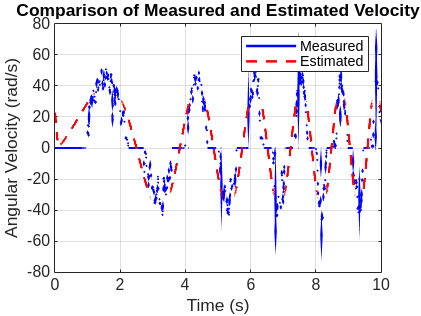

Test 1: RMSE = 16.0465, MAE = 12.5685, R^2 = 0.5324, Corr = 0.8904


Poles of the system:
 -864.3351
  -56.0116



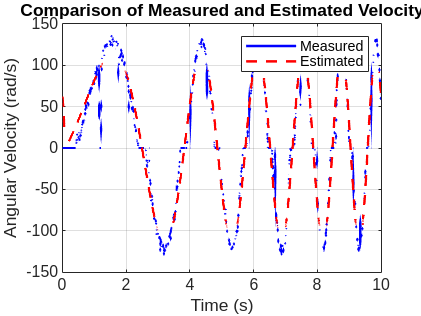

Test 2: RMSE = 71.0887, MAE = 57.9669, R^2 = 0.2026, Corr = 0.9762


Poles of the system:
 -864.3351
  -56.0116



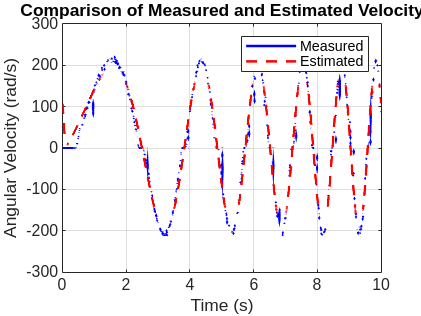

Test 3: RMSE = 129.2972, MAE = 108.8802, R^2 = 0.1127, Corr = 0.9894


Poles of the system:
 -864.3351
  -56.0116



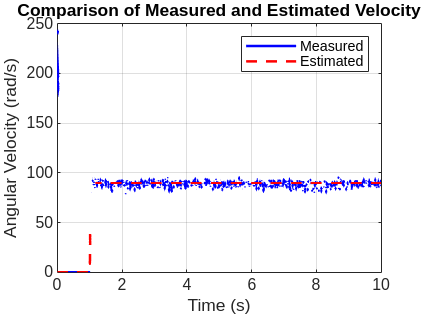

Test 4: RMSE = 18.3663, MAE = 3.8873, R^2 = 0.5751, Corr = 0.7781


Poles of the system:
 -864.3351
  -56.0116



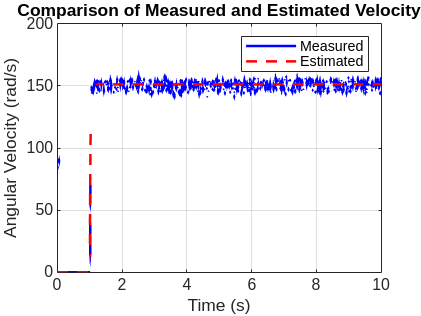

Test 5: RMSE = 19.2180, MAE = 16.9179, R^2 = 0.8104, Corr = 0.9806


Poles of the system:
 -864.3351
  -56.0116



Test 6: RMSE = 26.3422, MAE = 24.2535, R^2 = 0.6438, Corr = 0.9806


Poles of the system:
 -864.3351
  -56.0116



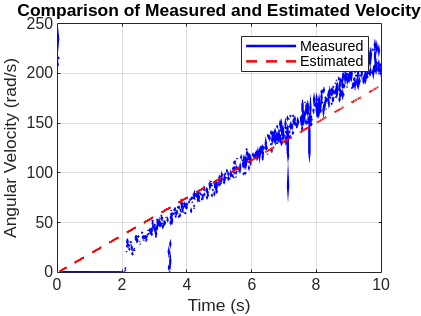

Test 7: RMSE = 26.1616, MAE = 17.8944, R^2 = 0.8593, Corr = 0.9580


Poles of the system:
 -864.3351
  -56.0116



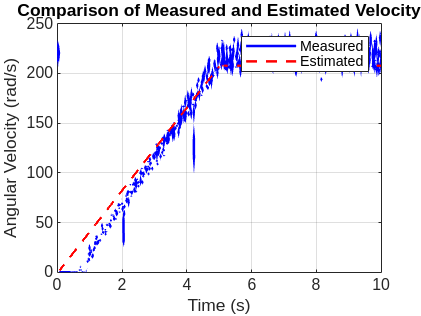

Test 8: RMSE = 35.5335, MAE = 28.7233, R^2 = 0.7915, Corr = 0.9673


Poles of the system:
 -864.3351
  -56.0116



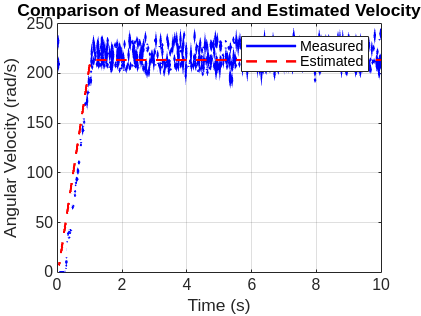

Test 9: RMSE = 41.6405, MAE = 37.6698, R^2 = 0.1481, Corr = 0.8892


Poles of the system:
 -864.3351
  -56.0116



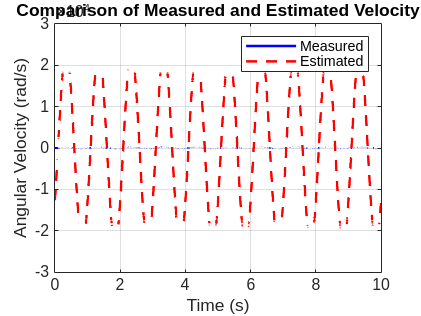

Test 10: RMSE = 68.1578, MAE = 61.9770, R^2 = 0.7652, Corr = 0.9779


Poles of the system:
 -864.3351
  -56.0116



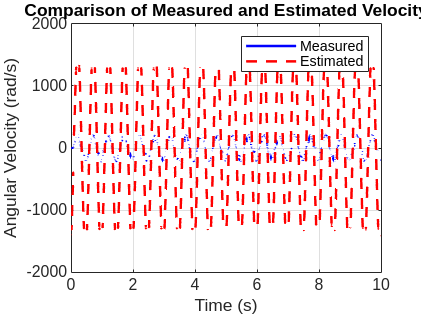

Test 11: RMSE = 110.0889, MAE = 100.0718, R^2 = 0.3773, Corr = 0.9733


Poles of the system:
 -864.3351
  -56.0116



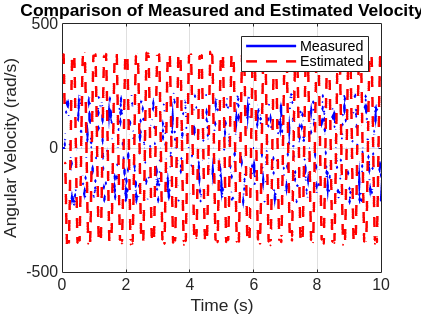

Test 12: RMSE = 153.7748, MAE = 137.8814, R^2 = -0.3361, Corr = -0.9509


Poles of the system:
 -864.3351
  -56.0116



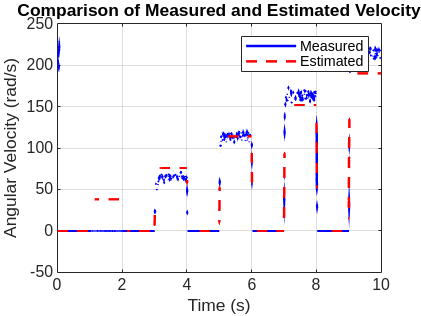

Test 13: RMSE = 26.5206, MAE = 13.1189, R^2 = 0.8821, Corr = 0.9508


Poles of the system:
 -864.3351
  -56.0116



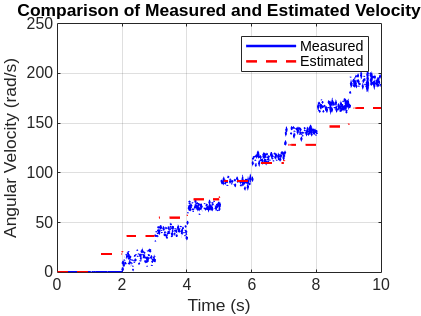

Test 14: RMSE = 17.7019, MAE = 14.3012, R^2 = 0.9284, Corr = 0.9904


Poles of the system:
 -864.3351
  -56.0116



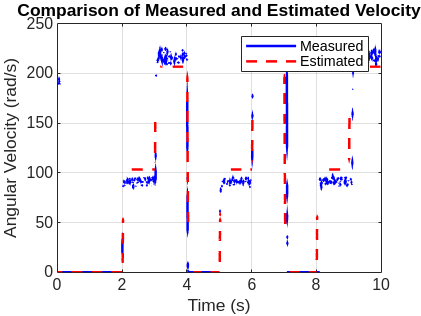

Test 15: RMSE = 35.0689, MAE = 17.6532, R^2 = 0.8447, Corr = 0.9485


Rm = 2.51186;   % Motor Resistance
Lm = 0.0027645; % Motor Inductance   
params = [SSE_Ke, SSE_Jm, SSE_Bm,SSE_Eff];
numTests = length(inputSignals); 

rmse_all = zeros(numTests,1);
mae_all  = zeros(numTests,1);
r2_all   = zeros(numTests,1);
corr_all = zeros(numTests,1);


for k = 1:numTests
    V = inputSignals{k};      
    omega_measured = measuredOmega{k};  
    t = double(SineWave{3}{6}.Values.Time);
    
    omega_est = motor_model(params, Rm, Lm, t, V);
    
    % Compute error between measured and estimated velocities
    error = omega_measured - omega_est;

    [lag, shift] = max(xcorr(omega_measured, omega_est));
    omega_est = circshift(omega_est, shift);
    scale_factor = mean(omega_measured) / mean(omega_est);
    omega_est = omega_est*scale_factor;
    figure;
    plot(t, omega_measured, 'b', 'LineWidth', 1.5);
    hold on;
    plot(t, omega_est, 'r--', 'LineWidth', 1.5);
    legend('Measured', 'Estimated');
    xlabel('Time (s)');
    ylabel('Angular Velocity (rad/s)');
    title('Comparison of Measured and Estimated Velocity');
    grid on;
    
    % Calculate metrics for test k:
    rmse_all(k) = sqrt(mean(error.^2));
    mae_all(k)  = mean(abs(error));
    SStot       = sum((omega_measured - mean(omega_measured)).^2);
    SSres       = sum(error.^2);
    r2_all(k)   = 1 - (SSres / SStot);
    corr_all(k) = corr(omega_measured, omega_est);
    
    % Display the metrics for each test
    fprintf('Test %d: RMSE = %.4f, MAE = %.4f, R^2 = %.4f, Corr = %.4f\n', ...
             k, rmse_all(k), mae_all(k), r2_all(k), corr_all(k));
end


% Optionally, summarize the results in a table:
resultsTable3 = table(rmse_all, mae_all, r2_all, corr_all, ...
    'VariableNames', {'RMSE', 'MAE', 'R_squared', 'Correlation'});
disp(resultsTable3);

     RMSE      MAE      R_squared    Correlation
    ______    ______    _________    ___________

    16.047    12.568     0.53239        0.8904  
    71.089    57.967     0.20263       0.97617  
     129.3    108.88     0.11272       0.98944  
    18.366    3.8873     0.57511       0.77814  
    19.218    16.918     0.81042       0.98056  
    26.342    24.254     0.64382       0.98056  
    26.162    17.894     0.85928       0.95804  
    35.534    28.723     0.79153       0.96725  
     41.64     37.67     0.14809       0.88917  
    68.158    61.977     0.76522       0.97786  
    110.09    100.07     0.37727       0.97329  
    153.77    137.88    -0.33609      -0.95086  
    26.521    13.119      0.8821        0.9508  
    17.702    14.301     0.92843       0.99036  
    35.069    17.653     0.84465       0.94846  



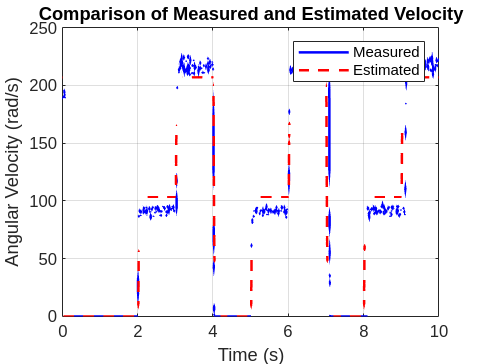

[lag, shift] = max(xcorr(omega_measured, omega_est));
omega_est = circshift(omega_est, shift);
scale_factor = mean(omega_measured) / mean(omega_est);
omega_est = omega_est * scale_factor;
figure;
plot(t, omega_measured, 'b', 'LineWidth', 1.5);
hold on;
plot(t, omega_est, 'r--', 'LineWidth', 1.5);
legend('Measured', 'Estimated');
xlabel('Time (s)');
ylabel('Angular Velocity (rad/s)');
title('Comparison of Measured and Estimated Velocity');
grid on;